# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       computeCostMulti.m      ex1data1.txt            gradientDescent.m       normalEqn.m             token.mat               
..                      ex1.mlx                 ex1data2.txt            gradientDescentMulti.m  plotData.m              warmUpExercise.m        
computeCost.m           ex1_companion.mlx       featureNormalize.m      lib                     submit.m                



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

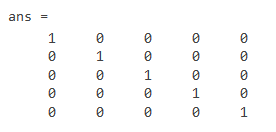

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

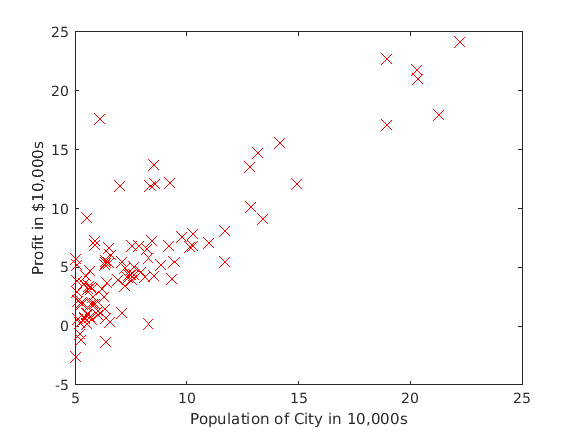

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

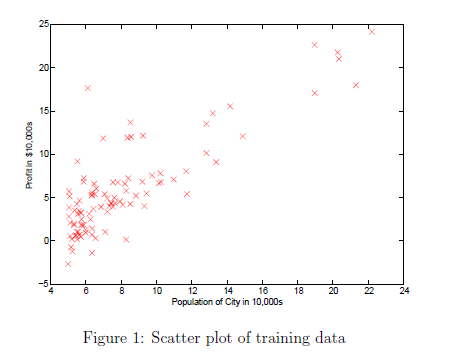

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

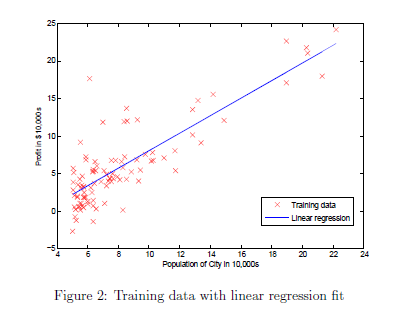    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

h =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


h =     4.0500
    3.6696
    5.6235
    4.6335
    3.8865
    5.5348
    4.9426
    5.6624
    4.2958
    3.3605


h =     4.7677
    4.3193
    6.6223
    5.4554
    4.5750
    6.5178
    5.8198
    6.6681
    5.0573
    3.9550


h =     4.8930
    4.4322
    6.7990
    5.5998
    4.6950
    6.6916
    5.9743
    6.8461
    5.1907
    4.0578


h =     4.9131
    4.4496
    6.8296
    5.6237
    4.7139
    6.7216
    6.0003
    6.8769
    5.2123
    4.0732


h =     4.9144
    4.4501
    6.8342
    5.6262
    4.7148
    6.7260
    6.0034
    6.8816
    5.2141
    4.0730


h =     4.9123
    4.4476
    6.8341
    5.6250
    4.7126
    6.7259
    6.0025
    6.8816
    5.2124
    4.0701


h =     4.9097
    4.4446
    6.8333
    5.6230
    4.7098
    6.7249
    6.0009
    6.8808
    5.2101
    4.0667


h =     4.9070
    4.4415
    6.8323
    5.6209
    4.7069
    6.7238
    5.9992
    6.8799
    5.2077
    4.0633


h =     4.9043
    4.4383
    6.8313
    5.6188
    4.7040
    6.7227
    5.9974
    6.8789
    5.2052
    4.0598


h =     4.9016
    4.4352
    6.8303
    5.6167
    4.7011
    6.7216
    5.9957
    6.8779
    5.2027
    4.0563


h =     4.8988
    4.4321
    6.8293
    5.6147
    4.6982
    6.7205
    5.9939
    6.8769
    5.2003
    4.0529


h =     4.8961
    4.4289
    6.8282
    5.6126
    4.6953
    6.7194
    5.9922
    6.8760
    5.1978
    4.0494


h =     4.8934
    4.4258
    6.8272
    5.6105
    4.6925
    6.7183
    5.9904
    6.8750
    5.1954
    4.0460


h =     4.8907
    4.4227
    6.8262
    5.6084
    4.6896
    6.7172
    5.9887
    6.8740
    5.1930
    4.0425


h =     4.8880
    4.4196
    6.8252
    5.6064
    4.6867
    6.7161
    5.9870
    6.8731
    5.1905
    4.0391


h =     4.8853
    4.4165
    6.8242
    5.6043
    4.6838
    6.7150
    5.9852
    6.8721
    5.1881
    4.0356


h =     4.8826
    4.4134
    6.8232
    5.6022
    4.6810
    6.7139
    5.9835
    6.8711
    5.1857
    4.0322


h =     4.8800
    4.4103
    6.8222
    5.6002
    4.6781
    6.7128
    5.9818
    6.8702
    5.1832
    4.0288


h =     4.8773
    4.4072
    6.8212
    5.5981
    4.6753
    6.7117
    5.9800
    6.8692
    5.1808
    4.0254


h =     4.8746
    4.4041
    6.8202
    5.5961
    4.6724
    6.7106
    5.9783
    6.8683
    5.1784
    4.0220


h =     4.8719
    4.4011
    6.8192
    5.5940
    4.6696
    6.7095
    5.9766
    6.8673
    5.1760
    4.0186


h =     4.8693
    4.3980
    6.8182
    5.5920
    4.6667
    6.7084
    5.9749
    6.8664
    5.1736
    4.0152


h =     4.8666
    4.3949
    6.8172
    5.5899
    4.6639
    6.7073
    5.9732
    6.8654
    5.1712
    4.0118


h =     4.8640
    4.3919
    6.8162
    5.5879
    4.6611
    6.7062
    5.9714
    6.8645
    5.1688
    4.0084


h =     4.8613
    4.3888
    6.8152
    5.5858
    4.6582
    6.7051
    5.9697
    6.8635
    5.1664
    4.0050


h =     4.8587
    4.3858
    6.8142
    5.5838
    4.6554
    6.7041
    5.9680
    6.8626
    5.1640
    4.0016


h =     4.8560
    4.3827
    6.8133
    5.5818
    4.6526
    6.7030
    5.9663
    6.8616
    5.1617
    3.9983


h =     4.8534
    4.3797
    6.8123
    5.5798
    4.6498
    6.7019
    5.9646
    6.8607
    5.1593
    3.9949


h =     4.8508
    4.3767
    6.8113
    5.5777
    4.6470
    6.7008
    5.9629
    6.8597
    5.1569
    3.9916


h =     4.8481
    4.3736
    6.8103
    5.5757
    4.6442
    6.6998
    5.9612
    6.8588
    5.1545
    3.9882


h =     4.8455
    4.3706
    6.8093
    5.5737
    4.6414
    6.6987
    5.9596
    6.8578
    5.1522
    3.9849


h =     4.8429
    4.3676
    6.8084
    5.5717
    4.6386
    6.6976
    5.9579
    6.8569
    5.1498
    3.9815


h =     4.8403
    4.3646
    6.8074
    5.5697
    4.6358
    6.6966
    5.9562
    6.8560
    5.1474
    3.9782


h =     4.8377
    4.3616
    6.8064
    5.5677
    4.6331
    6.6955
    5.9545
    6.8550
    5.1451
    3.9749


h =     4.8351
    4.3586
    6.8054
    5.5657
    4.6303
    6.6944
    5.9528
    6.8541
    5.1427
    3.9716


h =     4.8325
    4.3556
    6.8045
    5.5637
    4.6275
    6.6934
    5.9511
    6.8532
    5.1404
    3.9683


h =     4.8299
    4.3526
    6.8035
    5.5617
    4.6248
    6.6923
    5.9495
    6.8523
    5.1381
    3.9650


h =     4.8273
    4.3496
    6.8025
    5.5597
    4.6220
    6.6912
    5.9478
    6.8513
    5.1357
    3.9617


h =     4.8247
    4.3467
    6.8016
    5.5577
    4.6193
    6.6902
    5.9461
    6.8504
    5.1334
    3.9584


h =     4.8221
    4.3437
    6.8006
    5.5558
    4.6165
    6.6891
    5.9445
    6.8495
    5.1311
    3.9551


h =     4.8195
    4.3407
    6.7996
    5.5538
    4.6138
    6.6881
    5.9428
    6.8486
    5.1287
    3.9518


h =     4.8170
    4.3378
    6.7987
    5.5518
    4.6110
    6.6870
    5.9412
    6.8476
    5.1264
    3.9485


h =     4.8144
    4.3348
    6.7977
    5.5498
    4.6083
    6.6860
    5.9395
    6.8467
    5.1241
    3.9452


h =     4.8118
    4.3319
    6.7968
    5.5479
    4.6056
    6.6849
    5.9379
    6.8458
    5.1218
    3.9420


h =     4.8093
    4.3289
    6.7958
    5.5459
    4.6028
    6.6839
    5.9362
    6.8449
    5.1195
    3.9387


h =     4.8067
    4.3260
    6.7949
    5.5440
    4.6001
    6.6828
    5.9346
    6.8440
    5.1172
    3.9355


h =     4.8042
    4.3231
    6.7939
    5.5420
    4.5974
    6.6818
    5.9329
    6.8431
    5.1149
    3.9322


h =     4.8017
    4.3201
    6.7930
    5.5401
    4.5947
    6.6808
    5.9313
    6.8422
    5.1126
    3.9290


h =     4.7991
    4.3172
    6.7920
    5.5381
    4.5920
    6.6797
    5.9296
    6.8412
    5.1103
    3.9257


h = 97×1
    4.7966
    4.3143
    6.7911
    5.5362
    4.5893
    6.6787
    5.9280
    6.8403
    5.1080
    3.9225


h = 97×1
    4.7941
    4.3114
    6.7901
    5.5342
    4.5866
    6.6777
    5.9264
    6.8394
    5.1057
    3.9193


h = 97×1
    4.7915
    4.3085
    6.7892
    5.5323
    4.5839
    6.6766
    5.9248
    6.8385
    5.1035
    3.9161


h = 97×1
    4.7890
    4.3056
    6.7882
    5.5303
    4.5812
    6.6756
    5.9231
    6.8376
    5.1012
    3.9129


h = 97×1
    4.7865
    4.3027
    6.7873
    5.5284
    4.5786
    6.6746
    5.9215
    6.8367
    5.0989
    3.9097


h = 97×1
    4.7840
    4.2998
    6.7864
    5.5265
    4.5759
    6.6735
    5.9199
    6.8358
    5.0967
    3.9065


h = 97×1
    4.7815
    4.2969
    6.7854
    5.5246
    4.5732
    6.6725
    5.9183
    6.8349
    5.0944
    3.9033


h = 97×1
    4.7790
    4.2940
    6.7845
    5.5226
    4.5706
    6.6715
    5.9167
    6.8340
    5.0921
    3.9001


h = 97×1
    4.7765
    4.2911
    6.7836
    5.5207
    4.5679
    6.6705
    5.9151
    6.8331
    5.0899
    3.8969


h = 97×1
    4.7740
    4.2883
    6.7826
    5.5188
    4.5652
    6.6695
    5.9135
    6.8322
    5.0876
    3.8937


h = 97×1
    4.7715
    4.2854
    6.7817
    5.5169
    4.5626
    6.6684
    5.9118
    6.8314
    5.0854
    3.8905


h = 97×1
    4.7690
    4.2826
    6.7808
    5.5150
    4.5599
    6.6674
    5.9102
    6.8305
    5.0832
    3.8874


h = 97×1
    4.7665
    4.2797
    6.7798
    5.5131
    4.5573
    6.6664
    5.9087
    6.8296
    5.0809
    3.8842


h = 97×1
    4.7641
    4.2768
    6.7789
    5.5112
    4.5547
    6.6654
    5.9071
    6.8287
    5.0787
    3.8811


h = 97×1
    4.7616
    4.2740
    6.7780
    5.5093
    4.5520
    6.6644
    5.9055
    6.8278
    5.0765
    3.8779


h = 97×1
    4.7591
    4.2712
    6.7771
    5.5074
    4.5494
    6.6634
    5.9039
    6.8269
    5.0742
    3.8748


h = 97×1
    4.7567
    4.2683
    6.7762
    5.5055
    4.5468
    6.6624
    5.9023
    6.8260
    5.0720
    3.8716


h = 97×1
    4.7542
    4.2655
    6.7752
    5.5036
    4.5442
    6.6614
    5.9007
    6.8252
    5.0698
    3.8685


h = 97×1
    4.7518
    4.2627
    6.7743
    5.5017
    4.5416
    6.6604
    5.8991
    6.8243
    5.0676
    3.8654


h = 97×1
    4.7493
    4.2599
    6.7734
    5.4999
    4.5390
    6.6594
    5.8975
    6.8234
    5.0654
    3.8623


h = 97×1
    4.7469
    4.2570
    6.7725
    5.4980
    4.5364
    6.6584
    5.8960
    6.8225
    5.0632
    3.8592


h = 97×1
    4.7444
    4.2542
    6.7716
    5.4961
    4.5338
    6.6574
    5.8944
    6.8217
    5.0610
    3.8560


h = 97×1
    4.7420
    4.2514
    6.7707
    5.4943
    4.5312
    6.6564
    5.8928
    6.8208
    5.0588
    3.8529


h = 97×1
    4.7396
    4.2486
    6.7698
    5.4924
    4.5286
    6.6554
    5.8913
    6.8199
    5.0566
    3.8498


h = 97×1
    4.7371
    4.2458
    6.7689
    5.4905
    4.5260
    6.6544
    5.8897
    6.8191
    5.0544
    3.8467


h = 97×1
    4.7347
    4.2431
    6.7680
    5.4887
    4.5234
    6.6534
    5.8881
    6.8182
    5.0522
    3.8437


h = 97×1
    4.7323
    4.2403
    6.7671
    5.4868
    4.5208
    6.6524
    5.8866
    6.8173
    5.0500
    3.8406


h = 97×1
    4.7299
    4.2375
    6.7662
    5.4850
    4.5183
    6.6514
    5.8850
    6.8165
    5.0479
    3.8375


h = 97×1
    4.7275
    4.2347
    6.7653
    5.4831
    4.5157
    6.6504
    5.8835
    6.8156
    5.0457
    3.8344


h = 97×1
    4.7251
    4.2319
    6.7644
    5.4813
    4.5131
    6.6495
    5.8819
    6.8147
    5.0435
    3.8314


h = 97×1
    4.7227
    4.2292
    6.7635
    5.4794
    4.5106
    6.6485
    5.8804
    6.8139
    5.0414
    3.8283


h = 97×1
    4.7203
    4.2264
    6.7626
    5.4776
    4.5080
    6.6475
    5.8788
    6.8130
    5.0392
    3.8253


h = 97×1
    4.7179
    4.2237
    6.7617
    5.4757
    4.5055
    6.6465
    5.8773
    6.8122
    5.0370
    3.8222


h = 97×1
    4.7155
    4.2209
    6.7608
    5.4739
    4.5029
    6.6455
    5.8758
    6.8113
    5.0349
    3.8192


h = 97×1
    4.7131
    4.2182
    6.7599
    5.4721
    4.5004
    6.6446
    5.8742
    6.8105
    5.0327
    3.8161


h = 97×1
    4.7107
    4.2154
    6.7590
    5.4703
    4.4979
    6.6436
    5.8727
    6.8096
    5.0306
    3.8131


h = 97×1
    4.7084
    4.2127
    6.7581
    5.4684
    4.4953
    6.6426
    5.8712
    6.8088
    5.0284
    3.8101


h = 97×1
    4.7060
    4.2100
    6.7572
    5.4666
    4.4928
    6.6417
    5.8696
    6.8079
    5.0263
    3.8071


h = 97×1
    4.7036
    4.2073
    6.7564
    5.4648
    4.4903
    6.6407
    5.8681
    6.8071
    5.0242
    3.8040


h = 97×1
    4.7013
    4.2045
    6.7555
    5.4630
    4.4878
    6.6397
    5.8666
    6.8062
    5.0220
    3.8010


h = 97×1
    4.6989
    4.2018
    6.7546
    5.4612
    4.4853
    6.6388
    5.8651
    6.8054
    5.0199
    3.7980


h = 97×1
    4.6966
    4.1991
    6.7537
    5.4594
    4.4828
    6.6378
    5.8635
    6.8045
    5.0178
    3.7950


h = 97×1
    4.6942
    4.1964
    6.7528
    5.4576
    4.4803
    6.6368
    5.8620
    6.8037
    5.0157
    3.7920


h = 97×1
    4.6919
    4.1937
    6.7520
    5.4558
    4.4778
    6.6359
    5.8605
    6.8029
    5.0136
    3.7890


h = 97×1
    4.6895
    4.1910
    6.7511
    5.4540
    4.4753
    6.6349
    5.8590
    6.8020
    5.0114
    3.7861


h = 97×1
    4.6872
    4.1883
    6.7502
    5.4522
    4.4728
    6.6340
    5.8575
    6.8012
    5.0093
    3.7831


h = 97×1
    4.6849
    4.1856
    6.7493
    5.4504
    4.4703
    6.6330
    5.8560
    6.8003
    5.0072
    3.7801


h = 97×1
    4.6825
    4.1830
    6.7485
    5.4486
    4.4678
    6.6321
    5.8545
    6.7995
    5.0051
    3.7772


h = 97×1
    4.6802
    4.1803
    6.7476
    5.4468
    4.4654
    6.6311
    5.8530
    6.7987
    5.0030
    3.7742


h = 97×1
    4.6779
    4.1776
    6.7467
    5.4450
    4.4629
    6.6302
    5.8515
    6.7978
    5.0009
    3.7712


h = 97×1
    4.6756
    4.1750
    6.7459
    5.4433
    4.4604
    6.6292
    5.8500
    6.7970
    4.9989
    3.7683


h = 97×1
    4.6733
    4.1723
    6.7450
    5.4415
    4.4580
    6.6283
    5.8485
    6.7962
    4.9968
    3.7653


h = 97×1
    4.6710
    4.1696
    6.7442
    5.4397
    4.4555
    6.6273
    5.8470
    6.7954
    4.9947
    3.7624


h = 97×1
    4.6687
    4.1670
    6.7433
    5.4380
    4.4530
    6.6264
    5.8456
    6.7945
    4.9926
    3.7595


h = 97×1
    4.6664
    4.1643
    6.7424
    5.4362
    4.4506
    6.6255
    5.8441
    6.7937
    4.9905
    3.7565


h = 97×1
    4.6641
    4.1617
    6.7416
    5.4344
    4.4482
    6.6245
    5.8426
    6.7929
    4.9885
    3.7536


h = 97×1
    4.6618
    4.1591
    6.7407
    5.4327
    4.4457
    6.6236
    5.8411
    6.7921
    4.9864
    3.7507


h = 97×1
    4.6595
    4.1564
    6.7399
    5.4309
    4.4433
    6.6227
    5.8397
    6.7913
    4.9843
    3.7478


h = 97×1
    4.6572
    4.1538
    6.7390
    5.4292
    4.4409
    6.6217
    5.8382
    6.7904
    4.9823
    3.7449


h = 97×1
    4.6549
    4.1512
    6.7382
    5.4274
    4.4384
    6.6208
    5.8367
    6.7896
    4.9802
    3.7420


h = 97×1
    4.6527
    4.1486
    6.7373
    5.4257
    4.4360
    6.6199
    5.8352
    6.7888
    4.9782
    3.7391


h = 97×1
    4.6504
    4.1459
    6.7365
    5.4239
    4.4336
    6.6189
    5.8338
    6.7880
    4.9761
    3.7362


h = 97×1
    4.6481
    4.1433
    6.7356
    5.4222
    4.4312
    6.6180
    5.8323
    6.7872
    4.9741
    3.7333


h = 97×1
    4.6459
    4.1407
    6.7348
    5.4205
    4.4288
    6.6171
    5.8309
    6.7864
    4.9721
    3.7304


h = 97×1
    4.6436
    4.1381
    6.7339
    5.4187
    4.4264
    6.6162
    5.8294
    6.7856
    4.9700
    3.7275


h = 97×1
    4.6413
    4.1355
    6.7331
    5.4170
    4.4240
    6.6152
    5.8280
    6.7848
    4.9680
    3.7247


h = 97×1
    4.6391
    4.1330
    6.7323
    5.4153
    4.4216
    6.6143
    5.8265
    6.7840
    4.9660
    3.7218


h = 97×1
    4.6369
    4.1304
    6.7314
    5.4135
    4.4192
    6.6134
    5.8251
    6.7832
    4.9639
    3.7189


h = 97×1
    4.6346
    4.1278
    6.7306
    5.4118
    4.4168
    6.6125
    5.8236
    6.7824
    4.9619
    3.7161


h = 97×1
    4.6324
    4.1252
    6.7297
    5.4101
    4.4144
    6.6116
    5.8222
    6.7816
    4.9599
    3.7132


h = 97×1
    4.6301
    4.1226
    6.7289
    5.4084
    4.4120
    6.6107
    5.8207
    6.7808
    4.9579
    3.7104


h = 97×1
    4.6279
    4.1201
    6.7281
    5.4067
    4.4097
    6.6098
    5.8193
    6.7800
    4.9559
    3.7075


h = 97×1
    4.6257
    4.1175
    6.7272
    5.4050
    4.4073
    6.6088
    5.8179
    6.7792
    4.9539
    3.7047


h = 97×1
    4.6235
    4.1150
    6.7264
    5.4033
    4.4049
    6.6079
    5.8164
    6.7784
    4.9519
    3.7019


h = 97×1
    4.6213
    4.1124
    6.7256
    5.4016
    4.4026
    6.6070
    5.8150
    6.7776
    4.9499
    3.6991


h = 97×1
    4.6190
    4.1099
    6.7248
    5.3999
    4.4002
    6.6061
    5.8136
    6.7768
    4.9479
    3.6962


h = 97×1
    4.6168
    4.1073
    6.7239
    5.3982
    4.3979
    6.6052
    5.8122
    6.7760
    4.9459
    3.6934


h = 97×1
    4.6146
    4.1048
    6.7231
    5.3965
    4.3955
    6.6043
    5.8107
    6.7752
    4.9439
    3.6906


h = 97×1
    4.6124
    4.1022
    6.7223
    5.3948
    4.3932
    6.6034
    5.8093
    6.7744
    4.9419
    3.6878


h = 97×1
    4.6102
    4.0997
    6.7215
    5.3931
    4.3908
    6.6025
    5.8079
    6.7736
    4.9399
    3.6850


h = 97×1
    4.6080
    4.0972
    6.7207
    5.3914
    4.3885
    6.6016
    5.8065
    6.7728
    4.9379
    3.6822


h = 97×1
    4.6058
    4.0947
    6.7198
    5.3897
    4.3862
    6.6007
    5.8051
    6.7721
    4.9360
    3.6794


h = 97×1
    4.6037
    4.0921
    6.7190
    5.3881
    4.3838
    6.5998
    5.8037
    6.7713
    4.9340
    3.6766


h = 97×1
    4.6015
    4.0896
    6.7182
    5.3864
    4.3815
    6.5989
    5.8023
    6.7705
    4.9320
    3.6739


h = 97×1
    4.5993
    4.0871
    6.7174
    5.3847
    4.3792
    6.5981
    5.8009
    6.7697
    4.9301
    3.6711


h = 97×1
    4.5971
    4.0846
    6.7166
    5.3830
    4.3769
    6.5972
    5.7995
    6.7689
    4.9281
    3.6683


h = 97×1
    4.5950
    4.0821
    6.7158
    5.3814
    4.3746
    6.5963
    5.7981
    6.7682
    4.9261
    3.6655


h = 97×1
    4.5928
    4.0796
    6.7150
    5.3797
    4.3723
    6.5954
    5.7967
    6.7674
    4.9242
    3.6628


h = 97×1
    4.5906
    4.0771
    6.7142
    5.3781
    4.3700
    6.5945
    5.7953
    6.7666
    4.9222
    3.6600


h = 97×1
    4.5885
    4.0747
    6.7134
    5.3764
    4.3677
    6.5936
    5.7939
    6.7658
    4.9203
    3.6573


h = 97×1
    4.5863
    4.0722
    6.7125
    5.3748
    4.3654
    6.5928
    5.7925
    6.7651
    4.9183
    3.6545


h = 97×1
    4.5842
    4.0697
    6.7117
    5.3731
    4.3631
    6.5919
    5.7911
    6.7643
    4.9164
    3.6518


h = 97×1
    4.5820
    4.0672
    6.7109
    5.3715
    4.3608
    6.5910
    5.7897
    6.7635
    4.9145
    3.6491


h = 97×1
    4.5799
    4.0648
    6.7101
    5.3698
    4.3585
    6.5901
    5.7883
    6.7628
    4.9125
    3.6463


h = 97×1
    4.5778
    4.0623
    6.7093
    5.3682
    4.3562
    6.5892
    5.7870
    6.7620
    4.9106
    3.6436


h = 97×1
    4.5756
    4.0599
    6.7085
    5.3665
    4.3540
    6.5884
    5.7856
    6.7612
    4.9087
    3.6409


h = 97×1
    4.5735
    4.0574
    6.7078
    5.3649
    4.3517
    6.5875
    5.7842
    6.7605
    4.9068
    3.6382


h = 97×1
    4.5714
    4.0549
    6.7070
    5.3633
    4.3494
    6.5866
    5.7828
    6.7597
    4.9048
    3.6355


h = 97×1
    4.5692
    4.0525
    6.7062
    5.3616
    4.3472
    6.5858
    5.7815
    6.7590
    4.9029
    3.6328


h = 97×1
    4.5671
    4.0501
    6.7054
    5.3600
    4.3449
    6.5849
    5.7801
    6.7582
    4.9010
    3.6300


h = 97×1
    4.5650
    4.0476
    6.7046
    5.3584
    4.3426
    6.5840
    5.7787
    6.7574
    4.8991
    3.6274


h = 97×1
    4.5629
    4.0452
    6.7038
    5.3568
    4.3404
    6.5832
    5.7774
    6.7567
    4.8972
    3.6247


h = 97×1
    4.5608
    4.0428
    6.7030
    5.3551
    4.3382
    6.5823
    5.7760
    6.7559
    4.8953
    3.6220


h = 97×1
    4.5587
    4.0403
    6.7022
    5.3535
    4.3359
    6.5815
    5.7747
    6.7552
    4.8934
    3.6193


h = 97×1
    4.5566
    4.0379
    6.7014
    5.3519
    4.3337
    6.5806
    5.7733
    6.7544
    4.8915
    3.6166


h = 97×1
    4.5545
    4.0355
    6.7007
    5.3503
    4.3314
    6.5797
    5.7720
    6.7537
    4.8896
    3.6139


h = 97×1
    4.5524
    4.0331
    6.6999
    5.3487
    4.3292
    6.5789
    5.7706
    6.7529
    4.8877
    3.6113


h = 97×1
    4.5503
    4.0307
    6.6991
    5.3471
    4.3270
    6.5780
    5.7693
    6.7522
    4.8858
    3.6086


h = 97×1
    4.5482
    4.0283
    6.6983
    5.3455
    4.3248
    6.5772
    5.7679
    6.7514
    4.8840
    3.6060


h = 97×1
    4.5461
    4.0259
    6.6975
    5.3439
    4.3226
    6.5763
    5.7666
    6.7507
    4.8821
    3.6033


h = 97×1
    4.5441
    4.0235
    6.6968
    5.3423
    4.3203
    6.5755
    5.7653
    6.7499
    4.8802
    3.6007


h = 97×1
    4.5420
    4.0211
    6.6960
    5.3407
    4.3181
    6.5746
    5.7639
    6.7492
    4.8783
    3.5980


h = 97×1
    4.5399
    4.0187
    6.6952
    5.3391
    4.3159
    6.5738
    5.7626
    6.7485
    4.8765
    3.5954


h = 97×1
    4.5379
    4.0164
    6.6944
    5.3375
    4.3137
    6.5729
    5.7612
    6.7477
    4.8746
    3.5927


h = 97×1
    4.5358
    4.0140
    6.6937
    5.3360
    4.3115
    6.5721
    5.7599
    6.7470
    4.8728
    3.5901


h = 97×1
    4.5337
    4.0116
    6.6929
    5.3344
    4.3093
    6.5713
    5.7586
    6.7462
    4.8709
    3.5875


h = 97×1
    4.5317
    4.0093
    6.6921
    5.3328
    4.3072
    6.5704
    5.7573
    6.7455
    4.8690
    3.5849


h = 97×1
    4.5296
    4.0069
    6.6914
    5.3312
    4.3050
    6.5696
    5.7559
    6.7448
    4.8672
    3.5823


h = 97×1
    4.5276
    4.0045
    6.6906
    5.3297
    4.3028
    6.5687
    5.7546
    6.7440
    4.8653
    3.5797


h = 97×1
    4.5255
    4.0022
    6.6898
    5.3281
    4.3006
    6.5679
    5.7533
    6.7433
    4.8635
    3.5770


h = 97×1
    4.5235
    3.9998
    6.6891
    5.3265
    4.2984
    6.5671
    5.7520
    6.7426
    4.8617
    3.5744


h = 97×1
    4.5215
    3.9975
    6.6883
    5.3250
    4.2963
    6.5662
    5.7507
    6.7419
    4.8598
    3.5719


h = 97×1
    4.5194
    3.9951
    6.6876
    5.3234
    4.2941
    6.5654
    5.7494
    6.7411
    4.8580
    3.5693


h = 97×1
    4.5174
    3.9928
    6.6868
    5.3218
    4.2919
    6.5646
    5.7481
    6.7404
    4.8562
    3.5667


h = 97×1
    4.5154
    3.9905
    6.6860
    5.3203
    4.2898
    6.5637
    5.7468
    6.7397
    4.8543
    3.5641


h = 97×1
    4.5133
    3.9881
    6.6853
    5.3187
    4.2876
    6.5629
    5.7455
    6.7389
    4.8525
    3.5615


h = 97×1
    4.5113
    3.9858
    6.6845
    5.3172
    4.2855
    6.5621
    5.7442
    6.7382
    4.8507
    3.5589


h = 97×1
    4.5093
    3.9835
    6.6838
    5.3156
    4.2833
    6.5613
    5.7429
    6.7375
    4.8489
    3.5564


h = 97×1
    4.5073
    3.9812
    6.6830
    5.3141
    4.2812
    6.5605
    5.7416
    6.7368
    4.8471
    3.5538


h = 97×1
    4.5053
    3.9789
    6.6823
    5.3125
    4.2791
    6.5596
    5.7403
    6.7361
    4.8452
    3.5513


h = 97×1
    4.5033
    3.9766
    6.6815
    5.3110
    4.2769
    6.5588
    5.7390
    6.7353
    4.8434
    3.5487


h = 97×1
    4.5013
    3.9743
    6.6808
    5.3095
    4.2748
    6.5580
    5.7377
    6.7346
    4.8416
    3.5462


h = 97×1
    4.4993
    3.9720
    6.6800
    5.3079
    4.2727
    6.5572
    5.7364
    6.7339
    4.8398
    3.5436


h = 97×1
    4.4973
    3.9697
    6.6793
    5.3064
    4.2705
    6.5564
    5.7351
    6.7332
    4.8380
    3.5411


h = 97×1
    4.4953
    3.9674
    6.6786
    5.3049
    4.2684
    6.5556
    5.7338
    6.7325
    4.8362
    3.5385


h = 97×1
    4.4933
    3.9651
    6.6778
    5.3034
    4.2663
    6.5547
    5.7326
    6.7318
    4.8344
    3.5360


h = 97×1
    4.4913
    3.9628
    6.6771
    5.3018
    4.2642
    6.5539
    5.7313
    6.7311
    4.8327
    3.5335


h = 97×1
    4.4894
    3.9605
    6.6763
    5.3003
    4.2621
    6.5531
    5.7300
    6.7304
    4.8309
    3.5310


h = 97×1
    4.4874
    3.9583
    6.6756
    5.2988
    4.2600
    6.5523
    5.7287
    6.7297
    4.8291
    3.5284


h = 97×1
    4.4854
    3.9560
    6.6749
    5.2973
    4.2579
    6.5515
    5.7275
    6.7290
    4.8273
    3.5259


h = 97×1
    4.4835
    3.9537
    6.6741
    5.2958
    4.2558
    6.5507
    5.7262
    6.7282
    4.8255
    3.5234


h = 97×1
    4.4815
    3.9515
    6.6734
    5.2943
    4.2537
    6.5499
    5.7249
    6.7275
    4.8238
    3.5209


h = 97×1
    4.4795
    3.9492
    6.6727
    5.2928
    4.2516
    6.5491
    5.7237
    6.7268
    4.8220
    3.5184


h = 97×1
    4.4776
    3.9470
    6.6719
    5.2913
    4.2495
    6.5483
    5.7224
    6.7261
    4.8202
    3.5159


h = 97×1
    4.4756
    3.9447
    6.6712
    5.2898
    4.2474
    6.5475
    5.7211
    6.7254
    4.8185
    3.5134


h = 97×1
    4.4737
    3.9425
    6.6705
    5.2883
    4.2454
    6.5467
    5.7199
    6.7247
    4.8167
    3.5109


h = 97×1
    4.4717
    3.9402
    6.6697
    5.2868
    4.2433
    6.5459
    5.7186
    6.7240
    4.8150
    3.5085


h = 97×1
    4.4698
    3.9380
    6.6690
    5.2853
    4.2412
    6.5451
    5.7174
    6.7234
    4.8132
    3.5060


h = 97×1
    4.4678
    3.9357
    6.6683
    5.2838
    4.2392
    6.5443
    5.7161
    6.7227
    4.8115
    3.5035


h = 97×1
    4.4659
    3.9335
    6.6676
    5.2823
    4.2371
    6.5435
    5.7149
    6.7220
    4.8097
    3.5010


h = 97×1
    4.4640
    3.9313
    6.6669
    5.2808
    4.2350
    6.5427
    5.7136
    6.7213
    4.8080
    3.4986


h = 97×1
    4.4620
    3.9291
    6.6661
    5.2793
    4.2330
    6.5419
    5.7124
    6.7206
    4.8062
    3.4961


h = 97×1
    4.4601
    3.9269
    6.6654
    5.2779
    4.2309
    6.5412
    5.7111
    6.7199
    4.8045
    3.4937


h = 97×1
    4.4582
    3.9246
    6.6647
    5.2764
    4.2289
    6.5404
    5.7099
    6.7192
    4.8028
    3.4912


h = 97×1
    4.4563
    3.9224
    6.6640
    5.2749
    4.2268
    6.5396
    5.7087
    6.7185
    4.8010
    3.4888


h = 97×1
    4.4544
    3.9202
    6.6633
    5.2734
    4.2248
    6.5388
    5.7074
    6.7178
    4.7993
    3.4863


h = 97×1
    4.4524
    3.9180
    6.6626
    5.2720
    4.2228
    6.5380
    5.7062
    6.7171
    4.7976
    3.4839


h = 97×1
    4.4505
    3.9158
    6.6618
    5.2705
    4.2207
    6.5372
    5.7050
    6.7165
    4.7958
    3.4815


h = 97×1
    4.4486
    3.9136
    6.6611
    5.2691
    4.2187
    6.5365
    5.7037
    6.7158
    4.7941
    3.4790


h = 97×1
    4.4467
    3.9114
    6.6604
    5.2676
    4.2167
    6.5357
    5.7025
    6.7151
    4.7924
    3.4766


h = 97×1
    4.4448
    3.9093
    6.6597
    5.2661
    4.2147
    6.5349
    5.7013
    6.7144
    4.7907
    3.4742


h = 97×1
    4.4429
    3.9071
    6.6590
    5.2647
    4.2126
    6.5341
    5.7001
    6.7137
    4.7890
    3.4718


h = 97×1
    4.4410
    3.9049
    6.6583
    5.2632
    4.2106
    6.5334
    5.6989
    6.7131
    4.7873
    3.4694


h = 97×1
    4.4392
    3.9027
    6.6576
    5.2618
    4.2086
    6.5326
    5.6976
    6.7124
    4.7856
    3.4670


h = 97×1
    4.4373
    3.9006
    6.6569
    5.2603
    4.2066
    6.5318
    5.6964
    6.7117
    4.7839
    3.4646


h = 97×1
    4.4354
    3.8984
    6.6562
    5.2589
    4.2046
    6.5311
    5.6952
    6.7110
    4.7822
    3.4622


h = 97×1
    4.4335
    3.8962
    6.6555
    5.2574
    4.2026
    6.5303
    5.6940
    6.7104
    4.7805
    3.4598


h = 97×1
    4.4316
    3.8941
    6.6548
    5.2560
    4.2006
    6.5295
    5.6928
    6.7097
    4.7788
    3.4574


h = 97×1
    4.4298
    3.8919
    6.6541
    5.2546
    4.1986
    6.5288
    5.6916
    6.7090
    4.7771
    3.4550


h = 97×1
    4.4279
    3.8898
    6.6534
    5.2531
    4.1966
    6.5280
    5.6904
    6.7084
    4.7754
    3.4526


h = 97×1
    4.4260
    3.8876
    6.6527
    5.2517
    4.1946
    6.5272
    5.6892
    6.7077
    4.7737
    3.4502


h = 97×1
    4.4242
    3.8855
    6.6520
    5.2503
    4.1927
    6.5265
    5.6880
    6.7070
    4.7721
    3.4479


h = 97×1
    4.4223
    3.8833
    6.6513
    5.2489
    4.1907
    6.5257
    5.6868
    6.7064
    4.7704
    3.4455


h = 97×1
    4.4205
    3.8812
    6.6506
    5.2474
    4.1887
    6.5250
    5.6856
    6.7057
    4.7687
    3.4431


h = 97×1
    4.4186
    3.8791
    6.6499
    5.2460
    4.1867
    6.5242
    5.6844
    6.7050
    4.7670
    3.4408


h = 97×1
    4.4168
    3.8769
    6.6492
    5.2446
    4.1848
    6.5234
    5.6832
    6.7044
    4.7654
    3.4384


h = 97×1
    4.4149
    3.8748
    6.6485
    5.2432
    4.1828
    6.5227
    5.6820
    6.7037
    4.7637
    3.4361


h = 97×1
    4.4131
    3.8727
    6.6479
    5.2418
    4.1808
    6.5219
    5.6808
    6.7031
    4.7621
    3.4337


h = 97×1
    4.4112
    3.8706
    6.6472
    5.2404
    4.1789
    6.5212
    5.6796
    6.7024
    4.7604
    3.4314


h = 97×1
    4.4094
    3.8685
    6.6465
    5.2389
    4.1769
    6.5204
    5.6785
    6.7017
    4.7587
    3.4290


h = 97×1
    4.4076
    3.8664
    6.6458
    5.2375
    4.1750
    6.5197
    5.6773
    6.7011
    4.7571
    3.4267


h = 97×1
    4.4058
    3.8643
    6.6451
    5.2361
    4.1730
    6.5189
    5.6761
    6.7004
    4.7554
    3.4244


h = 97×1
    4.4039
    3.8622
    6.6444
    5.2347
    4.1711
    6.5182
    5.6749
    6.6998
    4.7538
    3.4221


h = 97×1
    4.4021
    3.8601
    6.6438
    5.2333
    4.1692
    6.5175
    5.6738
    6.6991
    4.7522
    3.4197


h = 97×1
    4.4003
    3.8580
    6.6431
    5.2319
    4.1672
    6.5167
    5.6726
    6.6985
    4.7505
    3.4174


h = 97×1
    4.3985
    3.8559
    6.6424
    5.2306
    4.1653
    6.5160
    5.6714
    6.6978
    4.7489
    3.4151


h = 97×1
    4.3967
    3.8538
    6.6417
    5.2292
    4.1634
    6.5152
    5.6702
    6.6972
    4.7472
    3.4128


h = 97×1
    4.3949
    3.8517
    6.6410
    5.2278
    4.1614
    6.5145
    5.6691
    6.6965
    4.7456
    3.4105


h = 97×1
    4.3931
    3.8496
    6.6404
    5.2264
    4.1595
    6.5138
    5.6679
    6.6959
    4.7440
    3.4082


h = 97×1
    4.3913
    3.8476
    6.6397
    5.2250
    4.1576
    6.5130
    5.6668
    6.6952
    4.7424
    3.4059


h = 97×1
    4.3895
    3.8455
    6.6390
    5.2236
    4.1557
    6.5123
    5.6656
    6.6946
    4.7407
    3.4036


h = 97×1
    4.3877
    3.8434
    6.6384
    5.2222
    4.1538
    6.5115
    5.6644
    6.6940
    4.7391
    3.4013


h = 97×1
    4.3859
    3.8414
    6.6377
    5.2209
    4.1519
    6.5108
    5.6633
    6.6933
    4.7375
    3.3990


h = 97×1
    4.3841
    3.8393
    6.6370
    5.2195
    4.1499
    6.5101
    5.6621
    6.6927
    4.7359
    3.3968


h = 97×1
    4.3823
    3.8372
    6.6364
    5.2181
    4.1480
    6.5094
    5.6610
    6.6920
    4.7343
    3.3945


h = 97×1
    4.3805
    3.8352
    6.6357
    5.2168
    4.1461
    6.5086
    5.6598
    6.6914
    4.7327
    3.3922


h = 97×1
    4.3787
    3.8331
    6.6350
    5.2154
    4.1443
    6.5079
    5.6587
    6.6908
    4.7311
    3.3899


h = 97×1
    4.3770
    3.8311
    6.6344
    5.2140
    4.1424
    6.5072
    5.6575
    6.6901
    4.7295
    3.3877


h = 97×1
    4.3752
    3.8291
    6.6337
    5.2127
    4.1405
    6.5064
    5.6564
    6.6895
    4.7279
    3.3854


h = 97×1
    4.3734
    3.8270
    6.6330
    5.2113
    4.1386
    6.5057
    5.6553
    6.6889
    4.7263
    3.3832


h = 97×1
    4.3717
    3.8250
    6.6324
    5.2100
    4.1367
    6.5050
    5.6541
    6.6882
    4.7247
    3.3809


h = 97×1
    4.3699
    3.8230
    6.6317
    5.2086
    4.1348
    6.5043
    5.6530
    6.6876
    4.7231
    3.3787


h = 97×1
    4.3681
    3.8209
    6.6311
    5.2073
    4.1330
    6.5036
    5.6519
    6.6870
    4.7215
    3.3764


h = 97×1
    4.3664
    3.8189
    6.6304
    5.2059
    4.1311
    6.5028
    5.6507
    6.6863
    4.7199
    3.3742


h = 97×1
    4.3646
    3.8169
    6.6298
    5.2046
    4.1292
    6.5021
    5.6496
    6.6857
    4.7183
    3.3720


h = 97×1
    4.3629
    3.8149
    6.6291
    5.2032
    4.1274
    6.5014
    5.6485
    6.6851
    4.7168
    3.3697


h = 97×1
    4.3611
    3.8129
    6.6284
    5.2019
    4.1255
    6.5007
    5.6473
    6.6845
    4.7152
    3.3675


h = 97×1
    4.3594
    3.8109
    6.6278
    5.2005
    4.1236
    6.5000
    5.6462
    6.6838
    4.7136
    3.3653


h = 97×1
    4.3576
    3.8089
    6.6271
    5.1992
    4.1218
    6.4993
    5.6451
    6.6832
    4.7120
    3.3631


h = 97×1
    4.3559
    3.8069
    6.6265
    5.1979
    4.1199
    6.4986
    5.6440
    6.6826
    4.7105
    3.3608


h = 97×1
    4.3542
    3.8049
    6.6258
    5.1965
    4.1181
    6.4979
    5.6429
    6.6820
    4.7089
    3.3586


h = 97×1
    4.3524
    3.8029
    6.6252
    5.1952
    4.1162
    6.4971
    5.6417
    6.6813
    4.7073
    3.3564


h = 97×1
    4.3507
    3.8009
    6.6246
    5.1939
    4.1144
    6.4964
    5.6406
    6.6807
    4.7058
    3.3542


h = 97×1
    4.3490
    3.7989
    6.6239
    5.1926
    4.1126
    6.4957
    5.6395
    6.6801
    4.7042
    3.3520


h = 97×1
    4.3473
    3.7969
    6.6233
    5.1912
    4.1107
    6.4950
    5.6384
    6.6795
    4.7027
    3.3498


h = 97×1
    4.3455
    3.7949
    6.6226
    5.1899
    4.1089
    6.4943
    5.6373
    6.6789
    4.7011
    3.3476


h = 97×1
    4.3438
    3.7929
    6.6220
    5.1886
    4.1071
    6.4936
    5.6362
    6.6783
    4.6996
    3.3454


h = 97×1
    4.3421
    3.7910
    6.6213
    5.1873
    4.1052
    6.4929
    5.6351
    6.6777
    4.6980
    3.3433


h = 97×1
    4.3404
    3.7890
    6.6207
    5.1860
    4.1034
    6.4922
    5.6340
    6.6770
    4.6965
    3.3411


h = 97×1
    4.3387
    3.7870
    6.6201
    5.1847
    4.1016
    6.4915
    5.6329
    6.6764
    4.6949
    3.3389


h = 97×1
    4.3370
    3.7851
    6.6194
    5.1834
    4.0998
    6.4908
    5.6318
    6.6758
    4.6934
    3.3367


h = 97×1
    4.3353
    3.7831
    6.6188
    5.1820
    4.0980
    6.4901
    5.6307
    6.6752
    4.6919
    3.3346


h = 97×1
    4.3336
    3.7812
    6.6182
    5.1807
    4.0962
    6.4894
    5.6296
    6.6746
    4.6903
    3.3324


h = 97×1
    4.3319
    3.7792
    6.6175
    5.1794
    4.0944
    6.4888
    5.6285
    6.6740
    4.6888
    3.3303


h = 97×1
    4.3302
    3.7773
    6.6169
    5.1781
    4.0926
    6.4881
    5.6274
    6.6734
    4.6873
    3.3281


h = 97×1
    4.3285
    3.7753
    6.6163
    5.1768
    4.0908
    6.4874
    5.6263
    6.6728
    4.6858
    3.3259


h = 97×1
    4.3268
    3.7734
    6.6156
    5.1756
    4.0890
    6.4867
    5.6252
    6.6722
    4.6842
    3.3238


h = 97×1
    4.3252
    3.7714
    6.6150
    5.1743
    4.0872
    6.4860
    5.6242
    6.6716
    4.6827
    3.3217


h = 97×1
    4.3235
    3.7695
    6.6144
    5.1730
    4.0854
    6.4853
    5.6231
    6.6710
    4.6812
    3.3195


h = 97×1
    4.3218
    3.7676
    6.6138
    5.1717
    4.0836
    6.4846
    5.6220
    6.6704
    4.6797
    3.3174


h = 97×1
    4.3201
    3.7657
    6.6131
    5.1704
    4.0818
    6.4839
    5.6209
    6.6698
    4.6782
    3.3152


h = 97×1
    4.3185
    3.7637
    6.6125
    5.1691
    4.0801
    6.4833
    5.6198
    6.6692
    4.6767
    3.3131


h = 97×1
    4.3168
    3.7618
    6.6119
    5.1678
    4.0783
    6.4826
    5.6188
    6.6686
    4.6752
    3.3110


h = 97×1
    4.3151
    3.7599
    6.6113
    5.1666
    4.0765
    6.4819
    5.6177
    6.6680
    4.6737
    3.3089


h = 97×1
    4.3135
    3.7580
    6.6106
    5.1653
    4.0747
    6.4812
    5.6166
    6.6674
    4.6722
    3.3068


h = 97×1
    4.3118
    3.7561
    6.6100
    5.1640
    4.0730
    6.4805
    5.6156
    6.6668
    4.6707
    3.3046


h = 97×1
    4.3102
    3.7542
    6.6094
    5.1627
    4.0712
    6.4799
    5.6145
    6.6662
    4.6692
    3.3025


h = 97×1
    4.3085
    3.7523
    6.6088
    5.1615
    4.0695
    6.4792
    5.6134
    6.6656
    4.6677
    3.3004


h = 97×1
    4.3069
    3.7504
    6.6082
    5.1602
    4.0677
    6.4785
    5.6124
    6.6650
    4.6662
    3.2983


h = 97×1
    4.3052
    3.7485
    6.6076
    5.1590
    4.0659
    6.4778
    5.6113
    6.6644
    4.6647
    3.2962


h = 97×1
    4.3036
    3.7466
    6.6070
    5.1577
    4.0642
    6.4772
    5.6102
    6.6639
    4.6633
    3.2941


h = 97×1
    4.3019
    3.7447
    6.6063
    5.1564
    4.0624
    6.4765
    5.6092
    6.6633
    4.6618
    3.2920


h = 97×1
    4.3003
    3.7428
    6.6057
    5.1552
    4.0607
    6.4758
    5.6081
    6.6627
    4.6603
    3.2900


h = 97×1
    4.2987
    3.7409
    6.6051
    5.1539
    4.0590
    6.4752
    5.6071
    6.6621
    4.6588
    3.2879


h = 97×1
    4.2970
    3.7391
    6.6045
    5.1527
    4.0572
    6.4745
    5.6060
    6.6615
    4.6574
    3.2858


h = 97×1
    4.2954
    3.7372
    6.6039
    5.1514
    4.0555
    6.4738
    5.6050
    6.6609
    4.6559
    3.2837


h = 97×1
    4.2938
    3.7353
    6.6033
    5.1502
    4.0538
    6.4732
    5.6039
    6.6603
    4.6544
    3.2816


h = 97×1
    4.2921
    3.7334
    6.6027
    5.1489
    4.0520
    6.4725
    5.6029
    6.6598
    4.6530
    3.2796


h = 97×1
    4.2905
    3.7316
    6.6021
    5.1477
    4.0503
    6.4718
    5.6018
    6.6592
    4.6515
    3.2775


h = 97×1
    4.2889
    3.7297
    6.6015
    5.1464
    4.0486
    6.4712
    5.6008
    6.6586
    4.6500
    3.2755


h = 97×1
    4.2873
    3.7279
    6.6009
    5.1452
    4.0469
    6.4705
    5.5998
    6.6580
    4.6486
    3.2734


h = 97×1
    4.2857
    3.7260
    6.6003
    5.1440
    4.0451
    6.4699
    5.5987
    6.6575
    4.6471
    3.2713


h = 97×1
    4.2841
    3.7241
    6.5997
    5.1427
    4.0434
    6.4692
    5.5977
    6.6569
    4.6457
    3.2693


h = 97×1
    4.2825
    3.7223
    6.5991
    5.1415
    4.0417
    6.4686
    5.5966
    6.6563
    4.6442
    3.2673


h = 97×1
    4.2809
    3.7205
    6.5985
    5.1403
    4.0400
    6.4679
    5.5956
    6.6557
    4.6428
    3.2652


h = 97×1
    4.2793
    3.7186
    6.5979
    5.1390
    4.0383
    6.4672
    5.5946
    6.6552
    4.6413
    3.2632


h = 97×1
    4.2777
    3.7168
    6.5973
    5.1378
    4.0366
    6.4666
    5.5936
    6.6546
    4.6399
    3.2611


h = 97×1
    4.2761
    3.7149
    6.5967
    5.1366
    4.0349
    6.4659
    5.5925
    6.6540
    4.6385
    3.2591


h = 97×1
    4.2745
    3.7131
    6.5961
    5.1354
    4.0332
    6.4653
    5.5915
    6.6534
    4.6370
    3.2571


h = 97×1
    4.2729
    3.7113
    6.5955
    5.1342
    4.0315
    6.4646
    5.5905
    6.6529
    4.6356
    3.2551


h = 97×1
    4.2713
    3.7095
    6.5949
    5.1329
    4.0298
    6.4640
    5.5895
    6.6523
    4.6342
    3.2530


h = 97×1
    4.2697
    3.7076
    6.5943
    5.1317
    4.0282
    6.4633
    5.5884
    6.6517
    4.6327
    3.2510


h = 97×1
    4.2682
    3.7058
    6.5937
    5.1305
    4.0265
    6.4627
    5.5874
    6.6512
    4.6313
    3.2490


h = 97×1
    4.2666
    3.7040
    6.5931
    5.1293
    4.0248
    6.4621
    5.5864
    6.6506
    4.6299
    3.2470


h = 97×1
    4.2650
    3.7022
    6.5926
    5.1281
    4.0231
    6.4614
    5.5854
    6.6501
    4.6285
    3.2450


h = 97×1
    4.2634
    3.7004
    6.5920
    5.1269
    4.0215
    6.4608
    5.5844
    6.6495
    4.6271
    3.2430


h = 97×1
    4.2619
    3.6986
    6.5914
    5.1257
    4.0198
    6.4601
    5.5834
    6.6489
    4.6256
    3.2410


h = 97×1
    4.2603
    3.6968
    6.5908
    5.1245
    4.0181
    6.4595
    5.5824
    6.6484
    4.6242
    3.2390


h = 97×1
    4.2587
    3.6950
    6.5902
    5.1233
    4.0165
    6.4589
    5.5813
    6.6478
    4.6228
    3.2370


h = 97×1
    4.2572
    3.6932
    6.5896
    5.1221
    4.0148
    6.4582
    5.5803
    6.6473
    4.6214
    3.2350


h = 97×1
    4.2556
    3.6914
    6.5891
    5.1209
    4.0131
    6.4576
    5.5793
    6.6467
    4.6200
    3.2330


h = 97×1
    4.2541
    3.6896
    6.5885
    5.1197
    4.0115
    6.4569
    5.5783
    6.6461
    4.6186
    3.2311


h = 97×1
    4.2525
    3.6878
    6.5879
    5.1185
    4.0098
    6.4563
    5.5773
    6.6456
    4.6172
    3.2291


h = 97×1
    4.2510
    3.6860
    6.5873
    5.1173
    4.0082
    6.4557
    5.5763
    6.6450
    4.6158
    3.2271


h = 97×1
    4.2494
    3.6843
    6.5867
    5.1161
    4.0065
    6.4550
    5.5753
    6.6445
    4.6144
    3.2251


h = 97×1
    4.2479
    3.6825
    6.5862
    5.1149
    4.0049
    6.4544
    5.5744
    6.6439
    4.6130
    3.2232


h = 97×1
    4.2464
    3.6807
    6.5856
    5.1138
    4.0033
    6.4538
    5.5734
    6.6434
    4.6116
    3.2212


h = 97×1
    4.2448
    3.6789
    6.5850
    5.1126
    4.0016
    6.4532
    5.5724
    6.6428
    4.6102
    3.2192


h = 97×1
    4.2433
    3.6772
    6.5844
    5.1114
    4.0000
    6.4525
    5.5714
    6.6423
    4.6089
    3.2173


h = 97×1
    4.2418
    3.6754
    6.5839
    5.1102
    3.9983
    6.4519
    5.5704
    6.6417
    4.6075
    3.2153


h = 97×1
    4.2402
    3.6736
    6.5833
    5.1091
    3.9967
    6.4513
    5.5694
    6.6412
    4.6061
    3.2134


h = 97×1
    4.2387
    3.6719
    6.5827
    5.1079
    3.9951
    6.4507
    5.5684
    6.6406
    4.6047
    3.2114


h = 97×1
    4.2372
    3.6701
    6.5822
    5.1067
    3.9935
    6.4500
    5.5674
    6.6401
    4.6034
    3.2095


h = 97×1
    4.2357
    3.6684
    6.5816
    5.1056
    3.9919
    6.4494
    5.5665
    6.6395
    4.6020
    3.2076


h = 97×1
    4.2341
    3.6666
    6.5810
    5.1044
    3.9902
    6.4488
    5.5655
    6.6390
    4.6006
    3.2056


h = 97×1
    4.2326
    3.6649
    6.5805
    5.1032
    3.9886
    6.4482
    5.5645
    6.6385
    4.5992
    3.2037


h = 97×1
    4.2311
    3.6631
    6.5799
    5.1021
    3.9870
    6.4476
    5.5635
    6.6379
    4.5979
    3.2018


h = 97×1
    4.2296
    3.6614
    6.5793
    5.1009
    3.9854
    6.4469
    5.5626
    6.6374
    4.5965
    3.1999


h = 97×1
    4.2281
    3.6597
    6.5788
    5.0997
    3.9838
    6.4463
    5.5616
    6.6368
    4.5952
    3.1979


h = 97×1
    4.2266
    3.6579
    6.5782
    5.0986
    3.9822
    6.4457
    5.5606
    6.6363
    4.5938
    3.1960


h = 97×1
    4.2251
    3.6562
    6.5776
    5.0974
    3.9806
    6.4451
    5.5597
    6.6358
    4.5925
    3.1941


h = 97×1
    4.2236
    3.6545
    6.5771
    5.0963
    3.9790
    6.4445
    5.5587
    6.6352
    4.5911
    3.1922


h = 97×1
    4.2221
    3.6528
    6.5765
    5.0951
    3.9774
    6.4439
    5.5577
    6.6347
    4.5897
    3.1903


h = 97×1
    4.2206
    3.6510
    6.5760
    5.0940
    3.9758
    6.4433
    5.5568
    6.6342
    4.5884
    3.1884


h = 97×1
    4.2191
    3.6493
    6.5754
    5.0929
    3.9742
    6.4427
    5.5558
    6.6336
    4.5871
    3.1865


h = 97×1
    4.2176
    3.6476
    6.5749
    5.0917
    3.9726
    6.4420
    5.5548
    6.6331
    4.5857
    3.1846


h = 97×1
    4.2161
    3.6459
    6.5743
    5.0906
    3.9711
    6.4414
    5.5539
    6.6326
    4.5844
    3.1827


h = 97×1
    4.2147
    3.6442
    6.5737
    5.0894
    3.9695
    6.4408
    5.5529
    6.6320
    4.5830
    3.1808


h = 97×1
    4.2132
    3.6425
    6.5732
    5.0883
    3.9679
    6.4402
    5.5520
    6.6315
    4.5817
    3.1789


h = 97×1
    4.2117
    3.6408
    6.5726
    5.0872
    3.9663
    6.4396
    5.5510
    6.6310
    4.5804
    3.1770


h = 97×1
    4.2102
    3.6391
    6.5721
    5.0860
    3.9648
    6.4390
    5.5501
    6.6304
    4.5790
    3.1752


h = 97×1
    4.2088
    3.6374
    6.5715
    5.0849
    3.9632
    6.4384
    5.5491
    6.6299
    4.5777
    3.1733


h = 97×1
    4.2073
    3.6357
    6.5710
    5.0838
    3.9616
    6.4378
    5.5482
    6.6294
    4.5764
    3.1714


h = 97×1
    4.2058
    3.6340
    6.5704
    5.0826
    3.9601
    6.4372
    5.5472
    6.6289
    4.5751
    3.1695


h = 97×1
    4.2044
    3.6323
    6.5699
    5.0815
    3.9585
    6.4366
    5.5463
    6.6283
    4.5737
    3.1677


h = 97×1
    4.2029
    3.6307
    6.5694
    5.0804
    3.9570
    6.4360
    5.5453
    6.6278
    4.5724
    3.1658


h = 97×1
    4.2014
    3.6290
    6.5688
    5.0793
    3.9554
    6.4354
    5.5444
    6.6273
    4.5711
    3.1640


h = 97×1
    4.2000
    3.6273
    6.5683
    5.0782
    3.9539
    6.4348
    5.5435
    6.6268
    4.5698
    3.1621


h = 97×1
    4.1985
    3.6256
    6.5677
    5.0771
    3.9523
    6.4342
    5.5425
    6.6263
    4.5685
    3.1602


h = 97×1
    4.1971
    3.6240
    6.5672
    5.0759
    3.9508
    6.4336
    5.5416
    6.6257
    4.5672
    3.1584


h = 97×1
    4.1956
    3.6223
    6.5666
    5.0748
    3.9492
    6.4331
    5.5407
    6.6252
    4.5659
    3.1566


h = 97×1
    4.1942
    3.6206
    6.5661
    5.0737
    3.9477
    6.4325
    5.5397
    6.6247
    4.5646
    3.1547


h = 97×1
    4.1927
    3.6190
    6.5656
    5.0726
    3.9461
    6.4319
    5.5388
    6.6242
    4.5633
    3.1529


h = 97×1
    4.1913
    3.6173
    6.5650
    5.0715
    3.9446
    6.4313
    5.5379
    6.6237
    4.5620
    3.1510


h = 97×1
    4.1899
    3.6156
    6.5645
    5.0704
    3.9431
    6.4307
    5.5369
    6.6232
    4.5607
    3.1492


h = 97×1
    4.1884
    3.6140
    6.5640
    5.0693
    3.9415
    6.4301
    5.5360
    6.6226
    4.5594
    3.1474


h = 97×1
    4.1870
    3.6123
    6.5634
    5.0682
    3.9400
    6.4295
    5.5351
    6.6221
    4.5581
    3.1455


h = 97×1
    4.1856
    3.6107
    6.5629
    5.0671
    3.9385
    6.4289
    5.5342
    6.6216
    4.5568
    3.1437


h = 97×1
    4.1841
    3.6091
    6.5624
    5.0660
    3.9370
    6.4284
    5.5333
    6.6211
    4.5555
    3.1419


h = 97×1
    4.1827
    3.6074
    6.5618
    5.0649
    3.9355
    6.4278
    5.5323
    6.6206
    4.5542
    3.1401


h = 97×1
    4.1813
    3.6058
    6.5613
    5.0638
    3.9339
    6.4272
    5.5314
    6.6201
    4.5529
    3.1383


h = 97×1
    4.1799
    3.6041
    6.5608
    5.0627
    3.9324
    6.4266
    5.5305
    6.6196
    4.5517
    3.1365


h = 97×1
    4.1785
    3.6025
    6.5602
    5.0616
    3.9309
    6.4260
    5.5296
    6.6191
    4.5504
    3.1347


h = 97×1
    4.1770
    3.6009
    6.5597
    5.0606
    3.9294
    6.4255
    5.5287
    6.6186
    4.5491
    3.1329


h = 97×1
    4.1756
    3.5993
    6.5592
    5.0595
    3.9279
    6.4249
    5.5278
    6.6181
    4.5478
    3.1311


h = 97×1
    4.1742
    3.5976
    6.5586
    5.0584
    3.9264
    6.4243
    5.5269
    6.6176
    4.5466
    3.1293


h = 97×1
    4.1728
    3.5960
    6.5581
    5.0573
    3.9249
    6.4237
    5.5260
    6.6170
    4.5453
    3.1275


h = 97×1
    4.1714
    3.5944
    6.5576
    5.0562
    3.9234
    6.4232
    5.5250
    6.6165
    4.5440
    3.1257


h = 97×1
    4.1700
    3.5928
    6.5571
    5.0552
    3.9219
    6.4226
    5.5241
    6.6160
    4.5428
    3.1239


h = 97×1
    4.1686
    3.5912
    6.5566
    5.0541
    3.9204
    6.4220
    5.5232
    6.6155
    4.5415
    3.1221


h = 97×1
    4.1672
    3.5896
    6.5560
    5.0530
    3.9190
    6.4214
    5.5223
    6.6150
    4.5402
    3.1203


h = 97×1
    4.1658
    3.5880
    6.5555
    5.0519
    3.9175
    6.4209
    5.5214
    6.6145
    4.5390
    3.1186


h = 97×1
    4.1644
    3.5864
    6.5550
    5.0509
    3.9160
    6.4203
    5.5205
    6.6140
    4.5377
    3.1168


h = 97×1
    4.1630
    3.5848
    6.5545
    5.0498
    3.9145
    6.4197
    5.5197
    6.6135
    4.5365
    3.1150


h = 97×1
    4.1616
    3.5832
    6.5540
    5.0487
    3.9130
    6.4192
    5.5188
    6.6131
    4.5352
    3.1132


h = 97×1
    4.1603
    3.5816
    6.5534
    5.0477
    3.9116
    6.4186
    5.5179
    6.6126
    4.5340
    3.1115


h = 97×1
    4.1589
    3.5800
    6.5529
    5.0466
    3.9101
    6.4180
    5.5170
    6.6121
    4.5327
    3.1097


h = 97×1
    4.1575
    3.5784
    6.5524
    5.0456
    3.9086
    6.4175
    5.5161
    6.6116
    4.5315
    3.1080


h = 97×1
    4.1561
    3.5768
    6.5519
    5.0445
    3.9071
    6.4169
    5.5152
    6.6111
    4.5302
    3.1062


h = 97×1
    4.1547
    3.5752
    6.5514
    5.0434
    3.9057
    6.4163
    5.5143
    6.6106
    4.5290
    3.1045


h = 97×1
    4.1534
    3.5736
    6.5509
    5.0424
    3.9042
    6.4158
    5.5134
    6.6101
    4.5278
    3.1027


h = 97×1
    4.1520
    3.5721
    6.5504
    5.0413
    3.9028
    6.4152
    5.5125
    6.6096
    4.5265
    3.1010


h = 97×1
    4.1506
    3.5705
    6.5498
    5.0403
    3.9013
    6.4147
    5.5117
    6.6091
    4.5253
    3.0992


h = 97×1
    4.1493
    3.5689
    6.5493
    5.0392
    3.8999
    6.4141
    5.5108
    6.6086
    4.5241
    3.0975


h = 97×1
    4.1479
    3.5673
    6.5488
    5.0382
    3.8984
    6.4136
    5.5099
    6.6081
    4.5228
    3.0957


h = 97×1
    4.1466
    3.5658
    6.5483
    5.0372
    3.8970
    6.4130
    5.5090
    6.6077
    4.5216
    3.0940


h = 97×1
    4.1452
    3.5642
    6.5478
    5.0361
    3.8955
    6.4124
    5.5082
    6.6072
    4.5204
    3.0923


h = 97×1
    4.1438
    3.5627
    6.5473
    5.0351
    3.8941
    6.4119
    5.5073
    6.6067
    4.5192
    3.0906


h = 97×1
    4.1425
    3.5611
    6.5468
    5.0340
    3.8926
    6.4113
    5.5064
    6.6062
    4.5179
    3.0888


h = 97×1
    4.1411
    3.5596
    6.5463
    5.0330
    3.8912
    6.4108
    5.5055
    6.6057
    4.5167
    3.0871


h = 97×1
    4.1398
    3.5580
    6.5458
    5.0320
    3.8898
    6.4102
    5.5047
    6.6052
    4.5155
    3.0854


h = 97×1
    4.1384
    3.5565
    6.5453
    5.0309
    3.8883
    6.4097
    5.5038
    6.6047
    4.5143
    3.0837


h = 97×1
    4.1371
    3.5549
    6.5448
    5.0299
    3.8869
    6.4091
    5.5029
    6.6043
    4.5131
    3.0820


h = 97×1
    4.1358
    3.5534
    6.5443
    5.0289
    3.8855
    6.4086
    5.5021
    6.6038
    4.5119
    3.0803


h = 97×1
    4.1344
    3.5518
    6.5438
    5.0278
    3.8840
    6.4080
    5.5012
    6.6033
    4.5107
    3.0786


h = 97×1
    4.1331
    3.5503
    6.5433
    5.0268
    3.8826
    6.4075
    5.5004
    6.6028
    4.5095
    3.0769


h = 97×1
    4.1318
    3.5488
    6.5428
    5.0258
    3.8812
    6.4069
    5.4995
    6.6024
    4.5083
    3.0752


h = 97×1
    4.1304
    3.5472
    6.5423
    5.0248
    3.8798
    6.4064
    5.4986
    6.6019
    4.5071
    3.0735


h = 97×1
    4.1291
    3.5457
    6.5418
    5.0238
    3.8784
    6.4059
    5.4978
    6.6014
    4.5059
    3.0718


h = 97×1
    4.1278
    3.5442
    6.5413
    5.0227
    3.8770
    6.4053
    5.4969
    6.6009
    4.5047
    3.0701


h = 97×1
    4.1265
    3.5426
    6.5408
    5.0217
    3.8755
    6.4048
    5.4961
    6.6005
    4.5035
    3.0684


h = 97×1
    4.1251
    3.5411
    6.5403
    5.0207
    3.8741
    6.4042
    5.4952
    6.6000
    4.5023
    3.0667


h = 97×1
    4.1238
    3.5396
    6.5398
    5.0197
    3.8727
    6.4037
    5.4944
    6.5995
    4.5011
    3.0650


h = 97×1
    4.1225
    3.5381
    6.5393
    5.0187
    3.8713
    6.4032
    5.4935
    6.5990
    4.4999
    3.0633


h = 97×1
    4.1212
    3.5366
    6.5388
    5.0177
    3.8699
    6.4026
    5.4927
    6.5986
    4.4987
    3.0617


h = 97×1
    4.1199
    3.5351
    6.5384
    5.0167
    3.8685
    6.4021
    5.4918
    6.5981
    4.4975
    3.0600


h = 97×1
    4.1186
    3.5336
    6.5379
    5.0157
    3.8671
    6.4016
    5.4910
    6.5976
    4.4964
    3.0583


h = 97×1
    4.1173
    3.5321
    6.5374
    5.0147
    3.8658
    6.4010
    5.4901
    6.5972
    4.4952
    3.0567


h = 97×1
    4.1160
    3.5305
    6.5369
    5.0137
    3.8644
    6.4005
    5.4893
    6.5967
    4.4940
    3.0550


h = 97×1
    4.1147
    3.5291
    6.5364
    5.0127
    3.8630
    6.4000
    5.4885
    6.5962
    4.4928
    3.0533


h = 97×1
    4.1134
    3.5276
    6.5359
    5.0117
    3.8616
    6.3994
    5.4876
    6.5958
    4.4917
    3.0517


h = 97×1
    4.1121
    3.5261
    6.5354
    5.0107
    3.8602
    6.3989
    5.4868
    6.5953
    4.4905
    3.0500


h = 97×1
    4.1108
    3.5246
    6.5350
    5.0097
    3.8588
    6.3984
    5.4860
    6.5948
    4.4893
    3.0484


h = 97×1
    4.1095
    3.5231
    6.5345
    5.0087
    3.8575
    6.3978
    5.4851
    6.5944
    4.4881
    3.0467


h = 97×1
    4.1082
    3.5216
    6.5340
    5.0077
    3.8561
    6.3973
    5.4843
    6.5939
    4.4870
    3.0451


h = 97×1
    4.1069
    3.5201
    6.5335
    5.0067
    3.8547
    6.3968
    5.4835
    6.5935
    4.4858
    3.0435


h = 97×1
    4.1056
    3.5186
    6.5330
    5.0057
    3.8533
    6.3963
    5.4826
    6.5930
    4.4847
    3.0418


h = 97×1
    4.1043
    3.5172
    6.5325
    5.0047
    3.8520
    6.3957
    5.4818
    6.5925
    4.4835
    3.0402


h = 97×1
    4.1030
    3.5157
    6.5321
    5.0038
    3.8506
    6.3952
    5.4810
    6.5921
    4.4823
    3.0385


h = 97×1
    4.1018
    3.5142
    6.5316
    5.0028
    3.8492
    6.3947
    5.4802
    6.5916
    4.4812
    3.0369


h = 97×1
    4.1005
    3.5127
    6.5311
    5.0018
    3.8479
    6.3942
    5.4793
    6.5912
    4.4800
    3.0353


h = 97×1
    4.0992
    3.5113
    6.5306
    5.0008
    3.8465
    6.3936
    5.4785
    6.5907
    4.4789
    3.0337


h = 97×1
    4.0979
    3.5098
    6.5302
    4.9998
    3.8452
    6.3931
    5.4777
    6.5902
    4.4777
    3.0320


h = 97×1
    4.0967
    3.5083
    6.5297
    4.9989
    3.8438
    6.3926
    5.4769
    6.5898
    4.4766
    3.0304


h = 97×1
    4.0954
    3.5069
    6.5292
    4.9979
    3.8425
    6.3921
    5.4761
    6.5893
    4.4755
    3.0288


h = 97×1
    4.0941
    3.5054
    6.5287
    4.9969
    3.8411
    6.3916
    5.4752
    6.5889
    4.4743
    3.0272


h = 97×1
    4.0929
    3.5040
    6.5283
    4.9960
    3.8398
    6.3911
    5.4744
    6.5884
    4.4732
    3.0256


h = 97×1
    4.0916
    3.5025
    6.5278
    4.9950
    3.8384
    6.3905
    5.4736
    6.5880
    4.4720
    3.0240


h = 97×1
    4.0904
    3.5011
    6.5273
    4.9940
    3.8371
    6.3900
    5.4728
    6.5875
    4.4709
    3.0224


h = 97×1
    4.0891
    3.4996
    6.5269
    4.9931
    3.8358
    6.3895
    5.4720
    6.5871
    4.4698
    3.0208


h = 97×1
    4.0879
    3.4982
    6.5264
    4.9921
    3.8344
    6.3890
    5.4712
    6.5866
    4.4686
    3.0192


h = 97×1
    4.0866
    3.4967
    6.5259
    4.9911
    3.8331
    6.3885
    5.4704
    6.5862
    4.4675
    3.0176


h = 97×1
    4.0854
    3.4953
    6.5255
    4.9902
    3.8318
    6.3880
    5.4696
    6.5857
    4.4664
    3.0160


h = 97×1
    4.0841
    3.4939
    6.5250
    4.9892
    3.8304
    6.3875
    5.4688
    6.5853
    4.4653
    3.0144


h = 97×1
    4.0829
    3.4924
    6.5245
    4.9883
    3.8291
    6.3870
    5.4680
    6.5848
    4.4641
    3.0128


h = 97×1
    4.0816
    3.4910
    6.5241
    4.9873
    3.8278
    6.3865
    5.4672
    6.5844
    4.4630
    3.0112


h = 97×1
    4.0804
    3.4896
    6.5236
    4.9864
    3.8265
    6.3859
    5.4664
    6.5840
    4.4619
    3.0097


h = 97×1
    4.0791
    3.4882
    6.5231
    4.9854
    3.8252
    6.3854
    5.4656
    6.5835
    4.4608
    3.0081


h = 97×1
    4.0779
    3.4867
    6.5227
    4.9845
    3.8238
    6.3849
    5.4648
    6.5831
    4.4597
    3.0065


h = 97×1
    4.0767
    3.4853
    6.5222
    4.9835
    3.8225
    6.3844
    5.4640
    6.5826
    4.4586
    3.0049


h = 97×1
    4.0754
    3.4839
    6.5218
    4.9826
    3.8212
    6.3839
    5.4632
    6.5822
    4.4574
    3.0034


h = 97×1
    4.0742
    3.4825
    6.5213
    4.9816
    3.8199
    6.3834
    5.4624
    6.5818
    4.4563
    3.0018


h = 97×1
    4.0730
    3.4811
    6.5208
    4.9807
    3.8186
    6.3829
    5.4616
    6.5813
    4.4552
    3.0002


h = 97×1
    4.0718
    3.4797
    6.5204
    4.9797
    3.8173
    6.3824
    5.4608
    6.5809
    4.4541
    2.9987


h = 97×1
    4.0705
    3.4783
    6.5199
    4.9788
    3.8160
    6.3819
    5.4600
    6.5804
    4.4530
    2.9971


h = 97×1
    4.0693
    3.4768
    6.5195
    4.9779
    3.8147
    6.3814
    5.4592
    6.5800
    4.4519
    2.9956


h = 97×1
    4.0681
    3.4754
    6.5190
    4.9769
    3.8134
    6.3809
    5.4585
    6.5796
    4.4508
    2.9940


h = 97×1
    4.0669
    3.4740
    6.5186
    4.9760
    3.8121
    6.3804
    5.4577
    6.5791
    4.4497
    2.9925


h = 97×1
    4.0657
    3.4726
    6.5181
    4.9751
    3.8108
    6.3799
    5.4569
    6.5787
    4.4486
    2.9909


h = 97×1
    4.0645
    3.4713
    6.5177
    4.9741
    3.8095
    6.3794
    5.4561
    6.5783
    4.4475
    2.9894


h = 97×1
    4.0633
    3.4699
    6.5172
    4.9732
    3.8082
    6.3789
    5.4553
    6.5778
    4.4465
    2.9878


h = 97×1
    4.0620
    3.4685
    6.5168
    4.9723
    3.8069
    6.3785
    5.4546
    6.5774
    4.4454
    2.9863


h = 97×1
    4.0608
    3.4671
    6.5163
    4.9714
    3.8057
    6.3780
    5.4538
    6.5770
    4.4443
    2.9848


h = 97×1
    4.0596
    3.4657
    6.5159
    4.9704
    3.8044
    6.3775
    5.4530
    6.5765
    4.4432
    2.9832


h = 97×1
    4.0584
    3.4643
    6.5154
    4.9695
    3.8031
    6.3770
    5.4522
    6.5761
    4.4421
    2.9817


h = 97×1
    4.0572
    3.4629
    6.5150
    4.9686
    3.8018
    6.3765
    5.4515
    6.5757
    4.4410
    2.9802


h = 97×1
    4.0560
    3.4616
    6.5145
    4.9677
    3.8006
    6.3760
    5.4507
    6.5753
    4.4399
    2.9786


h = 97×1
    4.0549
    3.4602
    6.5141
    4.9668
    3.7993
    6.3755
    5.4499
    6.5748
    4.4389
    2.9771


h = 97×1
    4.0537
    3.4588
    6.5136
    4.9658
    3.7980
    6.3750
    5.4492
    6.5744
    4.4378
    2.9756


h = 97×1
    4.0525
    3.4574
    6.5132
    4.9649
    3.7967
    6.3745
    5.4484
    6.5740
    4.4367
    2.9741


h = 97×1
    4.0513
    3.4561
    6.5127
    4.9640
    3.7955
    6.3741
    5.4476
    6.5735
    4.4357
    2.9726


h = 97×1
    4.0501
    3.4547
    6.5123
    4.9631
    3.7942
    6.3736
    5.4469
    6.5731
    4.4346
    2.9711


h = 97×1
    4.0489
    3.4534
    6.5119
    4.9622
    3.7930
    6.3731
    5.4461
    6.5727
    4.4335
    2.9696


h = 97×1
    4.0477
    3.4520
    6.5114
    4.9613
    3.7917
    6.3726
    5.4453
    6.5723
    4.4324
    2.9681


h = 97×1
    4.0466
    3.4506
    6.5110
    4.9604
    3.7904
    6.3721
    5.4446
    6.5719
    4.4314
    2.9665


h = 97×1
    4.0454
    3.4493
    6.5105
    4.9595
    3.7892
    6.3716
    5.4438
    6.5714
    4.4303
    2.9650


h = 97×1
    4.0442
    3.4479
    6.5101
    4.9586
    3.7879
    6.3712
    5.4431
    6.5710
    4.4293
    2.9636


h = 97×1
    4.0430
    3.4466
    6.5097
    4.9577
    3.7867
    6.3707
    5.4423
    6.5706
    4.4282
    2.9621


h = 97×1
    4.0419
    3.4452
    6.5092
    4.9568
    3.7854
    6.3702
    5.4415
    6.5702
    4.4272
    2.9606


h = 97×1
    4.0407
    3.4439
    6.5088
    4.9559
    3.7842
    6.3697
    5.4408
    6.5698
    4.4261
    2.9591


h = 97×1
    4.0395
    3.4425
    6.5083
    4.9550
    3.7830
    6.3692
    5.4400
    6.5693
    4.4250
    2.9576


h = 97×1
    4.0384
    3.4412
    6.5079
    4.9541
    3.7817
    6.3688
    5.4393
    6.5689
    4.4240
    2.9561


h = 97×1
    4.0372
    3.4399
    6.5075
    4.9532
    3.7805
    6.3683
    5.4385
    6.5685
    4.4229
    2.9546


h = 97×1
    4.0360
    3.4385
    6.5070
    4.9523
    3.7792
    6.3678
    5.4378
    6.5681
    4.4219
    2.9531


h = 97×1
    4.0349
    3.4372
    6.5066
    4.9514
    3.7780
    6.3674
    5.4371
    6.5677
    4.4209
    2.9517


h = 97×1
    4.0337
    3.4359
    6.5062
    4.9505
    3.7768
    6.3669
    5.4363
    6.5673
    4.4198
    2.9502


h = 97×1
    4.0326
    3.4345
    6.5058
    4.9497
    3.7756
    6.3664
    5.4356
    6.5668
    4.4188
    2.9487


h = 97×1
    4.0314
    3.4332
    6.5053
    4.9488
    3.7743
    6.3659
    5.4348
    6.5664
    4.4177
    2.9473


h = 97×1
    4.0303
    3.4319
    6.5049
    4.9479
    3.7731
    6.3655
    5.4341
    6.5660
    4.4167
    2.9458


h = 97×1
    4.0291
    3.4306
    6.5045
    4.9470
    3.7719
    6.3650
    5.4333
    6.5656
    4.4157
    2.9443


h = 97×1
    4.0280
    3.4292
    6.5040
    4.9461
    3.7707
    6.3645
    5.4326
    6.5652
    4.4146
    2.9429


h = 97×1
    4.0268
    3.4279
    6.5036
    4.9453
    3.7694
    6.3641
    5.4319
    6.5648
    4.4136
    2.9414


h = 97×1
    4.0257
    3.4266
    6.5032
    4.9444
    3.7682
    6.3636
    5.4311
    6.5644
    4.4126
    2.9400


h = 97×1
    4.0246
    3.4253
    6.5028
    4.9435
    3.7670
    6.3631
    5.4304
    6.5640
    4.4115
    2.9385


h = 97×1
    4.0234
    3.4240
    6.5023
    4.9426
    3.7658
    6.3627
    5.4297
    6.5636
    4.4105
    2.9371


h = 97×1
    4.0223
    3.4227
    6.5019
    4.9418
    3.7646
    6.3622
    5.4289
    6.5632
    4.4095
    2.9356


h = 97×1
    4.0212
    3.4214
    6.5015
    4.9409
    3.7634
    6.3617
    5.4282
    6.5628
    4.4085
    2.9342


h = 97×1
    4.0200
    3.4201
    6.5011
    4.9400
    3.7622
    6.3613
    5.4275
    6.5624
    4.4074
    2.9327


h = 97×1
    4.0189
    3.4188
    6.5006
    4.9392
    3.7610
    6.3608
    5.4267
    6.5620
    4.4064
    2.9313


h = 97×1
    4.0178
    3.4175
    6.5002
    4.9383
    3.7598
    6.3604
    5.4260
    6.5615
    4.4054
    2.9299


h = 97×1
    4.0166
    3.4162
    6.4998
    4.9374
    3.7586
    6.3599
    5.4253
    6.5611
    4.4044
    2.9284


h = 97×1
    4.0155
    3.4149
    6.4994
    4.9366
    3.7574
    6.3594
    5.4246
    6.5607
    4.4034
    2.9270


h = 97×1
    4.0144
    3.4136
    6.4990
    4.9357
    3.7562
    6.3590
    5.4238
    6.5603
    4.4024
    2.9256


h = 97×1
    4.0133
    3.4123
    6.4985
    4.9348
    3.7550
    6.3585
    5.4231
    6.5599
    4.4014
    2.9241


h = 97×1
    4.0122
    3.4110
    6.4981
    4.9340
    3.7538
    6.3581
    5.4224
    6.5595
    4.4004
    2.9227


h = 97×1
    4.0110
    3.4097
    6.4977
    4.9331
    3.7526
    6.3576
    5.4217
    6.5591
    4.3994
    2.9213


h = 97×1
    4.0099
    3.4085
    6.4973
    4.9323
    3.7514
    6.3572
    5.4210
    6.5587
    4.3983
    2.9199


h = 97×1
    4.0088
    3.4072
    6.4969
    4.9314
    3.7503
    6.3567
    5.4203
    6.5583
    4.3973
    2.9185


h = 97×1
    4.0077
    3.4059
    6.4965
    4.9306
    3.7491
    6.3562
    5.4195
    6.5579
    4.3963
    2.9170


h = 97×1
    4.0066
    3.4046
    6.4961
    4.9297
    3.7479
    6.3558
    5.4188
    6.5576
    4.3953
    2.9156


h = 97×1
    4.0055
    3.4034
    6.4956
    4.9289
    3.7467
    6.3553
    5.4181
    6.5572
    4.3944
    2.9142


h = 97×1
    4.0044
    3.4021
    6.4952
    4.9280
    3.7455
    6.3549
    5.4174
    6.5568
    4.3934
    2.9128


h = 97×1
    4.0033
    3.4008
    6.4948
    4.9272
    3.7444
    6.3544
    5.4167
    6.5564
    4.3924
    2.9114


h = 97×1
    4.0022
    3.3996
    6.4944
    4.9263
    3.7432
    6.3540
    5.4160
    6.5560
    4.3914
    2.9100


h = 97×1
    4.0011
    3.3983
    6.4940
    4.9255
    3.7420
    6.3535
    5.4153
    6.5556
    4.3904
    2.9086


h = 97×1
    4.0000
    3.3970
    6.4936
    4.9247
    3.7409
    6.3531
    5.4146
    6.5552
    4.3894
    2.9072


h = 97×1
    3.9989
    3.3958
    6.4932
    4.9238
    3.7397
    6.3526
    5.4139
    6.5548
    4.3884
    2.9058


h = 97×1
    3.9978
    3.3945
    6.4928
    4.9230
    3.7385
    6.3522
    5.4132
    6.5544
    4.3874
    2.9044


h = 97×1
    3.9967
    3.3933
    6.4924
    4.9221
    3.7374
    6.3518
    5.4125
    6.5540
    4.3864
    2.9031


h = 97×1
    3.9956
    3.3920
    6.4920
    4.9213
    3.7362
    6.3513
    5.4118
    6.5536
    4.3855
    2.9017


h = 97×1
    3.9946
    3.3908
    6.4916
    4.9205
    3.7351
    6.3509
    5.4111
    6.5532
    4.3845
    2.9003


h = 97×1
    3.9935
    3.3895
    6.4912
    4.9196
    3.7339
    6.3504
    5.4104
    6.5529
    4.3835
    2.8989


h = 97×1
    3.9924
    3.3883
    6.4907
    4.9188
    3.7328
    6.3500
    5.4097
    6.5525
    4.3825
    2.8975


h = 97×1
    3.9913
    3.3870
    6.4903
    4.9180
    3.7316
    6.3495
    5.4090
    6.5521
    4.3816
    2.8962


h = 97×1
    3.9902
    3.3858
    6.4899
    4.9172
    3.7305
    6.3491
    5.4083
    6.5517
    4.3806
    2.8948


h = 97×1
    3.9892
    3.3846
    6.4895
    4.9163
    3.7293
    6.3487
    5.4076
    6.5513
    4.3796
    2.8934


h = 97×1
    3.9881
    3.3833
    6.4891
    4.9155
    3.7282
    6.3482
    5.4069
    6.5509
    4.3786
    2.8920


h = 97×1
    3.9870
    3.3821
    6.4887
    4.9147
    3.7270
    6.3478
    5.4062
    6.5505
    4.3777
    2.8907


h = 97×1
    3.9860
    3.3809
    6.4883
    4.9139
    3.7259
    6.3474
    5.4055
    6.5502
    4.3767
    2.8893


h = 97×1
    3.9849
    3.3796
    6.4879
    4.9130
    3.7248
    6.3469
    5.4048
    6.5498
    4.3758
    2.8879


h = 97×1
    3.9838
    3.3784
    6.4875
    4.9122
    3.7236
    6.3465
    5.4041
    6.5494
    4.3748
    2.8866


h = 97×1
    3.9828
    3.3772
    6.4871
    4.9114
    3.7225
    6.3460
    5.4035
    6.5490
    4.3738
    2.8852


h = 97×1
    3.9817
    3.3759
    6.4868
    4.9106
    3.7214
    6.3456
    5.4028
    6.5486
    4.3729
    2.8839


h = 97×1
    3.9806
    3.3747
    6.4864
    4.9098
    3.7202
    6.3452
    5.4021
    6.5483
    4.3719
    2.8825


h = 97×1
    3.9796
    3.3735
    6.4860
    4.9090
    3.7191
    6.3447
    5.4014
    6.5479
    4.3710
    2.8812


h = 97×1
    3.9785
    3.3723
    6.4856
    4.9082
    3.7180
    6.3443
    5.4007
    6.5475
    4.3700
    2.8798


h = 97×1
    3.9775
    3.3711
    6.4852
    4.9074
    3.7169
    6.3439
    5.4000
    6.5471
    4.3691
    2.8785


h = 97×1
    3.9764
    3.3699
    6.4848
    4.9065
    3.7157
    6.3435
    5.3994
    6.5467
    4.3681
    2.8772


h = 97×1
    3.9754
    3.3687
    6.4844
    4.9057
    3.7146
    6.3430
    5.3987
    6.5464
    4.3672
    2.8758


h = 97×1
    3.9743
    3.3675
    6.4840
    4.9049
    3.7135
    6.3426
    5.3980
    6.5460
    4.3662
    2.8745


h = 97×1
    3.9733
    3.3662
    6.4836
    4.9041
    3.7124
    6.3422
    5.3973
    6.5456
    4.3653
    2.8731


h = 97×1
    3.9722
    3.3650
    6.4832
    4.9033
    3.7113
    6.3417
    5.3967
    6.5452
    4.3643
    2.8718


h = 97×1
    3.9712
    3.3638
    6.4828
    4.9025
    3.7102
    6.3413
    5.3960
    6.5449
    4.3634
    2.8705


h = 97×1
    3.9701
    3.3626
    6.4824
    4.9017
    3.7091
    6.3409
    5.3953
    6.5445
    4.3625
    2.8692


h = 97×1
    3.9691
    3.3614
    6.4820
    4.9009
    3.7080
    6.3405
    5.3947
    6.5441
    4.3615
    2.8678


h = 97×1
    3.9681
    3.3603
    6.4817
    4.9001
    3.7068
    6.3400
    5.3940
    6.5438
    4.3606
    2.8665


h = 97×1
    3.9670
    3.3591
    6.4813
    4.8993
    3.7057
    6.3396
    5.3933
    6.5434
    4.3596
    2.8652


h = 97×1
    3.9660
    3.3579
    6.4809
    4.8985
    3.7046
    6.3392
    5.3927
    6.5430
    4.3587
    2.8639


h = 97×1
    3.9650
    3.3567
    6.4805
    4.8978
    3.7035
    6.3388
    5.3920
    6.5426
    4.3578
    2.8626


h = 97×1
    3.9639
    3.3555
    6.4801
    4.8970
    3.7024
    6.3384
    5.3913
    6.5423
    4.3569
    2.8612


h = 97×1
    3.9629
    3.3543
    6.4797
    4.8962
    3.7014
    6.3379
    5.3907
    6.5419
    4.3559
    2.8599


h = 97×1
    3.9619
    3.3531
    6.4794
    4.8954
    3.7003
    6.3375
    5.3900
    6.5415
    4.3550
    2.8586


h = 97×1
    3.9609
    3.3520
    6.4790
    4.8946
    3.6992
    6.3371
    5.3893
    6.5412
    4.3541
    2.8573


h = 97×1
    3.9598
    3.3508
    6.4786
    4.8938
    3.6981
    6.3367
    5.3887
    6.5408
    4.3532
    2.8560


h = 97×1
    3.9588
    3.3496
    6.4782
    4.8930
    3.6970
    6.3363
    5.3880
    6.5404
    4.3522
    2.8547


h = 97×1
    3.9578
    3.3484
    6.4778
    4.8923
    3.6959
    6.3358
    5.3874
    6.5401
    4.3513
    2.8534


h = 97×1
    3.9568
    3.3473
    6.4774
    4.8915
    3.6948
    6.3354
    5.3867
    6.5397
    4.3504
    2.8521


h = 97×1
    3.9558
    3.3461
    6.4771
    4.8907
    3.6937
    6.3350
    5.3861
    6.5394
    4.3495
    2.8508


h = 97×1
    3.9548
    3.3449
    6.4767
    4.8899
    3.6927
    6.3346
    5.3854
    6.5390
    4.3486
    2.8495


h = 97×1
    3.9537
    3.3438
    6.4763
    4.8891
    3.6916
    6.3342
    5.3848
    6.5386
    4.3477
    2.8483


h = 97×1
    3.9527
    3.3426
    6.4759
    4.8884
    3.6905
    6.3338
    5.3841
    6.5383
    4.3467
    2.8470


h = 97×1
    3.9517
    3.3414
    6.4756
    4.8876
    3.6894
    6.3334
    5.3835
    6.5379
    4.3458
    2.8457


h = 97×1
    3.9507
    3.3403
    6.4752
    4.8868
    3.6884
    6.3329
    5.3828
    6.5375
    4.3449
    2.8444


h = 97×1
    3.9497
    3.3391
    6.4748
    4.8861
    3.6873
    6.3325
    5.3822
    6.5372
    4.3440
    2.8431


h = 97×1
    3.9487
    3.3380
    6.4744
    4.8853
    3.6862
    6.3321
    5.3815
    6.5368
    4.3431
    2.8418


h = 97×1
    3.9477
    3.3368
    6.4741
    4.8845
    3.6852
    6.3317
    5.3809
    6.5365
    4.3422
    2.8406


h = 97×1
    3.9467
    3.3357
    6.4737
    4.8837
    3.6841
    6.3313
    5.3802
    6.5361
    4.3413
    2.8393


h = 97×1
    3.9457
    3.3345
    6.4733
    4.8830
    3.6830
    6.3309
    5.3796
    6.5358
    4.3404
    2.8380


h = 97×1
    3.9447
    3.3334
    6.4729
    4.8822
    3.6820
    6.3305
    5.3789
    6.5354
    4.3395
    2.8368


h = 97×1
    3.9437
    3.3322
    6.4726
    4.8815
    3.6809
    6.3301
    5.3783
    6.5350
    4.3386
    2.8355


h = 97×1
    3.9427
    3.3311
    6.4722
    4.8807
    3.6799
    6.3297
    5.3777
    6.5347
    4.3377
    2.8342


h = 97×1
    3.9417
    3.3299
    6.4718
    4.8799
    3.6788
    6.3293
    5.3770
    6.5343
    4.3368
    2.8330


h = 97×1
    3.9408
    3.3288
    6.4715
    4.8792
    3.6778
    6.3289
    5.3764
    6.5340
    4.3359
    2.8317


h = 97×1
    3.9398
    3.3277
    6.4711
    4.8784
    3.6767
    6.3285
    5.3757
    6.5336
    4.3351
    2.8305


h = 97×1
    3.9388
    3.3265
    6.4707
    4.8777
    3.6757
    6.3281
    5.3751
    6.5333
    4.3342
    2.8292


h = 97×1
    3.9378
    3.3254
    6.4704
    4.8769
    3.6746
    6.3277
    5.3745
    6.5329
    4.3333
    2.8279


h = 97×1
    3.9368
    3.3243
    6.4700
    4.8762
    3.6736
    6.3273
    5.3739
    6.5326
    4.3324
    2.8267


h = 97×1
    3.9358
    3.3232
    6.4696
    4.8754
    3.6725
    6.3269
    5.3732
    6.5322
    4.3315
    2.8254


h = 97×1
    3.9349
    3.3220
    6.4693
    4.8747
    3.6715
    6.3265
    5.3726
    6.5319
    4.3306
    2.8242


h = 97×1
    3.9339
    3.3209
    6.4689
    4.8739
    3.6705
    6.3261
    5.3720
    6.5315
    4.3298
    2.8230


h = 97×1
    3.9329
    3.3198
    6.4685
    4.8732
    3.6694
    6.3257
    5.3713
    6.5312
    4.3289
    2.8217


h = 97×1
    3.9320
    3.3187
    6.4682
    4.8724
    3.6684
    6.3253
    5.3707
    6.5308
    4.3280
    2.8205


h = 97×1
    3.9310
    3.3175
    6.4678
    4.8717
    3.6673
    6.3249
    5.3701
    6.5305
    4.3271
    2.8192


h = 97×1
    3.9300
    3.3164
    6.4675
    4.8709
    3.6663
    6.3245
    5.3695
    6.5301
    4.3262
    2.8180


h = 97×1
    3.9290
    3.3153
    6.4671
    4.8702
    3.6653
    6.3241
    5.3688
    6.5298
    4.3254
    2.8168


h = 97×1
    3.9281
    3.3142
    6.4667
    4.8694
    3.6643
    6.3237
    5.3682
    6.5294
    4.3245
    2.8155


h = 97×1
    3.9271
    3.3131
    6.4664
    4.8687
    3.6632
    6.3233
    5.3676
    6.5291
    4.3236
    2.8143


h = 97×1
    3.9262
    3.3120
    6.4660
    4.8680
    3.6622
    6.3229
    5.3670
    6.5288
    4.3228
    2.8131


h = 97×1
    3.9252
    3.3109
    6.4657
    4.8672
    3.6612
    6.3225
    5.3664
    6.5284
    4.3219
    2.8119


h = 97×1
    3.9242
    3.3098
    6.4653
    4.8665
    3.6602
    6.3221
    5.3657
    6.5281
    4.3210
    2.8106


h = 97×1
    3.9233
    3.3087
    6.4649
    4.8658
    3.6591
    6.3217
    5.3651
    6.5277
    4.3202
    2.8094


h = 97×1
    3.9223
    3.3076
    6.4646
    4.8650
    3.6581
    6.3213
    5.3645
    6.5274
    4.3193
    2.8082


h = 97×1
    3.9214
    3.3065
    6.4642
    4.8643
    3.6571
    6.3210
    5.3639
    6.5270
    4.3185
    2.8070


h = 97×1
    3.9204
    3.3054
    6.4639
    4.8636
    3.6561
    6.3206
    5.3633
    6.5267
    4.3176
    2.8058


h = 97×1
    3.9195
    3.3043
    6.4635
    4.8628
    3.6551
    6.3202
    5.3627
    6.5264
    4.3167
    2.8046


h = 97×1
    3.9185
    3.3032
    6.4632
    4.8621
    3.6541
    6.3198
    5.3621
    6.5260
    4.3159
    2.8034


h = 97×1
    3.9176
    3.3021
    6.4628
    4.8614
    3.6531
    6.3194
    5.3614
    6.5257
    4.3150
    2.8022


h = 97×1
    3.9166
    3.3010
    6.4625
    4.8607
    3.6521
    6.3190
    5.3608
    6.5253
    4.3142
    2.8010


h = 97×1
    3.9157
    3.2999
    6.4621
    4.8599
    3.6511
    6.3186
    5.3602
    6.5250
    4.3133
    2.7998


h = 97×1
    3.9148
    3.2989
    6.4618
    4.8592
    3.6501
    6.3182
    5.3596
    6.5247
    4.3125
    2.7986


h = 97×1
    3.9138
    3.2978
    6.4614
    4.8585
    3.6491
    6.3179
    5.3590
    6.5243
    4.3116
    2.7974


h = 97×1
    3.9129
    3.2967
    6.4611
    4.8578
    3.6481
    6.3175
    5.3584
    6.5240
    4.3108
    2.7962


h = 97×1
    3.9119
    3.2956
    6.4607
    4.8571
    3.6471
    6.3171
    5.3578
    6.5237
    4.3099
    2.7950


h = 97×1
    3.9110
    3.2946
    6.4604
    4.8563
    3.6461
    6.3167
    5.3572
    6.5233
    4.3091
    2.7938


h = 97×1
    3.9101
    3.2935
    6.4600
    4.8556
    3.6451
    6.3163
    5.3566
    6.5230
    4.3083
    2.7926


h = 97×1
    3.9091
    3.2924
    6.4597
    4.8549
    3.6441
    6.3160
    5.3560
    6.5227
    4.3074
    2.7914


h = 97×1
    3.9082
    3.2913
    6.4593
    4.8542
    3.6431
    6.3156
    5.3554
    6.5223
    4.3066
    2.7902


h = 97×1
    3.9073
    3.2903
    6.4590
    4.8535
    3.6421
    6.3152
    5.3548
    6.5220
    4.3057
    2.7890


h = 97×1
    3.9064
    3.2892
    6.4586
    4.8528
    3.6411
    6.3148
    5.3542
    6.5217
    4.3049
    2.7879


h = 97×1
    3.9054
    3.2881
    6.4583
    4.8521
    3.6401
    6.3144
    5.3536
    6.5213
    4.3041
    2.7867


h = 97×1
    3.9045
    3.2871
    6.4579
    4.8514
    3.6392
    6.3141
    5.3530
    6.5210
    4.3032
    2.7855


h = 97×1
    3.9036
    3.2860
    6.4576
    4.8506
    3.6382
    6.3137
    5.3524
    6.5207
    4.3024
    2.7843


h = 97×1
    3.9027
    3.2850
    6.4572
    4.8499
    3.6372
    6.3133
    5.3518
    6.5204
    4.3016
    2.7832


h = 97×1
    3.9018
    3.2839
    6.4569
    4.8492
    3.6362
    6.3129
    5.3512
    6.5200
    4.3008
    2.7820


h = 97×1
    3.9008
    3.2828
    6.4566
    4.8485
    3.6352
    6.3126
    5.3507
    6.5197
    4.2999
    2.7808


h = 97×1
    3.8999
    3.2818
    6.4562
    4.8478
    3.6343
    6.3122
    5.3501
    6.5194
    4.2991
    2.7797


h = 97×1
    3.8990
    3.2807
    6.4559
    4.8471
    3.6333
    6.3118
    5.3495
    6.5190
    4.2983
    2.7785


h = 97×1
    3.8981
    3.2797
    6.4555
    4.8464
    3.6323
    6.3114
    5.3489
    6.5187
    4.2975
    2.7773


h = 97×1
    3.8972
    3.2786
    6.4552
    4.8457
    3.6314
    6.3111
    5.3483
    6.5184
    4.2966
    2.7762


h = 97×1
    3.8963
    3.2776
    6.4549
    4.8450
    3.6304
    6.3107
    5.3477
    6.5181
    4.2958
    2.7750


h = 97×1
    3.8954
    3.2766
    6.4545
    4.8443
    3.6294
    6.3103
    5.3471
    6.5177
    4.2950
    2.7739


h = 97×1
    3.8945
    3.2755
    6.4542
    4.8436
    3.6285
    6.3100
    5.3466
    6.5174
    4.2942
    2.7727


h = 97×1
    3.8936
    3.2745
    6.4538
    4.8430
    3.6275
    6.3096
    5.3460
    6.5171
    4.2934
    2.7716


h = 97×1
    3.8927
    3.2734
    6.4535
    4.8423
    3.6265
    6.3092
    5.3454
    6.5168
    4.2926
    2.7704


h = 97×1
    3.8918
    3.2724
    6.4532
    4.8416
    3.6256
    6.3089
    5.3448
    6.5164
    4.2918
    2.7693


h = 97×1
    3.8909
    3.2714
    6.4528
    4.8409
    3.6246
    6.3085
    5.3442
    6.5161
    4.2909
    2.7681


h = 97×1
    3.8900
    3.2703
    6.4525
    4.8402
    3.6237
    6.3081
    5.3437
    6.5158
    4.2901
    2.7670


h = 97×1
    3.8891
    3.2693
    6.4522
    4.8395
    3.6227
    6.3078
    5.3431
    6.5155
    4.2893
    2.7658


h = 97×1
    3.8882
    3.2683
    6.4518
    4.8388
    3.6218
    6.3074
    5.3425
    6.5152
    4.2885
    2.7647


h = 97×1
    3.8873
    3.2673
    6.4515
    4.8381
    3.6208
    6.3070
    5.3419
    6.5148
    4.2877
    2.7636


h = 97×1
    3.8864
    3.2662
    6.4512
    4.8375
    3.6199
    6.3067
    5.3414
    6.5145
    4.2869
    2.7624


h = 97×1
    3.8855
    3.2652
    6.4508
    4.8368
    3.6189
    6.3063
    5.3408
    6.5142
    4.2861
    2.7613


h = 97×1
    3.8846
    3.2642
    6.4505
    4.8361
    3.6180
    6.3059
    5.3402
    6.5139
    4.2853
    2.7602


h = 97×1
    3.8838
    3.2632
    6.4502
    4.8354
    3.6170
    6.3056
    5.3396
    6.5136
    4.2845
    2.7590


h = 97×1
    3.8829
    3.2622
    6.4498
    4.8347
    3.6161
    6.3052
    5.3391
    6.5133
    4.2837
    2.7579


h = 97×1
    3.8820
    3.2611
    6.4495
    4.8341
    3.6152
    6.3049
    5.3385
    6.5129
    4.2829
    2.7568


h = 97×1
    3.8811
    3.2601
    6.4492
    4.8334
    3.6142
    6.3045
    5.3379
    6.5126
    4.2821
    2.7557


h = 97×1
    3.8802
    3.2591
    6.4489
    4.8327
    3.6133
    6.3041
    5.3374
    6.5123
    4.2813
    2.7546


h = 97×1
    3.8794
    3.2581
    6.4485
    4.8320
    3.6124
    6.3038
    5.3368
    6.5120
    4.2805
    2.7534


h = 97×1
    3.8785
    3.2571
    6.4482
    4.8314
    3.6114
    6.3034
    5.3362
    6.5117
    4.2798
    2.7523


h = 97×1
    3.8776
    3.2561
    6.4479
    4.8307
    3.6105
    6.3031
    5.3357
    6.5114
    4.2790
    2.7512


h = 97×1
    3.8767
    3.2551
    6.4476
    4.8300
    3.6096
    6.3027
    5.3351
    6.5111
    4.2782
    2.7501


h = 97×1
    3.8759
    3.2541
    6.4472
    4.8294
    3.6086
    6.3024
    5.3346
    6.5108
    4.2774
    2.7490


h = 97×1
    3.8750
    3.2531
    6.4469
    4.8287
    3.6077
    6.3020
    5.3340
    6.5104
    4.2766
    2.7479


h = 97×1
    3.8741
    3.2521
    6.4466
    4.8280
    3.6068
    6.3016
    5.3334
    6.5101
    4.2758
    2.7468


h = 97×1
    3.8733
    3.2511
    6.4463
    4.8274
    3.6059
    6.3013
    5.3329
    6.5098
    4.2750
    2.7457


h = 97×1
    3.8724
    3.2501
    6.4459
    4.8267
    3.6049
    6.3009
    5.3323
    6.5095
    4.2743
    2.7446


h = 97×1
    3.8715
    3.2491
    6.4456
    4.8260
    3.6040
    6.3006
    5.3318
    6.5092
    4.2735
    2.7435


h = 97×1
    3.8707
    3.2481
    6.4453
    4.8254
    3.6031
    6.3002
    5.3312
    6.5089
    4.2727
    2.7424


h = 97×1
    3.8698
    3.2471
    6.4450
    4.8247
    3.6022
    6.2999
    5.3307
    6.5086
    4.2719
    2.7413


h = 97×1
    3.8690
    3.2461
    6.4446
    4.8241
    3.6013
    6.2995
    5.3301
    6.5083
    4.2712
    2.7402


h = 97×1
    3.8681
    3.2451
    6.4443
    4.8234
    3.6004
    6.2992
    5.3295
    6.5080
    4.2704
    2.7391


h = 97×1
    3.8672
    3.2442
    6.4440
    4.8227
    3.5995
    6.2988
    5.3290
    6.5077
    4.2696
    2.7380


h = 97×1
    3.8664
    3.2432
    6.4437
    4.8221
    3.5985
    6.2985
    5.3284
    6.5074
    4.2688
    2.7369


h = 97×1
    3.8655
    3.2422
    6.4434
    4.8214
    3.5976
    6.2981
    5.3279
    6.5071
    4.2681
    2.7358


h = 97×1
    3.8647
    3.2412
    6.4431
    4.8208
    3.5967
    6.2978
    5.3274
    6.5068
    4.2673
    2.7347


h = 97×1
    3.8638
    3.2402
    6.4427
    4.8201
    3.5958
    6.2974
    5.3268
    6.5064
    4.2665
    2.7337


h = 97×1
    3.8630
    3.2393
    6.4424
    4.8195
    3.5949
    6.2971
    5.3263
    6.5061
    4.2658
    2.7326


h = 97×1
    3.8621
    3.2383
    6.4421
    4.8188
    3.5940
    6.2967
    5.3257
    6.5058
    4.2650
    2.7315


h = 97×1
    3.8613
    3.2373
    6.4418
    4.8182
    3.5931
    6.2964
    5.3252
    6.5055
    4.2643
    2.7304


h = 97×1
    3.8605
    3.2363
    6.4415
    4.8175
    3.5922
    6.2961
    5.3246
    6.5052
    4.2635
    2.7294


h = 97×1
    3.8596
    3.2354
    6.4412
    4.8169
    3.5913
    6.2957
    5.3241
    6.5049
    4.2627
    2.7283


h = 97×1
    3.8588
    3.2344
    6.4408
    4.8162
    3.5904
    6.2954
    5.3235
    6.5046
    4.2620
    2.7272


h = 97×1
    3.8579
    3.2334
    6.4405
    4.8156
    3.5895
    6.2950
    5.3230
    6.5043
    4.2612
    2.7261


h = 97×1
    3.8571
    3.2325
    6.4402
    4.8150
    3.5887
    6.2947
    5.3225
    6.5040
    4.2605
    2.7251


h = 97×1
    3.8563
    3.2315
    6.4399
    4.8143
    3.5878
    6.2943
    5.3219
    6.5037
    4.2597
    2.7240


h = 97×1
    3.8554
    3.2306
    6.4396
    4.8137
    3.5869
    6.2940
    5.3214
    6.5034
    4.2590
    2.7230


h = 97×1
    3.8546
    3.2296
    6.4393
    4.8130
    3.5860
    6.2937
    5.3208
    6.5031
    4.2582
    2.7219


h = 97×1
    3.8538
    3.2286
    6.4390
    4.8124
    3.5851
    6.2933
    5.3203
    6.5028
    4.2575
    2.7208


h = 97×1
    3.8529
    3.2277
    6.4387
    4.8118
    3.5842
    6.2930
    5.3198
    6.5025
    4.2567
    2.7198


h = 97×1
    3.8521
    3.2267
    6.4384
    4.8111
    3.5833
    6.2926
    5.3192
    6.5023
    4.2560
    2.7187


h = 97×1
    3.8513
    3.2258
    6.4381
    4.8105
    3.5825
    6.2923
    5.3187
    6.5020
    4.2552
    2.7177


h = 97×1
    3.8505
    3.2248
    6.4377
    4.8099
    3.5816
    6.2920
    5.3182
    6.5017
    4.2545
    2.7166


h = 97×1
    3.8496
    3.2239
    6.4374
    4.8092
    3.5807
    6.2916
    5.3177
    6.5014
    4.2537
    2.7156


h = 97×1
    3.8488
    3.2229
    6.4371
    4.8086
    3.5798
    6.2913
    5.3171
    6.5011
    4.2530
    2.7145


h = 97×1
    3.8480
    3.2220
    6.4368
    4.8080
    3.5790
    6.2910
    5.3166
    6.5008
    4.2523
    2.7135


h = 97×1
    3.8472
    3.2211
    6.4365
    4.8073
    3.5781
    6.2906
    5.3161
    6.5005
    4.2515
    2.7124


h = 97×1
    3.8464
    3.2201
    6.4362
    4.8067
    3.5772
    6.2903
    5.3155
    6.5002
    4.2508
    2.7114


h = 97×1
    3.8455
    3.2192
    6.4359
    4.8061
    3.5763
    6.2900
    5.3150
    6.4999
    4.2500
    2.7103


h = 97×1
    3.8447
    3.2182
    6.4356
    4.8055
    3.5755
    6.2896
    5.3145
    6.4996
    4.2493
    2.7093


h = 97×1
    3.8439
    3.2173
    6.4353
    4.8048
    3.5746
    6.2893
    5.3140
    6.4993
    4.2486
    2.7083


h = 97×1
    3.8431
    3.2164
    6.4350
    4.8042
    3.5737
    6.2890
    5.3134
    6.4990
    4.2478
    2.7072


h = 97×1
    3.8423
    3.2154
    6.4347
    4.8036
    3.5729
    6.2886
    5.3129
    6.4987
    4.2471
    2.7062


h = 97×1
    3.8415
    3.2145
    6.4344
    4.8030
    3.5720
    6.2883
    5.3124
    6.4984
    4.2464
    2.7052


h = 97×1
    3.8407
    3.2136
    6.4341
    4.8023
    3.5712
    6.2880
    5.3119
    6.4982
    4.2457
    2.7041


h = 97×1
    3.8399
    3.2126
    6.4338
    4.8017
    3.5703
    6.2876
    5.3114
    6.4979
    4.2449
    2.7031


h = 97×1
    3.8391
    3.2117
    6.4335
    4.8011
    3.5695
    6.2873
    5.3108
    6.4976
    4.2442
    2.7021


h = 97×1
    3.8383
    3.2108
    6.4332
    4.8005
    3.5686
    6.2870
    5.3103
    6.4973
    4.2435
    2.7011


h = 97×1
    3.8375
    3.2099
    6.4329
    4.7999
    3.5677
    6.2867
    5.3098
    6.4970
    4.2428
    2.7001


h = 97×1
    3.8367
    3.2089
    6.4326
    4.7993
    3.5669
    6.2863
    5.3093
    6.4967
    4.2420
    2.6990


h = 97×1
    3.8359
    3.2080
    6.4323
    4.7987
    3.5660
    6.2860
    5.3088
    6.4964
    4.2413
    2.6980


h = 97×1
    3.8351
    3.2071
    6.4320
    4.7980
    3.5652
    6.2857
    5.3083
    6.4962
    4.2406
    2.6970


h = 97×1
    3.8343
    3.2062
    6.4317
    4.7974
    3.5643
    6.2854
    5.3077
    6.4959
    4.2399
    2.6960


h = 97×1
    3.8335
    3.2053
    6.4314
    4.7968
    3.5635
    6.2850
    5.3072
    6.4956
    4.2392
    2.6950


h = 97×1
    3.8327
    3.2044
    6.4311
    4.7962
    3.5627
    6.2847
    5.3067
    6.4953
    4.2384
    2.6940


h = 97×1
    3.8319
    3.2035
    6.4308
    4.7956
    3.5618
    6.2844
    5.3062
    6.4950
    4.2377
    2.6930


h = 97×1
    3.8311
    3.2025
    6.4305
    4.7950
    3.5610
    6.2841
    5.3057
    6.4947
    4.2370
    2.6919


h = 97×1
    3.8303
    3.2016
    6.4302
    4.7944
    3.5601
    6.2837
    5.3052
    6.4944
    4.2363
    2.6909


h = 97×1
    3.8295
    3.2007
    6.4299
    4.7938
    3.5593
    6.2834
    5.3047
    6.4942
    4.2356
    2.6899


h = 97×1
    3.8287
    3.1998
    6.4296
    4.7932
    3.5585
    6.2831
    5.3042
    6.4939
    4.2349
    2.6889


h = 97×1
    3.8280
    3.1989
    6.4293
    4.7926
    3.5576
    6.2828
    5.3037
    6.4936
    4.2342
    2.6879


h = 97×1
    3.8272
    3.1980
    6.4290
    4.7920
    3.5568
    6.2825
    5.3032
    6.4933
    4.2335
    2.6869


h = 97×1
    3.8264
    3.1971
    6.4288
    4.7914
    3.5560
    6.2821
    5.3027
    6.4930
    4.2328
    2.6859


h = 97×1
    3.8256
    3.1962
    6.4285
    4.7908
    3.5551
    6.2818
    5.3022
    6.4928
    4.2321
    2.6850


h = 97×1
    3.8248
    3.1953
    6.4282
    4.7902
    3.5543
    6.2815
    5.3017
    6.4925
    4.2314
    2.6840


h = 97×1
    3.8241
    3.1944
    6.4279
    4.7896
    3.5535
    6.2812
    5.3012
    6.4922
    4.2307
    2.6830


h = 97×1
    3.8233
    3.1935
    6.4276
    4.7890
    3.5526
    6.2809
    5.3007
    6.4919
    4.2300
    2.6820


h = 97×1
    3.8225
    3.1927
    6.4273
    4.7884
    3.5518
    6.2805
    5.3002
    6.4917
    4.2293
    2.6810


h = 97×1
    3.8217
    3.1918
    6.4270
    4.7878
    3.5510
    6.2802
    5.2997
    6.4914
    4.2286
    2.6800


h = 97×1
    3.8210
    3.1909
    6.4267
    4.7872
    3.5502
    6.2799
    5.2992
    6.4911
    4.2279
    2.6790


h = 97×1
    3.8202
    3.1900
    6.4264
    4.7866
    3.5494
    6.2796
    5.2987
    6.4908
    4.2272
    2.6780


h = 97×1
    3.8194
    3.1891
    6.4262
    4.7860
    3.5485
    6.2793
    5.2982
    6.4906
    4.2265
    2.6771


h = 97×1
    3.8187
    3.1882
    6.4259
    4.7854
    3.5477
    6.2790
    5.2977
    6.4903
    4.2258
    2.6761


h = 97×1
    3.8179
    3.1873
    6.4256
    4.7849
    3.5469
    6.2787
    5.2972
    6.4900
    4.2251
    2.6751


h = 97×1
    3.8171
    3.1865
    6.4253
    4.7843
    3.5461
    6.2783
    5.2967
    6.4897
    4.2244
    2.6741


h = 97×1
    3.8164
    3.1856
    6.4250
    4.7837
    3.5453
    6.2780
    5.2962
    6.4895
    4.2237
    2.6732


h = 97×1
    3.8156
    3.1847
    6.4247
    4.7831
    3.5445
    6.2777
    5.2957
    6.4892
    4.2230
    2.6722


h = 97×1
    3.8149
    3.1838
    6.4244
    4.7825
    3.5437
    6.2774
    5.2952
    6.4889
    4.2224
    2.6712


h = 97×1
    3.8141
    3.1830
    6.4242
    4.7819
    3.5428
    6.2771
    5.2947
    6.4886
    4.2217
    2.6703


h = 97×1
    3.8133
    3.1821
    6.4239
    4.7814
    3.5420
    6.2768
    5.2942
    6.4884
    4.2210
    2.6693


h = 97×1
    3.8126
    3.1812
    6.4236
    4.7808
    3.5412
    6.2765
    5.2938
    6.4881
    4.2203
    2.6683


h = 97×1
    3.8118
    3.1803
    6.4233
    4.7802
    3.5404
    6.2762
    5.2933
    6.4878
    4.2196
    2.6674


h = 97×1
    3.8111
    3.1795
    6.4230
    4.7796
    3.5396
    6.2759
    5.2928
    6.4876
    4.2189
    2.6664


h = 97×1
    3.8103
    3.1786
    6.4228
    4.7790
    3.5388
    6.2756
    5.2923
    6.4873
    4.2183
    2.6654


h = 97×1
    3.8096
    3.1777
    6.4225
    4.7785
    3.5380
    6.2753
    5.2918
    6.4870
    4.2176
    2.6645


h = 97×1
    3.8088
    3.1769
    6.4222
    4.7779
    3.5372
    6.2749
    5.2913
    6.4868
    4.2169
    2.6635


h = 97×1
    3.8081
    3.1760
    6.4219
    4.7773
    3.5364
    6.2746
    5.2909
    6.4865
    4.2162
    2.6626


h = 97×1
    3.8073
    3.1752
    6.4216
    4.7767
    3.5356
    6.2743
    5.2904
    6.4862
    4.2156
    2.6616


h = 97×1
    3.8066
    3.1743
    6.4214
    4.7762
    3.5348
    6.2740
    5.2899
    6.4859
    4.2149
    2.6607


h = 97×1
    3.8058
    3.1734
    6.4211
    4.7756
    3.5340
    6.2737
    5.2894
    6.4857
    4.2142
    2.6597


h = 97×1
    3.8051
    3.1726
    6.4208
    4.7750
    3.5333
    6.2734
    5.2889
    6.4854
    4.2135
    2.6588


h = 97×1
    3.8043
    3.1717
    6.4205
    4.7745
    3.5325
    6.2731
    5.2885
    6.4852
    4.2129
    2.6578


h = 97×1
    3.8036
    3.1709
    6.4202
    4.7739
    3.5317
    6.2728
    5.2880
    6.4849
    4.2122
    2.6569


h = 97×1
    3.8029
    3.1700
    6.4200
    4.7733
    3.5309
    6.2725
    5.2875
    6.4846
    4.2115
    2.6560


h = 97×1
    3.8021
    3.1692
    6.4197
    4.7728
    3.5301
    6.2722
    5.2870
    6.4844
    4.2109
    2.6550


h = 97×1
    3.8014
    3.1683
    6.4194
    4.7722
    3.5293
    6.2719
    5.2866
    6.4841
    4.2102
    2.6541


h = 97×1
    3.8007
    3.1675
    6.4191
    4.7716
    3.5285
    6.2716
    5.2861
    6.4838
    4.2096
    2.6531


h = 97×1
    3.7999
    3.1666
    6.4189
    4.7711
    3.5278
    6.2713
    5.2856
    6.4836
    4.2089
    2.6522


h = 97×1
    3.7992
    3.1658
    6.4186
    4.7705
    3.5270
    6.2710
    5.2851
    6.4833
    4.2082
    2.6513


h = 97×1
    3.7985
    3.1650
    6.4183
    4.7699
    3.5262
    6.2707
    5.2847
    6.4830
    4.2076
    2.6503


h = 97×1
    3.7977
    3.1641
    6.4181
    4.7694
    3.5254
    6.2704
    5.2842
    6.4828
    4.2069
    2.6494


h = 97×1
    3.7970
    3.1633
    6.4178
    4.7688
    3.5246
    6.2701
    5.2837
    6.4825
    4.2063
    2.6485


h = 97×1
    3.7963
    3.1624
    6.4175
    4.7683
    3.5239
    6.2698
    5.2833
    6.4823
    4.2056
    2.6476


h = 97×1
    3.7956
    3.1616
    6.4172
    4.7677
    3.5231
    6.2695
    5.2828
    6.4820
    4.2049
    2.6466


h = 97×1
    3.7948
    3.1608
    6.4170
    4.7671
    3.5223
    6.2692
    5.2823
    6.4817
    4.2043
    2.6457


h = 97×1
    3.7941
    3.1599
    6.4167
    4.7666
    3.5216
    6.2689
    5.2819
    6.4815
    4.2036
    2.6448


h = 97×1
    3.7934
    3.1591
    6.4164
    4.7660
    3.5208
    6.2686
    5.2814
    6.4812
    4.2030
    2.6439


h = 97×1
    3.7927
    3.1583
    6.4162
    4.7655
    3.5200
    6.2683
    5.2809
    6.4810
    4.2023
    2.6429


h = 97×1
    3.7919
    3.1574
    6.4159
    4.7649
    3.5193
    6.2681
    5.2805
    6.4807
    4.2017
    2.6420


h = 97×1
    3.7912
    3.1566
    6.4156
    4.7644
    3.5185
    6.2678
    5.2800
    6.4805
    4.2010
    2.6411


h = 97×1
    3.7905
    3.1558
    6.4154
    4.7638
    3.5177
    6.2675
    5.2795
    6.4802
    4.2004
    2.6402


h = 97×1
    3.7898
    3.1550
    6.4151
    4.7633
    3.5170
    6.2672
    5.2791
    6.4799
    4.1997
    2.6393


h = 97×1
    3.7891
    3.1542
    6.4148
    4.7627
    3.5162
    6.2669
    5.2786
    6.4797
    4.1991
    2.6384


h = 97×1
    3.7884
    3.1533
    6.4146
    4.7622
    3.5154
    6.2666
    5.2782
    6.4794
    4.1985
    2.6375


h = 97×1
    3.7877
    3.1525
    6.4143
    4.7616
    3.5147
    6.2663
    5.2777
    6.4792
    4.1978
    2.6366


h = 97×1
    3.7869
    3.1517
    6.4140
    4.7611
    3.5139
    6.2660
    5.2772
    6.4789
    4.1972
    2.6357


h = 97×1
    3.7862
    3.1509
    6.4138
    4.7606
    3.5132
    6.2657
    5.2768
    6.4787
    4.1965
    2.6348


h = 97×1
    3.7855
    3.1501
    6.4135
    4.7600
    3.5124
    6.2654
    5.2763
    6.4784
    4.1959
    2.6339


h = 97×1
    3.7848
    3.1493
    6.4132
    4.7595
    3.5117
    6.2651
    5.2759
    6.4782
    4.1953
    2.6330


h = 97×1
    3.7841
    3.1484
    6.4130
    4.7589
    3.5109
    6.2649
    5.2754
    6.4779
    4.1946
    2.6321


h = 97×1
    3.7834
    3.1476
    6.4127
    4.7584
    3.5102
    6.2646
    5.2750
    6.4777
    4.1940
    2.6312


h = 97×1
    3.7827
    3.1468
    6.4124
    4.7578
    3.5094
    6.2643
    5.2745
    6.4774
    4.1934
    2.6303


h = 97×1
    3.7820
    3.1460
    6.4122
    4.7573
    3.5087
    6.2640
    5.2741
    6.4772
    4.1927
    2.6294


h = 97×1
    3.7813
    3.1452
    6.4119
    4.7568
    3.5079
    6.2637
    5.2736
    6.4769
    4.1921
    2.6285


h = 97×1
    3.7806
    3.1444
    6.4117
    4.7562
    3.5072
    6.2634
    5.2732
    6.4767
    4.1915
    2.6276


h = 97×1
    3.7799
    3.1436
    6.4114
    4.7557
    3.5064
    6.2631
    5.2727
    6.4764
    4.1908
    2.6267


h = 97×1
    3.7792
    3.1428
    6.4111
    4.7552
    3.5057
    6.2629
    5.2723
    6.4762
    4.1902
    2.6258


h = 97×1
    3.7785
    3.1420
    6.4109
    4.7546
    3.5050
    6.2626
    5.2718
    6.4759
    4.1896
    2.6249


h = 97×1
    3.7778
    3.1412
    6.4106
    4.7541
    3.5042
    6.2623
    5.2714
    6.4757
    4.1890
    2.6240


h = 97×1
    3.7771
    3.1404
    6.4104
    4.7536
    3.5035
    6.2620
    5.2709
    6.4754
    4.1883
    2.6232


h = 97×1
    3.7765
    3.1396
    6.4101
    4.7530
    3.5028
    6.2617
    5.2705
    6.4752
    4.1877
    2.6223


h = 97×1
    3.7758
    3.1388
    6.4098
    4.7525
    3.5020
    6.2614
    5.2700
    6.4749
    4.1871
    2.6214


h = 97×1
    3.7751
    3.1380
    6.4096
    4.7520
    3.5013
    6.2612
    5.2696
    6.4747
    4.1865
    2.6205


h = 97×1
    3.7744
    3.1372
    6.4093
    4.7515
    3.5006
    6.2609
    5.2691
    6.4744
    4.1858
    2.6196


h = 97×1
    3.7737
    3.1364
    6.4091
    4.7509
    3.4998
    6.2606
    5.2687
    6.4742
    4.1852
    2.6188


h = 97×1
    3.7730
    3.1356
    6.4088
    4.7504
    3.4991
    6.2603
    5.2683
    6.4739
    4.1846
    2.6179


h = 97×1
    3.7723
    3.1349
    6.4086
    4.7499
    3.4984
    6.2600
    5.2678
    6.4737
    4.1840
    2.6170


h = 97×1
    3.7716
    3.1341
    6.4083
    4.7494
    3.4976
    6.2598
    5.2674
    6.4734
    4.1834
    2.6162


h = 97×1
    3.7710
    3.1333
    6.4081
    4.7488
    3.4969
    6.2595
    5.2669
    6.4732
    4.1828
    2.6153


h = 97×1
    3.7703
    3.1325
    6.4078
    4.7483
    3.4962
    6.2592
    5.2665
    6.4730
    4.1821
    2.6144


h = 97×1
    3.7696
    3.1317
    6.4075
    4.7478
    3.4955
    6.2589
    5.2661
    6.4727
    4.1815
    2.6136


h = 97×1
    3.7689
    3.1309
    6.4073
    4.7473
    3.4947
    6.2586
    5.2656
    6.4725
    4.1809
    2.6127


h = 97×1
    3.7683
    3.1302
    6.4070
    4.7467
    3.4940
    6.2584
    5.2652
    6.4722
    4.1803
    2.6118


h = 97×1
    3.7676
    3.1294
    6.4068
    4.7462
    3.4933
    6.2581
    5.2648
    6.4720
    4.1797
    2.6110


h = 97×1
    3.7669
    3.1286
    6.4065
    4.7457
    3.4926
    6.2578
    5.2643
    6.4717
    4.1791
    2.6101


h = 97×1
    3.7662
    3.1278
    6.4063
    4.7452
    3.4919
    6.2575
    5.2639
    6.4715
    4.1785
    2.6093


h = 97×1
    3.7656
    3.1271
    6.4060
    4.7447
    3.4912
    6.2573
    5.2635
    6.4713
    4.1779
    2.6084


h = 97×1
    3.7649
    3.1263
    6.4058
    4.7442
    3.4904
    6.2570
    5.2630
    6.4710
    4.1773
    2.6075


h = 97×1
    3.7642
    3.1255
    6.4055
    4.7437
    3.4897
    6.2567
    5.2626
    6.4708
    4.1767
    2.6067


h = 97×1
    3.7636
    3.1248
    6.4053
    4.7431
    3.4890
    6.2564
    5.2622
    6.4705
    4.1761
    2.6058


h = 97×1
    3.7629
    3.1240
    6.4050
    4.7426
    3.4883
    6.2562
    5.2617
    6.4703
    4.1755
    2.6050


h = 97×1
    3.7622
    3.1232
    6.4048
    4.7421
    3.4876
    6.2559
    5.2613
    6.4701
    4.1749
    2.6041


h = 97×1
    3.7616
    3.1225
    6.4045
    4.7416
    3.4869
    6.2556
    5.2609
    6.4698
    4.1743
    2.6033


h = 97×1
    3.7609
    3.1217
    6.4043
    4.7411
    3.4862
    6.2554
    5.2604
    6.4696
    4.1737
    2.6025


h = 97×1
    3.7602
    3.1209
    6.4040
    4.7406
    3.4855
    6.2551
    5.2600
    6.4694
    4.1731
    2.6016


h = 97×1
    3.7596
    3.1202
    6.4038
    4.7401
    3.4848
    6.2548
    5.2596
    6.4691
    4.1725
    2.6008


h = 97×1
    3.7589
    3.1194
    6.4036
    4.7396
    3.4841
    6.2546
    5.2592
    6.4689
    4.1719
    2.5999


h = 97×1
    3.7583
    3.1187
    6.4033
    4.7391
    3.4834
    6.2543
    5.2587
    6.4687
    4.1713
    2.5991


h = 97×1
    3.7576
    3.1179
    6.4031
    4.7386
    3.4827
    6.2540
    5.2583
    6.4684
    4.1707
    2.5983


h = 97×1
    3.7569
    3.1171
    6.4028
    4.7381
    3.4820
    6.2537
    5.2579
    6.4682
    4.1701
    2.5974


h = 97×1
    3.7563
    3.1164
    6.4026
    4.7376
    3.4813
    6.2535
    5.2575
    6.4679
    4.1695
    2.5966


h = 97×1
    3.7556
    3.1156
    6.4023
    4.7371
    3.4806
    6.2532
    5.2571
    6.4677
    4.1689
    2.5957


h = 97×1
    3.7550
    3.1149
    6.4021
    4.7366
    3.4799
    6.2529
    5.2566
    6.4675
    4.1683
    2.5949


h = 97×1
    3.7543
    3.1141
    6.4018
    4.7361
    3.4792
    6.2527
    5.2562
    6.4672
    4.1678
    2.5941


h = 97×1
    3.7537
    3.1134
    6.4016
    4.7356
    3.4785
    6.2524
    5.2558
    6.4670
    4.1672
    2.5933


h = 97×1
    3.7530
    3.1126
    6.4014
    4.7351
    3.4778
    6.2521
    5.2554
    6.4668
    4.1666
    2.5924


h = 97×1
    3.7524
    3.1119
    6.4011
    4.7346
    3.4771
    6.2519
    5.2550
    6.4666
    4.1660
    2.5916


h = 97×1
    3.7517
    3.1112
    6.4009
    4.7341
    3.4764
    6.2516
    5.2545
    6.4663
    4.1654
    2.5908


h = 97×1
    3.7511
    3.1104
    6.4006
    4.7336
    3.4757
    6.2514
    5.2541
    6.4661
    4.1648
    2.5900


h = 97×1
    3.7504
    3.1097
    6.4004
    4.7331
    3.4751
    6.2511
    5.2537
    6.4659
    4.1643
    2.5891


h = 97×1
    3.7498
    3.1089
    6.4002
    4.7326
    3.4744
    6.2508
    5.2533
    6.4656
    4.1637
    2.5883


h = 97×1
    3.7492
    3.1082
    6.3999
    4.7321
    3.4737
    6.2506
    5.2529
    6.4654
    4.1631
    2.5875


h = 97×1
    3.7485
    3.1074
    6.3997
    4.7316
    3.4730
    6.2503
    5.2525
    6.4652
    4.1625
    2.5867


h = 97×1
    3.7479
    3.1067
    6.3994
    4.7311
    3.4723
    6.2500
    5.2521
    6.4649
    4.1619
    2.5859


h = 97×1
    3.7472
    3.1060
    6.3992
    4.7306
    3.4716
    6.2498
    5.2517
    6.4647
    4.1614
    2.5851


h = 97×1
    3.7466
    3.1052
    6.3990
    4.7301
    3.4710
    6.2495
    5.2512
    6.4645
    4.1608
    2.5842


h = 97×1
    3.7460
    3.1045
    6.3987
    4.7296
    3.4703
    6.2493
    5.2508
    6.4643
    4.1602
    2.5834


h = 97×1
    3.7453
    3.1038
    6.3985
    4.7292
    3.4696
    6.2490
    5.2504
    6.4640
    4.1596
    2.5826


h = 97×1
    3.7447
    3.1031
    6.3982
    4.7287
    3.4689
    6.2487
    5.2500
    6.4638
    4.1591
    2.5818


h = 97×1
    3.7441
    3.1023
    6.3980
    4.7282
    3.4683
    6.2485
    5.2496
    6.4636
    4.1585
    2.5810


h = 97×1
    3.7434
    3.1016
    6.3978
    4.7277
    3.4676
    6.2482
    5.2492
    6.4633
    4.1579
    2.5802


h = 97×1
    3.7428
    3.1009
    6.3975
    4.7272
    3.4669
    6.2480
    5.2488
    6.4631
    4.1574
    2.5794


h = 97×1
    3.7422
    3.1001
    6.3973
    4.7267
    3.4663
    6.2477
    5.2484
    6.4629
    4.1568
    2.5786


h = 97×1
    3.7416
    3.0994
    6.3971
    4.7263
    3.4656
    6.2475
    5.2480
    6.4627
    4.1562
    2.5778


h = 97×1
    3.7409
    3.0987
    6.3968
    4.7258
    3.4649
    6.2472
    5.2476
    6.4624
    4.1557
    2.5770


h = 97×1
    3.7403
    3.0980
    6.3966
    4.7253
    3.4642
    6.2469
    5.2472
    6.4622
    4.1551
    2.5762


h = 97×1
    3.7397
    3.0973
    6.3964
    4.7248
    3.4636
    6.2467
    5.2468
    6.4620
    4.1545
    2.5754


h = 97×1
    3.7391
    3.0965
    6.3961
    4.7243
    3.4629
    6.2464
    5.2464
    6.4618
    4.1540
    2.5746


h = 97×1
    3.7384
    3.0958
    6.3959
    4.7239
    3.4623
    6.2462
    5.2460
    6.4616
    4.1534
    2.5738


h = 97×1
    3.7378
    3.0951
    6.3957
    4.7234
    3.4616
    6.2459
    5.2456
    6.4613
    4.1528
    2.5730


h = 97×1
    3.7372
    3.0944
    6.3954
    4.7229
    3.4609
    6.2457
    5.2452
    6.4611
    4.1523
    2.5722


h = 97×1
    3.7366
    3.0937
    6.3952
    4.7224
    3.4603
    6.2454
    5.2448
    6.4609
    4.1517
    2.5714


h = 97×1
    3.7360
    3.0930
    6.3950
    4.7220
    3.4596
    6.2452
    5.2444
    6.4607
    4.1512
    2.5707


h = 97×1
    3.7353
    3.0923
    6.3947
    4.7215
    3.4590
    6.2449
    5.2440
    6.4604
    4.1506
    2.5699


h = 97×1
    3.7347
    3.0916
    6.3945
    4.7210
    3.4583
    6.2447
    5.2436
    6.4602
    4.1501
    2.5691


h = 97×1
    3.7341
    3.0908
    6.3943
    4.7205
    3.4576
    6.2444
    5.2432
    6.4600
    4.1495
    2.5683


h = 97×1
    3.7335
    3.0901
    6.3941
    4.7201
    3.4570
    6.2442
    5.2428
    6.4598
    4.1490
    2.5675


h = 97×1
    3.7329
    3.0894
    6.3938
    4.7196
    3.4563
    6.2439
    5.2424
    6.4596
    4.1484
    2.5667


h = 97×1
    3.7323
    3.0887
    6.3936
    4.7191
    3.4557
    6.2437
    5.2420
    6.4593
    4.1478
    2.5660


h = 97×1
    3.7317
    3.0880
    6.3934
    4.7187
    3.4550
    6.2434
    5.2416
    6.4591
    4.1473
    2.5652


h = 97×1
    3.7310
    3.0873
    6.3931
    4.7182
    3.4544
    6.2432
    5.2412
    6.4589
    4.1467
    2.5644


h = 97×1
    3.7304
    3.0866
    6.3929
    4.7177
    3.4537
    6.2429
    5.2408
    6.4587
    4.1462
    2.5636


h = 97×1
    3.7298
    3.0859
    6.3927
    4.7173
    3.4531
    6.2427
    5.2404
    6.4585
    4.1457
    2.5629


h = 97×1
    3.7292
    3.0852
    6.3925
    4.7168
    3.4525
    6.2424
    5.2400
    6.4583
    4.1451
    2.5621


h = 97×1
    3.7286
    3.0845
    6.3922
    4.7163
    3.4518
    6.2422
    5.2396
    6.4580
    4.1446
    2.5613


h = 97×1
    3.7280
    3.0838
    6.3920
    4.7159
    3.4512
    6.2419
    5.2393
    6.4578
    4.1440
    2.5605


h = 97×1
    3.7274
    3.0831
    6.3918
    4.7154
    3.4505
    6.2417
    5.2389
    6.4576
    4.1435
    2.5598


h = 97×1
    3.7268
    3.0825
    6.3916
    4.7149
    3.4499
    6.2414
    5.2385
    6.4574
    4.1429
    2.5590


h = 97×1
    3.7262
    3.0818
    6.3913
    4.7145
    3.4492
    6.2412
    5.2381
    6.4572
    4.1424
    2.5582


h = 97×1
    3.7256
    3.0811
    6.3911
    4.7140
    3.4486
    6.2409
    5.2377
    6.4570
    4.1418
    2.5575


h = 97×1
    3.7250
    3.0804
    6.3909
    4.7136
    3.4480
    6.2407
    5.2373
    6.4568
    4.1413
    2.5567


h = 97×1
    3.7244
    3.0797
    6.3907
    4.7131
    3.4473
    6.2405
    5.2369
    6.4565
    4.1408
    2.5560


h = 97×1
    3.7238
    3.0790
    6.3905
    4.7126
    3.4467
    6.2402
    5.2366
    6.4563
    4.1402
    2.5552


h = 97×1
    3.7232
    3.0783
    6.3902
    4.7122
    3.4461
    6.2400
    5.2362
    6.4561
    4.1397
    2.5544


h = 97×1
    3.7226
    3.0776
    6.3900
    4.7117
    3.4454
    6.2397
    5.2358
    6.4559
    4.1392
    2.5537


h = 97×1
    3.7220
    3.0770
    6.3898
    4.7113
    3.4448
    6.2395
    5.2354
    6.4557
    4.1386
    2.5529


h = 97×1
    3.7215
    3.0763
    6.3896
    4.7108
    3.4442
    6.2392
    5.2350
    6.4555
    4.1381
    2.5522


h = 97×1
    3.7209
    3.0756
    6.3893
    4.7104
    3.4435
    6.2390
    5.2346
    6.4553
    4.1376
    2.5514


h = 97×1
    3.7203
    3.0749
    6.3891
    4.7099
    3.4429
    6.2388
    5.2343
    6.4551
    4.1370
    2.5507


h = 97×1
    3.7197
    3.0742
    6.3889
    4.7095
    3.4423
    6.2385
    5.2339
    6.4548
    4.1365
    2.5499


h = 97×1
    3.7191
    3.0736
    6.3887
    4.7090
    3.4417
    6.2383
    5.2335
    6.4546
    4.1360
    2.5492


h = 97×1
    3.7185
    3.0729
    6.3885
    4.7086
    3.4410
    6.2380
    5.2331
    6.4544
    4.1354
    2.5484


h = 97×1
    3.7179
    3.0722
    6.3882
    4.7081
    3.4404
    6.2378
    5.2328
    6.4542
    4.1349
    2.5477


h = 97×1
    3.7173
    3.0715
    6.3880
    4.7077
    3.4398
    6.2376
    5.2324
    6.4540
    4.1344
    2.5469


h = 97×1
    3.7168
    3.0709
    6.3878
    4.7072
    3.4392
    6.2373
    5.2320
    6.4538
    4.1339
    2.5462


h = 97×1
    3.7162
    3.0702
    6.3876
    4.7068
    3.4385
    6.2371
    5.2316
    6.4536
    4.1333
    2.5455


h = 97×1
    3.7156
    3.0695
    6.3874
    4.7063
    3.4379
    6.2368
    5.2312
    6.4534
    4.1328
    2.5447


h = 97×1
    3.7150
    3.0689
    6.3872
    4.7059
    3.4373
    6.2366
    5.2309
    6.4532
    4.1323
    2.5440


h = 97×1
    3.7144
    3.0682
    6.3869
    4.7054
    3.4367
    6.2364
    5.2305
    6.4530
    4.1318
    2.5432


h = 97×1
    3.7139
    3.0675
    6.3867
    4.7050
    3.4361
    6.2361
    5.2301
    6.4528
    4.1312
    2.5425


h = 97×1
    3.7133
    3.0669
    6.3865
    4.7045
    3.4355
    6.2359
    5.2298
    6.4526
    4.1307
    2.5418


h = 97×1
    3.7127
    3.0662
    6.3863
    4.7041
    3.4349
    6.2357
    5.2294
    6.4523
    4.1302
    2.5410


h = 97×1
    3.7121
    3.0655
    6.3861
    4.7037
    3.4342
    6.2354
    5.2290
    6.4521
    4.1297
    2.5403


h = 97×1
    3.7116
    3.0649
    6.3859
    4.7032
    3.4336
    6.2352
    5.2286
    6.4519
    4.1292
    2.5396


h = 97×1
    3.7110
    3.0642
    6.3857
    4.7028
    3.4330
    6.2350
    5.2283
    6.4517
    4.1286
    2.5388


h = 97×1
    3.7104
    3.0636
    6.3854
    4.7023
    3.4324
    6.2347
    5.2279
    6.4515
    4.1281
    2.5381


h = 97×1
    3.7098
    3.0629
    6.3852
    4.7019
    3.4318
    6.2345
    5.2275
    6.4513
    4.1276
    2.5374


h = 97×1
    3.7093
    3.0622
    6.3850
    4.7015
    3.4312
    6.2343
    5.2272
    6.4511
    4.1271
    2.5366


h = 97×1
    3.7087
    3.0616
    6.3848
    4.7010
    3.4306
    6.2340
    5.2268
    6.4509
    4.1266
    2.5359


h = 97×1
    3.7081
    3.0609
    6.3846
    4.7006
    3.4300
    6.2338
    5.2264
    6.4507
    4.1261
    2.5352


h = 97×1
    3.7076
    3.0603
    6.3844
    4.7002
    3.4294
    6.2336
    5.2261
    6.4505
    4.1256
    2.5345


h = 97×1
    3.7070
    3.0596
    6.3842
    4.6997
    3.4288
    6.2333
    5.2257
    6.4503
    4.1251
    2.5338


h = 97×1
    3.7064
    3.0590
    6.3840
    4.6993
    3.4282
    6.2331
    5.2253
    6.4501
    4.1245
    2.5330


h = 97×1
    3.7059
    3.0583
    6.3837
    4.6989
    3.4276
    6.2329
    5.2250
    6.4499
    4.1240
    2.5323


h = 97×1
    3.7053
    3.0577
    6.3835
    4.6984
    3.4270
    6.2326
    5.2246
    6.4497
    4.1235
    2.5316


h = 97×1
    3.7047
    3.0570
    6.3833
    4.6980
    3.4264
    6.2324
    5.2243
    6.4495
    4.1230
    2.5309


h = 97×1
    3.7042
    3.0564
    6.3831
    4.6976
    3.4258
    6.2322
    5.2239
    6.4493
    4.1225
    2.5302


h = 97×1
    3.7036
    3.0557
    6.3829
    4.6971
    3.4252
    6.2320
    5.2235
    6.4491
    4.1220
    2.5295


h = 97×1
    3.7031
    3.0551
    6.3827
    4.6967
    3.4246
    6.2317
    5.2232
    6.4489
    4.1215
    2.5287


h = 97×1
    3.7025
    3.0545
    6.3825
    4.6963
    3.4240
    6.2315
    5.2228
    6.4487
    4.1210
    2.5280


h = 97×1
    3.7020
    3.0538
    6.3823
    4.6959
    3.4234
    6.2313
    5.2225
    6.4485
    4.1205
    2.5273


h = 97×1
    3.7014
    3.0532
    6.3821
    4.6954
    3.4228
    6.2310
    5.2221
    6.4483
    4.1200
    2.5266


h = 97×1
    3.7008
    3.0525
    6.3819
    4.6950
    3.4222
    6.2308
    5.2217
    6.4481
    4.1195
    2.5259


h = 97×1
    3.7003
    3.0519
    6.3817
    4.6946
    3.4216
    6.2306
    5.2214
    6.4479
    4.1190
    2.5252


h = 97×1
    3.6997
    3.0513
    6.3815
    4.6942
    3.4210
    6.2304
    5.2210
    6.4477
    4.1185
    2.5245


h = 97×1
    3.6992
    3.0506
    6.3812
    4.6937
    3.4205
    6.2301
    5.2207
    6.4475
    4.1180
    2.5238


h = 97×1
    3.6986
    3.0500
    6.3810
    4.6933
    3.4199
    6.2299
    5.2203
    6.4473
    4.1175
    2.5231


h = 97×1
    3.6981
    3.0494
    6.3808
    4.6929
    3.4193
    6.2297
    5.2200
    6.4471
    4.1170
    2.5224


h = 97×1
    3.6975
    3.0487
    6.3806
    4.6925
    3.4187
    6.2295
    5.2196
    6.4469
    4.1165
    2.5217


h = 97×1
    3.6970
    3.0481
    6.3804
    4.6920
    3.4181
    6.2292
    5.2193
    6.4467
    4.1160
    2.5210


h = 97×1
    3.6964
    3.0475
    6.3802
    4.6916
    3.4175
    6.2290
    5.2189
    6.4465
    4.1155
    2.5203


h = 97×1
    3.6959
    3.0468
    6.3800
    4.6912
    3.4170
    6.2288
    5.2186
    6.4463
    4.1150
    2.5196


h = 97×1
    3.6954
    3.0462
    6.3798
    4.6908
    3.4164
    6.2286
    5.2182
    6.4461
    4.1145
    2.5189


h = 97×1
    3.6948
    3.0456
    6.3796
    4.6904
    3.4158
    6.2283
    5.2179
    6.4459
    4.1141
    2.5182


h = 97×1
    3.6943
    3.0450
    6.3794
    4.6900
    3.4152
    6.2281
    5.2175
    6.4457
    4.1136
    2.5175


h = 97×1
    3.6937
    3.0443
    6.3792
    4.6895
    3.4146
    6.2279
    5.2172
    6.4456
    4.1131
    2.5168


h = 97×1
    3.6932
    3.0437
    6.3790
    4.6891
    3.4141
    6.2277
    5.2168
    6.4454
    4.1126
    2.5162


h = 97×1
    3.6926
    3.0431
    6.3788
    4.6887
    3.4135
    6.2275
    5.2165
    6.4452
    4.1121
    2.5155


h = 97×1
    3.6921
    3.0425
    6.3786
    4.6883
    3.4129
    6.2272
    5.2161
    6.4450
    4.1116
    2.5148


h = 97×1
    3.6916
    3.0419
    6.3784
    4.6879
    3.4123
    6.2270
    5.2158
    6.4448
    4.1111
    2.5141


h = 97×1
    3.6910
    3.0412
    6.3782
    4.6875
    3.4118
    6.2268
    5.2154
    6.4446
    4.1106
    2.5134


h = 97×1
    3.6905
    3.0406
    6.3780
    4.6871
    3.4112
    6.2266
    5.2151
    6.4444
    4.1102
    2.5127


h = 97×1
    3.6900
    3.0400
    6.3778
    4.6866
    3.4106
    6.2264
    5.2147
    6.4442
    4.1097
    2.5120


h = 97×1
    3.6894
    3.0394
    6.3776
    4.6862
    3.4101
    6.2261
    5.2144
    6.4440
    4.1092
    2.5114


h = 97×1
    3.6889
    3.0388
    6.3774
    4.6858
    3.4095
    6.2259
    5.2140
    6.4438
    4.1087
    2.5107


h = 97×1
    3.6884
    3.0382
    6.3772
    4.6854
    3.4089
    6.2257
    5.2137
    6.4436
    4.1082
    2.5100


h = 97×1
    3.6878
    3.0376
    6.3770
    4.6850
    3.4084
    6.2255
    5.2134
    6.4434
    4.1078
    2.5093


h = 97×1
    3.6873
    3.0369
    6.3768
    4.6846
    3.4078
    6.2253
    5.2130
    6.4433
    4.1073
    2.5087


h = 97×1
    3.6868
    3.0363
    6.3766
    4.6842
    3.4072
    6.2251
    5.2127
    6.4431
    4.1068
    2.5080


h = 97×1
    3.6862
    3.0357
    6.3764
    4.6838
    3.4067
    6.2248
    5.2123
    6.4429
    4.1063
    2.5073


h = 97×1
    3.6857
    3.0351
    6.3762
    4.6834
    3.4061
    6.2246
    5.2120
    6.4427
    4.1059
    2.5066


h = 97×1
    3.6852
    3.0345
    6.3760
    4.6830
    3.4055
    6.2244
    5.2117
    6.4425
    4.1054
    2.5060


h = 97×1
    3.6847
    3.0339
    6.3758
    4.6826
    3.4050
    6.2242
    5.2113
    6.4423
    4.1049
    2.5053


h = 97×1
    3.6841
    3.0333
    6.3756
    4.6822
    3.4044
    6.2240
    5.2110
    6.4421
    4.1044
    2.5046


h = 97×1
    3.6836
    3.0327
    6.3754
    4.6818
    3.4039
    6.2238
    5.2106
    6.4419
    4.1040
    2.5040


h = 97×1
    3.6831
    3.0321
    6.3752
    4.6814
    3.4033
    6.2236
    5.2103
    6.4417
    4.1035
    2.5033


h = 97×1
    3.6826
    3.0315
    6.3750
    4.6810
    3.4028
    6.2233
    5.2100
    6.4416
    4.1030
    2.5026


h = 97×1
    3.6821
    3.0309
    6.3749
    4.6806
    3.4022
    6.2231
    5.2096
    6.4414
    4.1025
    2.5020


h = 97×1
    3.6815
    3.0303
    6.3747
    4.6802
    3.4017
    6.2229
    5.2093
    6.4412
    4.1021
    2.5013


h = 97×1
    3.6810
    3.0297
    6.3745
    4.6798
    3.4011
    6.2227
    5.2090
    6.4410
    4.1016
    2.5006


h = 97×1
    3.6805
    3.0291
    6.3743
    4.6794
    3.4005
    6.2225
    5.2086
    6.4408
    4.1011
    2.5000


h = 97×1
    3.6800
    3.0285
    6.3741
    4.6790
    3.4000
    6.2223
    5.2083
    6.4406
    4.1007
    2.4993


h = 97×1
    3.6795
    3.0279
    6.3739
    4.6786
    3.3994
    6.2221
    5.2080
    6.4404
    4.1002
    2.4987


h = 97×1
    3.6789
    3.0273
    6.3737
    4.6782
    3.3989
    6.2219
    5.2076
    6.4403
    4.0997
    2.4980


h = 97×1
    3.6784
    3.0267
    6.3735
    4.6778
    3.3984
    6.2217
    5.2073
    6.4401
    4.0993
    2.4974


h = 97×1
    3.6779
    3.0261
    6.3733
    4.6774
    3.3978
    6.2214
    5.2070
    6.4399
    4.0988
    2.4967


h = 97×1
    3.6774
    3.0256
    6.3731
    4.6770
    3.3973
    6.2212
    5.2066
    6.4397
    4.0984
    2.4960


h = 97×1
    3.6769
    3.0250
    6.3729
    4.6766
    3.3967
    6.2210
    5.2063
    6.4395
    4.0979
    2.4954


h = 97×1
    3.6764
    3.0244
    6.3727
    4.6762
    3.3962
    6.2208
    5.2060
    6.4393
    4.0974
    2.4947


h = 97×1
    3.6759
    3.0238
    6.3725
    4.6758
    3.3956
    6.2206
    5.2057
    6.4392
    4.0970
    2.4941


h = 97×1
    3.6754
    3.0232
    6.3724
    4.6754
    3.3951
    6.2204
    5.2053
    6.4390
    4.0965
    2.4934


h = 97×1
    3.6749
    3.0226
    6.3722
    4.6751
    3.3945
    6.2202
    5.2050
    6.4388
    4.0961
    2.4928


h = 97×1
    3.6744
    3.0220
    6.3720
    4.6747
    3.3940
    6.2200
    5.2047
    6.4386
    4.0956
    2.4922


h = 97×1
    3.6738
    3.0215
    6.3718
    4.6743
    3.3935
    6.2198
    5.2043
    6.4384
    4.0951
    2.4915


h = 97×1
    3.6733
    3.0209
    6.3716
    4.6739
    3.3929
    6.2196
    5.2040
    6.4383
    4.0947
    2.4909


h = 97×1
    3.6728
    3.0203
    6.3714
    4.6735
    3.3924
    6.2194
    5.2037
    6.4381
    4.0942
    2.4902


h = 97×1
    3.6723
    3.0197
    6.3712
    4.6731
    3.3919
    6.2192
    5.2034
    6.4379
    4.0938
    2.4896


h = 97×1
    3.6718
    3.0191
    6.3710
    4.6727
    3.3913
    6.2190
    5.2030
    6.4377
    4.0933
    2.4889


h = 97×1
    3.6713
    3.0186
    6.3708
    4.6723
    3.3908
    6.2188
    5.2027
    6.4375
    4.0929
    2.4883


h = 97×1
    3.6708
    3.0180
    6.3707
    4.6720
    3.3903
    6.2185
    5.2024
    6.4374
    4.0924
    2.4877


h = 97×1
    3.6703
    3.0174
    6.3705
    4.6716
    3.3897
    6.2183
    5.2021
    6.4372
    4.0920
    2.4870


h = 97×1
    3.6698
    3.0168
    6.3703
    4.6712
    3.3892
    6.2181
    5.2018
    6.4370
    4.0915
    2.4864


h = 97×1
    3.6693
    3.0163
    6.3701
    4.6708
    3.3887
    6.2179
    5.2014
    6.4368
    4.0911
    2.4858


h = 97×1
    3.6688
    3.0157
    6.3699
    4.6704
    3.3881
    6.2177
    5.2011
    6.4366
    4.0906
    2.4851


h = 97×1
    3.6683
    3.0151
    6.3697
    4.6701
    3.3876
    6.2175
    5.2008
    6.4365
    4.0902
    2.4845


h = 97×1
    3.6679
    3.0146
    6.3695
    4.6697
    3.3871
    6.2173
    5.2005
    6.4363
    4.0897
    2.4839


h = 97×1
    3.6674
    3.0140
    6.3694
    4.6693
    3.3866
    6.2171
    5.2002
    6.4361
    4.0893
    2.4832


h = 97×1
    3.6669
    3.0134
    6.3692
    4.6689
    3.3860
    6.2169
    5.1998
    6.4359
    4.0888
    2.4826


h = 97×1
    3.6664
    3.0128
    6.3690
    4.6685
    3.3855
    6.2167
    5.1995
    6.4358
    4.0884
    2.4820


h = 97×1
    3.6659
    3.0123
    6.3688
    4.6682
    3.3850
    6.2165
    5.1992
    6.4356
    4.0880
    2.4813


h = 97×1
    3.6654
    3.0117
    6.3686
    4.6678
    3.3845
    6.2163
    5.1989
    6.4354
    4.0875
    2.4807


h = 97×1
    3.6649
    3.0112
    6.3684
    4.6674
    3.3839
    6.2161
    5.1986
    6.4352
    4.0871
    2.4801


h = 97×1
    3.6644
    3.0106
    6.3683
    4.6670
    3.3834
    6.2159
    5.1983
    6.4351
    4.0866
    2.4795


h = 97×1
    3.6639
    3.0100
    6.3681
    4.6667
    3.3829
    6.2157
    5.1979
    6.4349
    4.0862
    2.4789


h = 97×1
    3.6634
    3.0095
    6.3679
    4.6663
    3.3824
    6.2155
    5.1976
    6.4347
    4.0858
    2.4782


h = 97×1
    3.6630
    3.0089
    6.3677
    4.6659
    3.3819
    6.2153
    5.1973
    6.4345
    4.0853
    2.4776


h = 97×1
    3.6625
    3.0084
    6.3675
    4.6655
    3.3813
    6.2151
    5.1970
    6.4344
    4.0849
    2.4770


h = 97×1
    3.6620
    3.0078
    6.3674
    4.6652
    3.3808
    6.2149
    5.1967
    6.4342
    4.0844
    2.4764


h = 97×1
    3.6615
    3.0072
    6.3672
    4.6648
    3.3803
    6.2147
    5.1964
    6.4340
    4.0840
    2.4758


h = 97×1
    3.6610
    3.0067
    6.3670
    4.6644
    3.3798
    6.2145
    5.1961
    6.4338
    4.0836
    2.4751


h = 97×1
    3.6605
    3.0061
    6.3668
    4.6641
    3.3793
    6.2143
    5.1958
    6.4337
    4.0831
    2.4745


h = 97×1
    3.6601
    3.0056
    6.3666
    4.6637
    3.3788
    6.2141
    5.1954
    6.4335
    4.0827
    2.4739


h = 97×1
    3.6596
    3.0050
    6.3665
    4.6633
    3.3783
    6.2139
    5.1951
    6.4333
    4.0823
    2.4733


h = 97×1
    3.6591
    3.0045
    6.3663
    4.6629
    3.3778
    6.2137
    5.1948
    6.4332
    4.0818
    2.4727


h = 97×1
    3.6586
    3.0039
    6.3661
    4.6626
    3.3772
    6.2136
    5.1945
    6.4330
    4.0814
    2.4721


h = 97×1
    3.6581
    3.0034
    6.3659
    4.6622
    3.3767
    6.2134
    5.1942
    6.4328
    4.0810
    2.4715


h = 97×1
    3.6577
    3.0028
    6.3657
    4.6618
    3.3762
    6.2132
    5.1939
    6.4326
    4.0805
    2.4709


h = 97×1
    3.6572
    3.0023
    6.3656
    4.6615
    3.3757
    6.2130
    5.1936
    6.4325
    4.0801
    2.4703


h = 97×1
    3.6567
    3.0017
    6.3654
    4.6611
    3.3752
    6.2128
    5.1933
    6.4323
    4.0797
    2.4697


h = 97×1
    3.6562
    3.0012
    6.3652
    4.6608
    3.3747
    6.2126
    5.1930
    6.4321
    4.0793
    2.4691


h = 97×1
    3.6558
    3.0006
    6.3650
    4.6604
    3.3742
    6.2124
    5.1927
    6.4320
    4.0788
    2.4685


h = 97×1
    3.6553
    3.0001
    6.3649
    4.6600
    3.3737
    6.2122
    5.1924
    6.4318
    4.0784
    2.4679


h = 97×1
    3.6548
    2.9995
    6.3647
    4.6597
    3.3732
    6.2120
    5.1921
    6.4316
    4.0780
    2.4673


h = 97×1
    3.6543
    2.9990
    6.3645
    4.6593
    3.3727
    6.2118
    5.1918
    6.4315
    4.0776
    2.4667


h = 97×1
    3.6539
    2.9985
    6.3643
    4.6589
    3.3722
    6.2116
    5.1915
    6.4313
    4.0771
    2.4661


h = 97×1
    3.6534
    2.9979
    6.3642
    4.6586
    3.3717
    6.2114
    5.1912
    6.4311
    4.0767
    2.4655


h = 97×1
    3.6529
    2.9974
    6.3640
    4.6582
    3.3712
    6.2112
    5.1909
    6.4310
    4.0763
    2.4649


h = 97×1
    3.6525
    2.9968
    6.3638
    4.6579
    3.3707
    6.2110
    5.1906
    6.4308
    4.0759
    2.4643


h = 97×1
    3.6520
    2.9963
    6.3636
    4.6575
    3.3702
    6.2109
    5.1903
    6.4306
    4.0754
    2.4637


h = 97×1
    3.6515
    2.9958
    6.3635
    4.6572
    3.3697
    6.2107
    5.1900
    6.4305
    4.0750
    2.4631


h = 97×1
    3.6511
    2.9952
    6.3633
    4.6568
    3.3692
    6.2105
    5.1897
    6.4303
    4.0746
    2.4625


h = 97×1
    3.6506
    2.9947
    6.3631
    4.6564
    3.3687
    6.2103
    5.1894
    6.4301
    4.0742
    2.4619


h = 97×1
    3.6502
    2.9942
    6.3629
    4.6561
    3.3682
    6.2101
    5.1891
    6.4300
    4.0738
    2.4613


h = 97×1
    3.6497
    2.9936
    6.3628
    4.6557
    3.3677
    6.2099
    5.1888
    6.4298
    4.0734
    2.4607


h = 97×1
    3.6492
    2.9931
    6.3626
    4.6554
    3.3672
    6.2097
    5.1885
    6.4296
    4.0729
    2.4601


h = 97×1
    3.6488
    2.9926
    6.3624
    4.6550
    3.3668
    6.2095
    5.1882
    6.4295
    4.0725
    2.4595


h = 97×1
    3.6483
    2.9920
    6.3622
    4.6547
    3.3663
    6.2093
    5.1879
    6.4293
    4.0721
    2.4590


h = 97×1
    3.6478
    2.9915
    6.3621
    4.6543
    3.3658
    6.2092
    5.1876
    6.4291
    4.0717
    2.4584


h = 97×1
    3.6474
    2.9910
    6.3619
    4.6540
    3.3653
    6.2090
    5.1873
    6.4290
    4.0713
    2.4578


h = 97×1
    3.6469
    2.9905
    6.3617
    4.6536
    3.3648
    6.2088
    5.1870
    6.4288
    4.0709
    2.4572


h = 97×1
    3.6465
    2.9899
    6.3616
    4.6533
    3.3643
    6.2086
    5.1867
    6.4286
    4.0705
    2.4566


h = 97×1
    3.6460
    2.9894
    6.3614
    4.6529
    3.3638
    6.2084
    5.1864
    6.4285
    4.0700
    2.4560


h = 97×1
    3.6456
    2.9889
    6.3612
    4.6526
    3.3633
    6.2082
    5.1861
    6.4283
    4.0696
    2.4555


h = 97×1
    3.6451
    2.9884
    6.3611
    4.6522
    3.3629
    6.2080
    5.1858
    6.4282
    4.0692
    2.4549


h = 97×1
    3.6447
    2.9878
    6.3609
    4.6519
    3.3624
    6.2078
    5.1855
    6.4280
    4.0688
    2.4543


h = 97×1
    3.6442
    2.9873
    6.3607
    4.6515
    3.3619
    6.2077
    5.1852
    6.4278
    4.0684
    2.4537


h = 97×1
    3.6438
    2.9868
    6.3606
    4.6512
    3.3614
    6.2075
    5.1849
    6.4277
    4.0680
    2.4532


h = 97×1
    3.6433
    2.9863
    6.3604
    4.6508
    3.3609
    6.2073
    5.1847
    6.4275
    4.0676
    2.4526


h = 97×1
    3.6429
    2.9858
    6.3602
    4.6505
    3.3605
    6.2071
    5.1844
    6.4273
    4.0672
    2.4520


h = 97×1
    3.6424
    2.9853
    6.3600
    4.6501
    3.3600
    6.2069
    5.1841
    6.4272
    4.0668
    2.4514


h = 97×1
    3.6420
    2.9847
    6.3599
    4.6498
    3.3595
    6.2067
    5.1838
    6.4270
    4.0664
    2.4509


h = 97×1
    3.6415
    2.9842
    6.3597
    4.6495
    3.3590
    6.2066
    5.1835
    6.4269
    4.0660
    2.4503


h = 97×1
    3.6411
    2.9837
    6.3595
    4.6491
    3.3586
    6.2064
    5.1832
    6.4267
    4.0656
    2.4497


h = 97×1
    3.6406
    2.9832
    6.3594
    4.6488
    3.3581
    6.2062
    5.1829
    6.4265
    4.0652
    2.4492


h = 97×1
    3.6402
    2.9827
    6.3592
    4.6484
    3.3576
    6.2060
    5.1826
    6.4264
    4.0648
    2.4486


h = 97×1
    3.6397
    2.9822
    6.3590
    4.6481
    3.3571
    6.2058
    5.1824
    6.4262
    4.0644
    2.4480


h = 97×1
    3.6393
    2.9817
    6.3589
    4.6477
    3.3567
    6.2057
    5.1821
    6.4261
    4.0640
    2.4475


h = 97×1
    3.6388
    2.9812
    6.3587
    4.6474
    3.3562
    6.2055
    5.1818
    6.4259
    4.0636
    2.4469


h = 97×1
    3.6384
    2.9806
    6.3586
    4.6471
    3.3557
    6.2053
    5.1815
    6.4257
    4.0632
    2.4463


h = 97×1
    3.6380
    2.9801
    6.3584
    4.6467
    3.3552
    6.2051
    5.1812
    6.4256
    4.0628
    2.4458


h = 97×1
    3.6375
    2.9796
    6.3582
    4.6464
    3.3548
    6.2049
    5.1809
    6.4254
    4.0624
    2.4452


h = 97×1
    3.6371
    2.9791
    6.3581
    4.6461
    3.3543
    6.2048
    5.1806
    6.4253
    4.0620
    2.4446


h = 97×1
    3.6366
    2.9786
    6.3579
    4.6457
    3.3538
    6.2046
    5.1804
    6.4251
    4.0616
    2.4441


h = 97×1
    3.6362
    2.9781
    6.3577
    4.6454
    3.3534
    6.2044
    5.1801
    6.4250
    4.0612
    2.4435


h = 97×1
    3.6358
    2.9776
    6.3576
    4.6450
    3.3529
    6.2042
    5.1798
    6.4248
    4.0608
    2.4430


h = 97×1
    3.6353
    2.9771
    6.3574
    4.6447
    3.3524
    6.2040
    5.1795
    6.4247
    4.0604
    2.4424


h = 97×1
    3.6349
    2.9766
    6.3572
    4.6444
    3.3520
    6.2039
    5.1792
    6.4245
    4.0600
    2.4419


h = 97×1
    3.6345
    2.9761
    6.3571
    4.6440
    3.3515
    6.2037
    5.1790
    6.4243
    4.0596
    2.4413


h = 97×1
    3.6340
    2.9756
    6.3569
    4.6437
    3.3511
    6.2035
    5.1787
    6.4242
    4.0592
    2.4408


h = 97×1
    3.6336
    2.9751
    6.3568
    4.6434
    3.3506
    6.2033
    5.1784
    6.4240
    4.0588
    2.4402


h = 97×1
    3.6332
    2.9746
    6.3566
    4.6430
    3.3501
    6.2032
    5.1781
    6.4239
    4.0584
    2.4396


h = 97×1
    3.6327
    2.9741
    6.3564
    4.6427
    3.3497
    6.2030
    5.1778
    6.4237
    4.0581
    2.4391


h = 97×1
    3.6323
    2.9736
    6.3563
    4.6424
    3.3492
    6.2028
    5.1776
    6.4236
    4.0577
    2.4385


h = 97×1
    3.6319
    2.9731
    6.3561
    4.6421
    3.3488
    6.2026
    5.1773
    6.4234
    4.0573
    2.4380


h = 97×1
    3.6314
    2.9726
    6.3560
    4.6417
    3.3483
    6.2024
    5.1770
    6.4233
    4.0569
    2.4375


h = 97×1
    3.6310
    2.9721
    6.3558
    4.6414
    3.3478
    6.2023
    5.1767
    6.4231
    4.0565
    2.4369


h = 97×1
    3.6306
    2.9716
    6.3556
    4.6411
    3.3474
    6.2021
    5.1765
    6.4230
    4.0561
    2.4364


h = 97×1
    3.6302
    2.9712
    6.3555
    4.6407
    3.3469
    6.2019
    5.1762
    6.4228
    4.0557
    2.4358


h = 97×1
    3.6297
    2.9707
    6.3553
    4.6404
    3.3465
    6.2017
    5.1759
    6.4226
    4.0553
    2.4353


h = 97×1
    3.6293
    2.9702
    6.3552
    4.6401
    3.3460
    6.2016
    5.1756
    6.4225
    4.0550
    2.4347


h = 97×1
    3.6289
    2.9697
    6.3550
    4.6398
    3.3456
    6.2014
    5.1754
    6.4223
    4.0546
    2.4342


h = 97×1
    3.6285
    2.9692
    6.3548
    4.6394
    3.3451
    6.2012
    5.1751
    6.4222
    4.0542
    2.4337


h = 97×1
    3.6280
    2.9687
    6.3547
    4.6391
    3.3447
    6.2011
    5.1748
    6.4220
    4.0538
    2.4331


h = 97×1
    3.6276
    2.9682
    6.3545
    4.6388
    3.3442
    6.2009
    5.1745
    6.4219
    4.0534
    2.4326


h = 97×1
    3.6272
    2.9677
    6.3544
    4.6385
    3.3438
    6.2007
    5.1743
    6.4217
    4.0531
    2.4320


h = 97×1
    3.6268
    2.9673
    6.3542
    4.6381
    3.3433
    6.2005
    5.1740
    6.4216
    4.0527
    2.4315


h = 97×1
    3.6264
    2.9668
    6.3541
    4.6378
    3.3429
    6.2004
    5.1737
    6.4214
    4.0523
    2.4310


h = 97×1
    3.6259
    2.9663
    6.3539
    4.6375
    3.3424
    6.2002
    5.1735
    6.4213
    4.0519
    2.4304


h = 97×1
    3.6255
    2.9658
    6.3537
    4.6372
    3.3420
    6.2000
    5.1732
    6.4211
    4.0515
    2.4299


h = 97×1
    3.6251
    2.9653
    6.3536
    4.6369
    3.3415
    6.1999
    5.1729
    6.4210
    4.0512
    2.4294


h = 97×1
    3.6247
    2.9648
    6.3534
    4.6365
    3.3411
    6.1997
    5.1726
    6.4208
    4.0508
    2.4288


h = 97×1
    3.6243
    2.9644
    6.3533
    4.6362
    3.3407
    6.1995
    5.1724
    6.4207
    4.0504
    2.4283


h = 97×1
    3.6238
    2.9639
    6.3531
    4.6359
    3.3402
    6.1993
    5.1721
    6.4205
    4.0500
    2.4278


h = 97×1
    3.6234
    2.9634
    6.3530
    4.6356
    3.3398
    6.1992
    5.1718
    6.4204
    4.0497
    2.4272


h = 97×1
    3.6230
    2.9629
    6.3528
    4.6353
    3.3393
    6.1990
    5.1716
    6.4202
    4.0493
    2.4267


h = 97×1
    3.6226
    2.9625
    6.3527
    4.6349
    3.3389
    6.1988
    5.1713
    6.4201
    4.0489
    2.4262


h = 97×1
    3.6222
    2.9620
    6.3525
    4.6346
    3.3385
    6.1987
    5.1710
    6.4199
    4.0485
    2.4257


h = 97×1
    3.6218
    2.9615
    6.3523
    4.6343
    3.3380
    6.1985
    5.1708
    6.4198
    4.0482
    2.4251


h = 97×1
    3.6214
    2.9610
    6.3522
    4.6340
    3.3376
    6.1983
    5.1705
    6.4197
    4.0478
    2.4246


h = 97×1
    3.6210
    2.9606
    6.3520
    4.6337
    3.3371
    6.1982
    5.1703
    6.4195
    4.0474
    2.4241


h = 97×1
    3.6206
    2.9601
    6.3519
    4.6334
    3.3367
    6.1980
    5.1700
    6.4194
    4.0471
    2.4236


h = 97×1
    3.6201
    2.9596
    6.3517
    4.6330
    3.3363
    6.1978
    5.1697
    6.4192
    4.0467
    2.4231


h = 97×1
    3.6197
    2.9591
    6.3516
    4.6327
    3.3358
    6.1977
    5.1695
    6.4191
    4.0463
    2.4225


h = 97×1
    3.6193
    2.9587
    6.3514
    4.6324
    3.3354
    6.1975
    5.1692
    6.4189
    4.0460
    2.4220


h = 97×1
    3.6189
    2.9582
    6.3513
    4.6321
    3.3350
    6.1973
    5.1689
    6.4188
    4.0456
    2.4215


h = 97×1
    3.6185
    2.9577
    6.3511
    4.6318
    3.3345
    6.1972
    5.1687
    6.4186
    4.0452
    2.4210


h = 97×1
    3.6181
    2.9573
    6.3510
    4.6315
    3.3341
    6.1970
    5.1684
    6.4185
    4.0449
    2.4205


h = 97×1
    3.6177
    2.9568
    6.3508
    4.6312
    3.3337
    6.1968
    5.1682
    6.4183
    4.0445
    2.4199


h = 97×1
    3.6173
    2.9563
    6.3507
    4.6309
    3.3332
    6.1967
    5.1679
    6.4182
    4.0441
    2.4194


h = 97×1
    3.6169
    2.9559
    6.3505
    4.6306
    3.3328
    6.1965
    5.1676
    6.4181
    4.0438
    2.4189


h = 97×1
    3.6165
    2.9554
    6.3504
    4.6302
    3.3324
    6.1963
    5.1674
    6.4179
    4.0434
    2.4184


h = 97×1
    3.6161
    2.9550
    6.3502
    4.6299
    3.3320
    6.1962
    5.1671
    6.4178
    4.0430
    2.4179


h = 97×1
    3.6157
    2.9545
    6.3501
    4.6296
    3.3315
    6.1960
    5.1669
    6.4176
    4.0427
    2.4174


h = 97×1
    3.6153
    2.9540
    6.3499
    4.6293
    3.3311
    6.1958
    5.1666
    6.4175
    4.0423
    2.4169


h = 97×1
    3.6149
    2.9536
    6.3498
    4.6290
    3.3307
    6.1957
    5.1663
    6.4173
    4.0420
    2.4164


h = 97×1
    3.6145
    2.9531
    6.3496
    4.6287
    3.3303
    6.1955
    5.1661
    6.4172
    4.0416
    2.4159


h = 97×1
    3.6141
    2.9527
    6.3495
    4.6284
    3.3298
    6.1954
    5.1658
    6.4170
    4.0412
    2.4153


h = 97×1
    3.6137
    2.9522
    6.3493
    4.6281
    3.3294
    6.1952
    5.1656
    6.4169
    4.0409
    2.4148


h = 97×1
    3.6133
    2.9517
    6.3492
    4.6278
    3.3290
    6.1950
    5.1653
    6.4168
    4.0405
    2.4143


h = 97×1
    3.6129
    2.9513
    6.3490
    4.6275
    3.3286
    6.1949
    5.1651
    6.4166
    4.0402
    2.4138


h = 97×1
    3.6125
    2.9508
    6.3489
    4.6272
    3.3281
    6.1947
    5.1648
    6.4165
    4.0398
    2.4133


h = 97×1
    3.6121
    2.9504
    6.3487
    4.6269
    3.3277
    6.1945
    5.1646
    6.4163
    4.0395
    2.4128


h = 97×1
    3.6117
    2.9499
    6.3486
    4.6266
    3.3273
    6.1944
    5.1643
    6.4162
    4.0391
    2.4123


h = 97×1
    3.6113
    2.9495
    6.3484
    4.6263
    3.3269
    6.1942
    5.1640
    6.4161
    4.0387
    2.4118


h = 97×1
    3.6109
    2.9490
    6.3483
    4.6260
    3.3265
    6.1941
    5.1638
    6.4159
    4.0384
    2.4113


h = 97×1
    3.6105
    2.9486
    6.3481
    4.6257
    3.3260
    6.1939
    5.1635
    6.4158
    4.0380
    2.4108


h = 97×1
    3.6102
    2.9481
    6.3480
    4.6254
    3.3256
    6.1937
    5.1633
    6.4156
    4.0377
    2.4103


h = 97×1
    3.6098
    2.9477
    6.3479
    4.6251
    3.3252
    6.1936
    5.1630
    6.4155
    4.0373
    2.4098


h = 97×1
    3.6094
    2.9472
    6.3477
    4.6248
    3.3248
    6.1934
    5.1628
    6.4154
    4.0370
    2.4093


h = 97×1
    3.6090
    2.9468
    6.3476
    4.6245
    3.3244
    6.1933
    5.1625
    6.4152
    4.0366
    2.4088


h = 97×1
    3.6086
    2.9463
    6.3474
    4.6242
    3.3240
    6.1931
    5.1623
    6.4151
    4.0363
    2.4083


h = 97×1
    3.6082
    2.9459
    6.3473
    4.6239
    3.3236
    6.1930
    5.1620
    6.4149
    4.0359
    2.4078


h = 97×1
    3.6078
    2.9454
    6.3471
    4.6236
    3.3232
    6.1928
    5.1618
    6.4148
    4.0356
    2.4074


h = 97×1
    3.6074
    2.9450
    6.3470
    4.6233
    3.3227
    6.1926
    5.1615
    6.4147
    4.0352
    2.4069


h = 97×1
    3.6071
    2.9445
    6.3468
    4.6230
    3.3223
    6.1925
    5.1613
    6.4145
    4.0349
    2.4064


h = 97×1
    3.6067
    2.9441
    6.3467
    4.6227
    3.3219
    6.1923
    5.1610
    6.4144
    4.0345
    2.4059


h = 97×1
    3.6063
    2.9437
    6.3466
    4.6224
    3.3215
    6.1922
    5.1608
    6.4143
    4.0342
    2.4054


h = 97×1
    3.6059
    2.9432
    6.3464
    4.6221
    3.3211
    6.1920
    5.1605
    6.4141
    4.0339
    2.4049


h = 97×1
    3.6055
    2.9428
    6.3463
    4.6218
    3.3207
    6.1919
    5.1603
    6.4140
    4.0335
    2.4044


h = 97×1
    3.6051
    2.9423
    6.3461
    4.6215
    3.3203
    6.1917
    5.1601
    6.4138
    4.0332
    2.4039


h = 97×1
    3.6048
    2.9419
    6.3460
    4.6212
    3.3199
    6.1915
    5.1598
    6.4137
    4.0328
    2.4034


h = 97×1
    3.6044
    2.9415
    6.3458
    4.6209
    3.3195
    6.1914
    5.1596
    6.4136
    4.0325
    2.4030


h = 97×1
    3.6040
    2.9410
    6.3457
    4.6207
    3.3191
    6.1912
    5.1593
    6.4134
    4.0321
    2.4025


h = 97×1
    3.6036
    2.9406
    6.3456
    4.6204
    3.3187
    6.1911
    5.1591
    6.4133
    4.0318
    2.4020


h = 97×1
    3.6032
    2.9402
    6.3454
    4.6201
    3.3183
    6.1909
    5.1588
    6.4132
    4.0314
    2.4015


h = 97×1
    3.6029
    2.9397
    6.3453
    4.6198
    3.3179
    6.1908
    5.1586
    6.4130
    4.0311
    2.4010


h = 97×1
    3.6025
    2.9393
    6.3451
    4.6195
    3.3175
    6.1906
    5.1583
    6.4129
    4.0308
    2.4006


h = 97×1
    3.6021
    2.9389
    6.3450
    4.6192
    3.3171
    6.1905
    5.1581
    6.4128
    4.0304
    2.4001


h = 97×1
    3.6017
    2.9384
    6.3449
    4.6189
    3.3167
    6.1903
    5.1579
    6.4126
    4.0301
    2.3996


h = 97×1
    3.6014
    2.9380
    6.3447
    4.6186
    3.3163
    6.1902
    5.1576
    6.4125
    4.0298
    2.3991


h = 97×1
    3.6010
    2.9376
    6.3446
    4.6183
    3.3159
    6.1900
    5.1574
    6.4124
    4.0294
    2.3986


h = 97×1
    3.6006
    2.9371
    6.3444
    4.6181
    3.3155
    6.1898
    5.1571
    6.4122
    4.0291
    2.3982


h = 97×1
    3.6002
    2.9367
    6.3443
    4.6178
    3.3151
    6.1897
    5.1569
    6.4121
    4.0287
    2.3977


h = 97×1
    3.5999
    2.9363
    6.3442
    4.6175
    3.3147
    6.1895
    5.1567
    6.4120
    4.0284
    2.3972


h = 97×1
    3.5995
    2.9358
    6.3440
    4.6172
    3.3143
    6.1894
    5.1564
    6.4118
    4.0281
    2.3967


h = 97×1
    3.5991
    2.9354
    6.3439
    4.6169
    3.3139
    6.1892
    5.1562
    6.4117
    4.0277
    2.3963


h = 97×1
    3.5988
    2.9350
    6.3437
    4.6166
    3.3135
    6.1891
    5.1559
    6.4116
    4.0274
    2.3958


h = 97×1
    3.5984
    2.9346
    6.3436
    4.6163
    3.3131
    6.1889
    5.1557
    6.4114
    4.0271
    2.3953


h = 97×1
    3.5980
    2.9341
    6.3435
    4.6161
    3.3127
    6.1888
    5.1555
    6.4113
    4.0267
    2.3949


h = 97×1
    3.5977
    2.9337
    6.3433
    4.6158
    3.3123
    6.1886
    5.1552
    6.4112
    4.0264
    2.3944


h = 97×1
    3.5973
    2.9333
    6.3432
    4.6155
    3.3119
    6.1885
    5.1550
    6.4110
    4.0261
    2.3939


h = 97×1
    3.5969
    2.9329
    6.3431
    4.6152
    3.3115
    6.1883
    5.1548
    6.4109
    4.0257
    2.3934


h = 97×1
    3.5966
    2.9324
    6.3429
    4.6149
    3.3111
    6.1882
    5.1545
    6.4108
    4.0254
    2.3930


h = 97×1
    3.5962
    2.9320
    6.3428
    4.6147
    3.3107
    6.1880
    5.1543
    6.4106
    4.0251
    2.3925


h = 97×1
    3.5958
    2.9316
    6.3426
    4.6144
    3.3104
    6.1879
    5.1540
    6.4105
    4.0248
    2.3921


h = 97×1
    3.5955
    2.9312
    6.3425
    4.6141
    3.3100
    6.1877
    5.1538
    6.4104
    4.0244
    2.3916


h = 97×1
    3.5951
    2.9308
    6.3424
    4.6138
    3.3096
    6.1876
    5.1536
    6.4102
    4.0241
    2.3911


h = 97×1
    3.5947
    2.9304
    6.3422
    4.6135
    3.3092
    6.1874
    5.1533
    6.4101
    4.0238
    2.3907


h = 97×1
    3.5944
    2.9299
    6.3421
    4.6133
    3.3088
    6.1873
    5.1531
    6.4100
    4.0234
    2.3902


h = 97×1
    3.5940
    2.9295
    6.3420
    4.6130
    3.3084
    6.1871
    5.1529
    6.4099
    4.0231
    2.3897


h = 97×1
    3.5936
    2.9291
    6.3418
    4.6127
    3.3080
    6.1870
    5.1526
    6.4097
    4.0228
    2.3893


h = 97×1
    3.5933
    2.9287
    6.3417
    4.6124
    3.3077
    6.1868
    5.1524
    6.4096
    4.0225
    2.3888


h = 97×1
    3.5929
    2.9283
    6.3416
    4.6122
    3.3073
    6.1867
    5.1522
    6.4095
    4.0221
    2.3884


h = 97×1
    3.5926
    2.9279
    6.3414
    4.6119
    3.3069
    6.1866
    5.1520
    6.4093
    4.0218
    2.3879


h = 97×1
    3.5922
    2.9274
    6.3413
    4.6116
    3.3065
    6.1864
    5.1517
    6.4092
    4.0215
    2.3874


h = 97×1
    3.5918
    2.9270
    6.3412
    4.6113
    3.3061
    6.1863
    5.1515
    6.4091
    4.0212
    2.3870


h = 97×1
    3.5915
    2.9266
    6.3410
    4.6111
    3.3058
    6.1861
    5.1513
    6.4090
    4.0208
    2.3865


h = 97×1
    3.5911
    2.9262
    6.3409
    4.6108
    3.3054
    6.1860
    5.1510
    6.4088
    4.0205
    2.3861


h = 97×1
    3.5908
    2.9258
    6.3408
    4.6105
    3.3050
    6.1858
    5.1508
    6.4087
    4.0202
    2.3856


h = 97×1
    3.5904
    2.9254
    6.3406
    4.6102
    3.3046
    6.1857
    5.1506
    6.4086
    4.0199
    2.3852


h = 97×1
    3.5901
    2.9250
    6.3405
    4.6100
    3.3042
    6.1855
    5.1503
    6.4084
    4.0196
    2.3847


h = 97×1
    3.5897
    2.9246
    6.3404
    4.6097
    3.3039
    6.1854
    5.1501
    6.4083
    4.0192
    2.3843


h = 97×1
    3.5894
    2.9242
    6.3402
    4.6094
    3.3035
    6.1852
    5.1499
    6.4082
    4.0189
    2.3838


h = 97×1
    3.5890
    2.9238
    6.3401
    4.6091
    3.3031
    6.1851
    5.1497
    6.4081
    4.0186
    2.3834


h = 97×1
    3.5887
    2.9234
    6.3400
    4.6089
    3.3027
    6.1850
    5.1494
    6.4079
    4.0183
    2.3829


h = 97×1
    3.5883
    2.9230
    6.3398
    4.6086
    3.3024
    6.1848
    5.1492
    6.4078
    4.0180
    2.3825


h = 97×1
    3.5880
    2.9226
    6.3397
    4.6083
    3.3020
    6.1847
    5.1490
    6.4077
    4.0177
    2.3820


h = 97×1
    3.5876
    2.9222
    6.3396
    4.6081
    3.3016
    6.1845
    5.1488
    6.4076
    4.0173
    2.3816


h = 97×1
    3.5873
    2.9217
    6.3395
    4.6078
    3.3012
    6.1844
    5.1485
    6.4074
    4.0170
    2.3811


h = 97×1
    3.5869
    2.9213
    6.3393
    4.6075
    3.3009
    6.1842
    5.1483
    6.4073
    4.0167
    2.3807


h = 97×1
    3.5866
    2.9209
    6.3392
    4.6073
    3.3005
    6.1841
    5.1481
    6.4072
    4.0164
    2.3802


h = 97×1
    3.5862
    2.9205
    6.3391
    4.6070
    3.3001
    6.1840
    5.1479
    6.4071
    4.0161
    2.3798


h = 97×1
    3.5859
    2.9201
    6.3389
    4.6067
    3.2998
    6.1838
    5.1476
    6.4069
    4.0158
    2.3794


h = 97×1
    3.5855
    2.9197
    6.3388
    4.6065
    3.2994
    6.1837
    5.1474
    6.4068
    4.0155
    2.3789


h = 97×1
    3.5852
    2.9194
    6.3387
    4.6062
    3.2990
    6.1835
    5.1472
    6.4067
    4.0151
    2.3785


h = 97×1
    3.5848
    2.9190
    6.3385
    4.6059
    3.2987
    6.1834
    5.1470
    6.4066
    4.0148
    2.3780


h = 97×1
    3.5845
    2.9186
    6.3384
    4.6057
    3.2983
    6.1833
    5.1467
    6.4064
    4.0145
    2.3776


h = 97×1
    3.5841
    2.9182
    6.3383
    4.6054
    3.2979
    6.1831
    5.1465
    6.4063
    4.0142
    2.3772


h = 97×1
    3.5838
    2.9178
    6.3382
    4.6051
    3.2976
    6.1830
    5.1463
    6.4062
    4.0139
    2.3767


h = 97×1
    3.5835
    2.9174
    6.3380
    4.6049
    3.2972
    6.1828
    5.1461
    6.4061
    4.0136
    2.3763


h = 97×1
    3.5831
    2.9170
    6.3379
    4.6046
    3.2968
    6.1827
    5.1459
    6.4060
    4.0133
    2.3759


h = 97×1
    3.5828
    2.9166
    6.3378
    4.6044
    3.2965
    6.1826
    5.1456
    6.4058
    4.0130
    2.3754


h = 97×1
    3.5824
    2.9162
    6.3376
    4.6041
    3.2961
    6.1824
    5.1454
    6.4057
    4.0127
    2.3750


h = 97×1
    3.5821
    2.9158
    6.3375
    4.6038
    3.2957
    6.1823
    5.1452
    6.4056
    4.0124
    2.3746


h = 97×1
    3.5818
    2.9154
    6.3374
    4.6036
    3.2954
    6.1821
    5.1450
    6.4055
    4.0121
    2.3741


h = 97×1
    3.5814
    2.9150
    6.3373
    4.6033
    3.2950
    6.1820
    5.1448
    6.4053
    4.0118
    2.3737


h = 97×1
    3.5811
    2.9146
    6.3371
    4.6031
    3.2947
    6.1819
    5.1445
    6.4052
    4.0114
    2.3733


h = 97×1
    3.5807
    2.9142
    6.3370
    4.6028
    3.2943
    6.1817
    5.1443
    6.4051
    4.0111
    2.3728


h = 97×1
    3.5804
    2.9139
    6.3369
    4.6025
    3.2939
    6.1816
    5.1441
    6.4050
    4.0108
    2.3724


h = 97×1
    3.5801
    2.9135
    6.3368
    4.6023
    3.2936
    6.1814
    5.1439
    6.4049
    4.0105
    2.3720


h = 97×1
    3.5797
    2.9131
    6.3366
    4.6020
    3.2932
    6.1813
    5.1437
    6.4047
    4.0102
    2.3715


h = 97×1
    3.5794
    2.9127
    6.3365
    4.6018
    3.2929
    6.1812
    5.1435
    6.4046
    4.0099
    2.3711


h = 97×1
    3.5791
    2.9123
    6.3364
    4.6015
    3.2925
    6.1810
    5.1432
    6.4045
    4.0096
    2.3707


h = 97×1
    3.5787
    2.9119
    6.3363
    4.6013
    3.2922
    6.1809
    5.1430
    6.4044
    4.0093
    2.3703


h = 97×1
    3.5784
    2.9115
    6.3361
    4.6010
    3.2918
    6.1808
    5.1428
    6.4043
    4.0090
    2.3698


h = 97×1
    3.5781
    2.9112
    6.3360
    4.6007
    3.2914
    6.1806
    5.1426
    6.4041
    4.0087
    2.3694


h = 97×1
    3.5777
    2.9108
    6.3359
    4.6005
    3.2911
    6.1805
    5.1424
    6.4040
    4.0084
    2.3690


h = 97×1
    3.5774
    2.9104
    6.3358
    4.6002
    3.2907
    6.1804
    5.1422
    6.4039
    4.0081
    2.3686


h = 97×1
    3.5771
    2.9100
    6.3356
    4.6000
    3.2904
    6.1802
    5.1420
    6.4038
    4.0078
    2.3681


h = 97×1
    3.5767
    2.9096
    6.3355
    4.5997
    3.2900
    6.1801
    5.1417
    6.4037
    4.0075
    2.3677


h = 97×1
    3.5764
    2.9093
    6.3354
    4.5995
    3.2897
    6.1799
    5.1415
    6.4036
    4.0072
    2.3673


h = 97×1
    3.5761
    2.9089
    6.3353
    4.5992
    3.2893
    6.1798
    5.1413
    6.4034
    4.0069
    2.3669


h = 97×1
    3.5757
    2.9085
    6.3352
    4.5990
    3.2890
    6.1797
    5.1411
    6.4033
    4.0066
    2.3665


h = 97×1
    3.5754
    2.9081
    6.3350
    4.5987
    3.2886
    6.1795
    5.1409
    6.4032
    4.0063
    2.3660


h = 97×1
    3.5751
    2.9077
    6.3349
    4.5985
    3.2883
    6.1794
    5.1407
    6.4031
    4.0061
    2.3656


h = 97×1
    3.5748
    2.9074
    6.3348
    4.5982
    3.2879
    6.1793
    5.1405
    6.4030
    4.0058
    2.3652


h = 97×1
    3.5744
    2.9070
    6.3347
    4.5980
    3.2876
    6.1791
    5.1403
    6.4029
    4.0055
    2.3648


h = 97×1
    3.5741
    2.9066
    6.3345
    4.5977
    3.2872
    6.1790
    5.1401
    6.4027
    4.0052
    2.3644


h = 97×1
    3.5738
    2.9062
    6.3344
    4.5975
    3.2869
    6.1789
    5.1398
    6.4026
    4.0049
    2.3640


h = 97×1
    3.5735
    2.9059
    6.3343
    4.5972
    3.2865
    6.1787
    5.1396
    6.4025
    4.0046
    2.3636


h = 97×1
    3.5731
    2.9055
    6.3342
    4.5970
    3.2862
    6.1786
    5.1394
    6.4024
    4.0043
    2.3631


h = 97×1
    3.5728
    2.9051
    6.3341
    4.5967
    3.2859
    6.1785
    5.1392
    6.4023
    4.0040
    2.3627


h = 97×1
    3.5725
    2.9047
    6.3339
    4.5965
    3.2855
    6.1784
    5.1390
    6.4022
    4.0037
    2.3623


h = 97×1
    3.5722
    2.9044
    6.3338
    4.5962
    3.2852
    6.1782
    5.1388
    6.4020
    4.0034
    2.3619


h = 97×1
    3.5718
    2.9040
    6.3337
    4.5960
    3.2848
    6.1781
    5.1386
    6.4019
    4.0031
    2.3615


h = 97×1
    3.5715
    2.9036
    6.3336
    4.5957
    3.2845
    6.1780
    5.1384
    6.4018
    4.0028
    2.3611


h = 97×1
    3.5712
    2.9033
    6.3335
    4.5955
    3.2841
    6.1778
    5.1382
    6.4017
    4.0025
    2.3607


h = 97×1
    3.5709
    2.9029
    6.3333
    4.5952
    3.2838
    6.1777
    5.1380
    6.4016
    4.0023
    2.3603


h = 97×1
    3.5706
    2.9025
    6.3332
    4.5950
    3.2835
    6.1776
    5.1378
    6.4015
    4.0020
    2.3599


h = 97×1
    3.5702
    2.9022
    6.3331
    4.5947
    3.2831
    6.1774
    5.1376
    6.4014
    4.0017
    2.3595


h = 97×1
    3.5699
    2.9018
    6.3330
    4.5945
    3.2828
    6.1773
    5.1374
    6.4012
    4.0014
    2.3591


h = 97×1
    3.5696
    2.9014
    6.3329
    4.5943
    3.2824
    6.1772
    5.1372
    6.4011
    4.0011
    2.3586


h = 97×1
    3.5693
    2.9011
    6.3327
    4.5940
    3.2821
    6.1770
    5.1370
    6.4010
    4.0008
    2.3582


h = 97×1
    3.5690
    2.9007
    6.3326
    4.5938
    3.2818
    6.1769
    5.1367
    6.4009
    4.0005
    2.3578


h = 97×1
    3.5687
    2.9003
    6.3325
    4.5935
    3.2814
    6.1768
    5.1365
    6.4008
    4.0003
    2.3574


h = 97×1
    3.5683
    2.9000
    6.3324
    4.5933
    3.2811
    6.1767
    5.1363
    6.4007
    4.0000
    2.3570


h = 97×1
    3.5680
    2.8996
    6.3323
    4.5930
    3.2808
    6.1765
    5.1361
    6.4006
    3.9997
    2.3566


h = 97×1
    3.5677
    2.8993
    6.3322
    4.5928
    3.2804
    6.1764
    5.1359
    6.4004
    3.9994
    2.3562


h = 97×1
    3.5674
    2.8989
    6.3320
    4.5926
    3.2801
    6.1763
    5.1357
    6.4003
    3.9991
    2.3558


h = 97×1
    3.5671
    2.8985
    6.3319
    4.5923
    3.2798
    6.1761
    5.1355
    6.4002
    3.9988
    2.3554


h = 97×1
    3.5668
    2.8982
    6.3318
    4.5921
    3.2794
    6.1760
    5.1353
    6.4001
    3.9986
    2.3550


h = 97×1
    3.5665
    2.8978
    6.3317
    4.5918
    3.2791
    6.1759
    5.1351
    6.4000
    3.9983
    2.3546


h = 97×1
    3.5662
    2.8975
    6.3316
    4.5916
    3.2788
    6.1758
    5.1349
    6.3999
    3.9980
    2.3542


h = 97×1
    3.5658
    2.8971
    6.3315
    4.5914
    3.2784
    6.1756
    5.1347
    6.3998
    3.9977
    2.3538


h = 97×1
    3.5655
    2.8967
    6.3313
    4.5911
    3.2781
    6.1755
    5.1345
    6.3997
    3.9974
    2.3535


h = 97×1
    3.5652
    2.8964
    6.3312
    4.5909
    3.2778
    6.1754
    5.1343
    6.3996
    3.9972
    2.3531


h = 97×1
    3.5649
    2.8960
    6.3311
    4.5907
    3.2774
    6.1753
    5.1341
    6.3994
    3.9969
    2.3527


h = 97×1
    3.5646
    2.8957
    6.3310
    4.5904
    3.2771
    6.1751
    5.1339
    6.3993
    3.9966
    2.3523


h = 97×1
    3.5643
    2.8953
    6.3309
    4.5902
    3.2768
    6.1750
    5.1337
    6.3992
    3.9963
    2.3519


h = 97×1
    3.5640
    2.8950
    6.3308
    4.5899
    3.2765
    6.1749
    5.1335
    6.3991
    3.9960
    2.3515


h = 97×1
    3.5637
    2.8946
    6.3306
    4.5897
    3.2761
    6.1748
    5.1333
    6.3990
    3.9958
    2.3511


h = 97×1
    3.5634
    2.8943
    6.3305
    4.5895
    3.2758
    6.1746
    5.1331
    6.3989
    3.9955
    2.3507


h = 97×1
    3.5631
    2.8939
    6.3304
    4.5892
    3.2755
    6.1745
    5.1329
    6.3988
    3.9952
    2.3503


h = 97×1
    3.5628
    2.8936
    6.3303
    4.5890
    3.2752
    6.1744
    5.1327
    6.3987
    3.9949
    2.3499


h = 97×1
    3.5625
    2.8932
    6.3302
    4.5888
    3.2748
    6.1743
    5.1325
    6.3986
    3.9947
    2.3495


h = 97×1
    3.5622
    2.8929
    6.3301
    4.5885
    3.2745
    6.1741
    5.1324
    6.3985
    3.9944
    2.3492


h = 97×1
    3.5619
    2.8925
    6.3300
    4.5883
    3.2742
    6.1740
    5.1322
    6.3983
    3.9941
    2.3488


h = 97×1
    3.5616
    2.8922
    6.3299
    4.5881
    3.2739
    6.1739
    5.1320
    6.3982
    3.9938
    2.3484


h = 97×1
    3.5613
    2.8918
    6.3297
    4.5878
    3.2735
    6.1738
    5.1318
    6.3981
    3.9936
    2.3480


h = 97×1
    3.5610
    2.8915
    6.3296
    4.5876
    3.2732
    6.1736
    5.1316
    6.3980
    3.9933
    2.3476


h = 97×1
    3.5606
    2.8911
    6.3295
    4.5874
    3.2729
    6.1735
    5.1314
    6.3979
    3.9930
    2.3472


h = 97×1
    3.5603
    2.8908
    6.3294
    4.5871
    3.2726
    6.1734
    5.1312
    6.3978
    3.9928
    2.3468


h = 97×1
    3.5600
    2.8904
    6.3293
    4.5869
    3.2723
    6.1733
    5.1310
    6.3977
    3.9925
    2.3465


h = 97×1
    3.5597
    2.8901
    6.3292
    4.5867
    3.2719
    6.1731
    5.1308
    6.3976
    3.9922
    2.3461


h = 97×1
    3.5594
    2.8897
    6.3291
    4.5865
    3.2716
    6.1730
    5.1306
    6.3975
    3.9919
    2.3457


h = 97×1
    3.5592
    2.8894
    6.3290
    4.5862
    3.2713
    6.1729
    5.1304
    6.3974
    3.9917
    2.3453


h = 97×1
    3.5589
    2.8890
    6.3288
    4.5860
    3.2710
    6.1728
    5.1302
    6.3973
    3.9914
    2.3449


h = 97×1
    3.5586
    2.8887
    6.3287
    4.5858
    3.2707
    6.1727
    5.1300
    6.3972
    3.9911
    2.3446


h = 97×1
    3.5583
    2.8884
    6.3286
    4.5855
    3.2704
    6.1725
    5.1298
    6.3971
    3.9909
    2.3442


h = 97×1
    3.5580
    2.8880
    6.3285
    4.5853
    3.2700
    6.1724
    5.1296
    6.3970
    3.9906
    2.3438


h = 97×1
    3.5577
    2.8877
    6.3284
    4.5851
    3.2697
    6.1723
    5.1295
    6.3968
    3.9903
    2.3434


h = 97×1
    3.5574
    2.8873
    6.3283
    4.5849
    3.2694
    6.1722
    5.1293
    6.3967
    3.9901
    2.3430


h = 97×1
    3.5571
    2.8870
    6.3282
    4.5846
    3.2691
    6.1720
    5.1291
    6.3966
    3.9898
    2.3427


h = 97×1
    3.5568
    2.8867
    6.3281
    4.5844
    3.2688
    6.1719
    5.1289
    6.3965
    3.9895
    2.3423


h = 97×1
    3.5565
    2.8863
    6.3280
    4.5842
    3.2685
    6.1718
    5.1287
    6.3964
    3.9893
    2.3419


h = 97×1
    3.5562
    2.8860
    6.3279
    4.5840
    3.2682
    6.1717
    5.1285
    6.3963
    3.9890
    2.3415


h = 97×1
    3.5559
    2.8856
    6.3277
    4.5837
    3.2678
    6.1716
    5.1283
    6.3962
    3.9887
    2.3412


h = 97×1
    3.5556
    2.8853
    6.3276
    4.5835
    3.2675
    6.1715
    5.1281
    6.3961
    3.9885
    2.3408


h = 97×1
    3.5553
    2.8850
    6.3275
    4.5833
    3.2672
    6.1713
    5.1279
    6.3960
    3.9882
    2.3404


h = 97×1
    3.5550
    2.8846
    6.3274
    4.5831
    3.2669
    6.1712
    5.1278
    6.3959
    3.9879
    2.3401


h = 97×1
    3.5547
    2.8843
    6.3273
    4.5828
    3.2666
    6.1711
    5.1276
    6.3958
    3.9877
    2.3397


h = 97×1
    3.5544
    2.8840
    6.3272
    4.5826
    3.2663
    6.1710
    5.1274
    6.3957
    3.9874
    2.3393


h = 97×1
    3.5542
    2.8836
    6.3271
    4.5824
    3.2660
    6.1709
    5.1272
    6.3956
    3.9872
    2.3389


h = 97×1
    3.5539
    2.8833
    6.3270
    4.5822
    3.2657
    6.1707
    5.1270
    6.3955
    3.9869
    2.3386


h = 97×1
    3.5536
    2.8830
    6.3269
    4.5819
    3.2654
    6.1706
    5.1268
    6.3954
    3.9866
    2.3382


h = 97×1
    3.5533
    2.8826
    6.3268
    4.5817
    3.2651
    6.1705
    5.1266
    6.3953
    3.9864
    2.3378


h = 97×1
    3.5530
    2.8823
    6.3267
    4.5815
    3.2648
    6.1704
    5.1264
    6.3952
    3.9861
    2.3375


h = 97×1
    3.5527
    2.8820
    6.3266
    4.5813
    3.2644
    6.1703
    5.1263
    6.3951
    3.9859
    2.3371


h = 97×1
    3.5524
    2.8816
    6.3264
    4.5811
    3.2641
    6.1702
    5.1261
    6.3950
    3.9856
    2.3367


h = 97×1
    3.5521
    2.8813
    6.3263
    4.5808
    3.2638
    6.1700
    5.1259
    6.3949
    3.9853
    2.3364


h = 97×1
    3.5519
    2.8810
    6.3262
    4.5806
    3.2635
    6.1699
    5.1257
    6.3948
    3.9851
    2.3360


h = 97×1
    3.5516
    2.8807
    6.3261
    4.5804
    3.2632
    6.1698
    5.1255
    6.3947
    3.9848
    2.3357


h = 97×1
    3.5513
    2.8803
    6.3260
    4.5802
    3.2629
    6.1697
    5.1253
    6.3946
    3.9846
    2.3353


h = 97×1
    3.5510
    2.8800
    6.3259
    4.5800
    3.2626
    6.1696
    5.1252
    6.3945
    3.9843
    2.3349


h = 97×1
    3.5507
    2.8797
    6.3258
    4.5798
    3.2623
    6.1695
    5.1250
    6.3944
    3.9841
    2.3346


h = 97×1
    3.5504
    2.8794
    6.3257
    4.5795
    3.2620
    6.1693
    5.1248
    6.3943
    3.9838
    2.3342


h = 97×1
    3.5502
    2.8790
    6.3256
    4.5793
    3.2617
    6.1692
    5.1246
    6.3942
    3.9836
    2.3338


h = 97×1
    3.5499
    2.8787
    6.3255
    4.5791
    3.2614
    6.1691
    5.1244
    6.3941
    3.9833
    2.3335


h = 97×1
    3.5496
    2.8784
    6.3254
    4.5789
    3.2611
    6.1690
    5.1243
    6.3940
    3.9830
    2.3331


h = 97×1
    3.5493
    2.8781
    6.3253
    4.5787
    3.2608
    6.1689
    5.1241
    6.3939
    3.9828
    2.3328


h = 97×1
    3.5490
    2.8777
    6.3252
    4.5785
    3.2605
    6.1688
    5.1239
    6.3938
    3.9825
    2.3324


h = 97×1
    3.5488
    2.8774
    6.3251
    4.5782
    3.2602
    6.1686
    5.1237
    6.3937
    3.9823
    2.3321


h = 97×1
    3.5485
    2.8771
    6.3250
    4.5780
    3.2599
    6.1685
    5.1235
    6.3936
    3.9820
    2.3317


h = 97×1
    3.5482
    2.8768
    6.3249
    4.5778
    3.2596
    6.1684
    5.1233
    6.3935
    3.9818
    2.3313


h = 97×1
    3.5479
    2.8764
    6.3248
    4.5776
    3.2593
    6.1683
    5.1232
    6.3934
    3.9815
    2.3310


h = 97×1
    3.5476
    2.8761
    6.3247
    4.5774
    3.2590
    6.1682
    5.1230
    6.3933
    3.9813
    2.3306


h = 97×1
    3.5474
    2.8758
    6.3246
    4.5772
    3.2587
    6.1681
    5.1228
    6.3932
    3.9810
    2.3303


h = 97×1
    3.5471
    2.8755
    6.3244
    4.5770
    3.2584
    6.1680
    5.1226
    6.3931
    3.9808
    2.3299


h = 97×1
    3.5468
    2.8752
    6.3243
    4.5767
    3.2582
    6.1679
    5.1225
    6.3930
    3.9805
    2.3296


h = 97×1
    3.5465
    2.8749
    6.3242
    4.5765
    3.2579
    6.1677
    5.1223
    6.3929
    3.9803
    2.3292


h = 97×1
    3.5463
    2.8745
    6.3241
    4.5763
    3.2576
    6.1676
    5.1221
    6.3928
    3.9800
    2.3289


h = 97×1
    3.5460
    2.8742
    6.3240
    4.5761
    3.2573
    6.1675
    5.1219
    6.3927
    3.9798
    2.3285


h = 97×1
    3.5457
    2.8739
    6.3239
    4.5759
    3.2570
    6.1674
    5.1217
    6.3926
    3.9795
    2.3282


h = 97×1
    3.5454
    2.8736
    6.3238
    4.5757
    3.2567
    6.1673
    5.1216
    6.3925
    3.9793
    2.3278


h = 97×1
    3.5452
    2.8733
    6.3237
    4.5755
    3.2564
    6.1672
    5.1214
    6.3924
    3.9790
    2.3275


h = 97×1
    3.5449
    2.8730
    6.3236
    4.5753
    3.2561
    6.1671
    5.1212
    6.3923
    3.9788
    2.3271


h = 97×1
    3.5446
    2.8726
    6.3235
    4.5751
    3.2558
    6.1670
    5.1210
    6.3922
    3.9786
    2.3268


h = 97×1
    3.5443
    2.8723
    6.3234
    4.5749
    3.2555
    6.1668
    5.1209
    6.3921
    3.9783
    2.3264


h = 97×1
    3.5441
    2.8720
    6.3233
    4.5746
    3.2552
    6.1667
    5.1207
    6.3920
    3.9781
    2.3261


h = 97×1
    3.5438
    2.8717
    6.3232
    4.5744
    3.2550
    6.1666
    5.1205
    6.3919
    3.9778
    2.3257


h = 97×1
    3.5435
    2.8714
    6.3231
    4.5742
    3.2547
    6.1665
    5.1203
    6.3918
    3.9776
    2.3254


h = 97×1
    3.5433
    2.8711
    6.3230
    4.5740
    3.2544
    6.1664
    5.1202
    6.3917
    3.9773
    2.3251


h = 97×1
    3.5430
    2.8708
    6.3229
    4.5738
    3.2541
    6.1663
    5.1200
    6.3916
    3.9771
    2.3247


h = 97×1
    3.5427
    2.8705
    6.3228
    4.5736
    3.2538
    6.1662
    5.1198
    6.3915
    3.9768
    2.3244


h = 97×1
    3.5425
    2.8702
    6.3227
    4.5734
    3.2535
    6.1661
    5.1196
    6.3914
    3.9766
    2.3240


h = 97×1
    3.5422
    2.8698
    6.3226
    4.5732
    3.2532
    6.1660
    5.1195
    6.3913
    3.9764
    2.3237


h = 97×1
    3.5419
    2.8695
    6.3225
    4.5730
    3.2529
    6.1659
    5.1193
    6.3912
    3.9761
    2.3233


h = 97×1
    3.5416
    2.8692
    6.3224
    4.5728
    3.2527
    6.1657
    5.1191
    6.3911
    3.9759
    2.3230


h = 97×1
    3.5414
    2.8689
    6.3223
    4.5726
    3.2524
    6.1656
    5.1190
    6.3910
    3.9756
    2.3227


h = 97×1
    3.5411
    2.8686
    6.3222
    4.5724
    3.2521
    6.1655
    5.1188
    6.3909
    3.9754
    2.3223


h = 97×1
    3.5409
    2.8683
    6.3221
    4.5722
    3.2518
    6.1654
    5.1186
    6.3908
    3.9752
    2.3220


h = 97×1
    3.5406
    2.8680
    6.3220
    4.5720
    3.2515
    6.1653
    5.1184
    6.3907
    3.9749
    2.3217


h = 97×1
    3.5403
    2.8677
    6.3219
    4.5718
    3.2512
    6.1652
    5.1183
    6.3906
    3.9747
    2.3213


h = 97×1
    3.5401
    2.8674
    6.3218
    4.5716
    3.2510
    6.1651
    5.1181
    6.3905
    3.9744
    2.3210


h = 97×1
    3.5398
    2.8671
    6.3217
    4.5714
    3.2507
    6.1650
    5.1179
    6.3905
    3.9742
    2.3206


h = 97×1
    3.5395
    2.8668
    6.3216
    4.5712
    3.2504
    6.1649
    5.1178
    6.3904
    3.9740
    2.3203


h = 97×1
    3.5393
    2.8665
    6.3215
    4.5710
    3.2501
    6.1648
    5.1176
    6.3903
    3.9737
    2.3200


h = 97×1
    3.5390
    2.8662
    6.3214
    4.5708
    3.2498
    6.1647
    5.1174
    6.3902
    3.9735
    2.3196


h = 97×1
    3.5387
    2.8659
    6.3213
    4.5706
    3.2496
    6.1646
    5.1173
    6.3901
    3.9733
    2.3193


h = 97×1
    3.5385
    2.8656
    6.3212
    4.5704
    3.2493
    6.1644
    5.1171
    6.3900
    3.9730
    2.3190


h = 97×1
    3.5382
    2.8653
    6.3211
    4.5702
    3.2490
    6.1643
    5.1169
    6.3899
    3.9728
    2.3186


h = 97×1
    3.5380
    2.8650
    6.3210
    4.5700
    3.2487
    6.1642
    5.1168
    6.3898
    3.9726
    2.3183


h = 97×1
    3.5377
    2.8647
    6.3209
    4.5698
    3.2485
    6.1641
    5.1166
    6.3897
    3.9723
    2.3180


h = 97×1
    3.5374
    2.8644
    6.3208
    4.5696
    3.2482
    6.1640
    5.1164
    6.3896
    3.9721
    2.3176


h = 97×1
    3.5372
    2.8641
    6.3208
    4.5694
    3.2479
    6.1639
    5.1163
    6.3895
    3.9719
    2.3173


h = 97×1
    3.5369
    2.8638
    6.3207
    4.5692
    3.2476
    6.1638
    5.1161
    6.3894
    3.9716
    2.3170


h = 97×1
    3.5367
    2.8635
    6.3206
    4.5690
    3.2474
    6.1637
    5.1159
    6.3893
    3.9714
    2.3167


h = 97×1
    3.5364
    2.8632
    6.3205
    4.5688
    3.2471
    6.1636
    5.1158
    6.3892
    3.9712
    2.3163


h = 97×1
    3.5362
    2.8629
    6.3204
    4.5686
    3.2468
    6.1635
    5.1156
    6.3891
    3.9709
    2.3160


h = 97×1
    3.5359
    2.8626
    6.3203
    4.5684
    3.2465
    6.1634
    5.1154
    6.3891
    3.9707
    2.3157


h = 97×1
    3.5356
    2.8623
    6.3202
    4.5682
    3.2463
    6.1633
    5.1153
    6.3890
    3.9705
    2.3153


h = 97×1
    3.5354
    2.8620
    6.3201
    4.5680
    3.2460
    6.1632
    5.1151
    6.3889
    3.9702
    2.3150


h = 97×1
    3.5351
    2.8617
    6.3200
    4.5678
    3.2457
    6.1631
    5.1149
    6.3888
    3.9700
    2.3147


h = 97×1
    3.5349
    2.8614
    6.3199
    4.5676
    3.2454
    6.1630
    5.1148
    6.3887
    3.9698
    2.3144


h = 97×1
    3.5346
    2.8611
    6.3198
    4.5674
    3.2452
    6.1629
    5.1146
    6.3886
    3.9695
    2.3140


h = 97×1
    3.5344
    2.8608
    6.3197
    4.5672
    3.2449
    6.1628
    5.1144
    6.3885
    3.9693
    2.3137


h = 97×1
    3.5341
    2.8605
    6.3196
    4.5670
    3.2446
    6.1627
    5.1143
    6.3884
    3.9691
    2.3134


h = 97×1
    3.5339
    2.8603
    6.3195
    4.5668
    3.2444
    6.1626
    5.1141
    6.3883
    3.9689
    2.3131


h = 97×1
    3.5336
    2.8600
    6.3194
    4.5666
    3.2441
    6.1625
    5.1139
    6.3882
    3.9686
    2.3128


h = 97×1
    3.5334
    2.8597
    6.3193
    4.5664
    3.2438
    6.1624
    5.1138
    6.3881
    3.9684
    2.3124


h = 97×1
    3.5331
    2.8594
    6.3192
    4.5662
    3.2436
    6.1623
    5.1136
    6.3881
    3.9682
    2.3121


h = 97×1
    3.5329
    2.8591
    6.3191
    4.5660
    3.2433
    6.1621
    5.1135
    6.3880
    3.9679
    2.3118


h = 97×1
    3.5326
    2.8588
    6.3190
    4.5658
    3.2430
    6.1620
    5.1133
    6.3879
    3.9677
    2.3115


h = 97×1
    3.5323
    2.8585
    6.3189
    4.5657
    3.2428
    6.1619
    5.1131
    6.3878
    3.9675
    2.3112


h = 97×1
    3.5321
    2.8582
    6.3189
    4.5655
    3.2425
    6.1618
    5.1130
    6.3877
    3.9673
    2.3108


h = 97×1
    3.5319
    2.8579
    6.3188
    4.5653
    3.2422
    6.1617
    5.1128
    6.3876
    3.9670
    2.3105


h = 97×1
    3.5316
    2.8577
    6.3187
    4.5651
    3.2420
    6.1616
    5.1127
    6.3875
    3.9668
    2.3102


h = 97×1
    3.5314
    2.8574
    6.3186
    4.5649
    3.2417
    6.1615
    5.1125
    6.3874
    3.9666
    2.3099


h = 97×1
    3.5311
    2.8571
    6.3185
    4.5647
    3.2414
    6.1614
    5.1123
    6.3873
    3.9664
    2.3096


h = 97×1
    3.5309
    2.8568
    6.3184
    4.5645
    3.2412
    6.1613
    5.1122
    6.3873
    3.9661
    2.3093


h = 97×1
    3.5306
    2.8565
    6.3183
    4.5643
    3.2409
    6.1612
    5.1120
    6.3872
    3.9659
    2.3089


h = 97×1
    3.5304
    2.8562
    6.3182
    4.5641
    3.2406
    6.1611
    5.1119
    6.3871
    3.9657
    2.3086


h = 97×1
    3.5301
    2.8560
    6.3181
    4.5639
    3.2404
    6.1610
    5.1117
    6.3870
    3.9655
    2.3083


h = 97×1
    3.5299
    2.8557
    6.3180
    4.5637
    3.2401
    6.1609
    5.1115
    6.3869
    3.9653
    2.3080


h = 97×1
    3.5296
    2.8554
    6.3179
    4.5636
    3.2399
    6.1608
    5.1114
    6.3868
    3.9650
    2.3077


h = 97×1
    3.5294
    2.8551
    6.3178
    4.5634
    3.2396
    6.1607
    5.1112
    6.3867
    3.9648
    2.3074


h = 97×1
    3.5291
    2.8548
    6.3177
    4.5632
    3.2393
    6.1606
    5.1111
    6.3866
    3.9646
    2.3071


h = 97×1
    3.5289
    2.8545
    6.3177
    4.5630
    3.2391
    6.1605
    5.1109
    6.3865
    3.9644
    2.3067


h = 97×1
    3.5286
    2.8543
    6.3176
    4.5628
    3.2388
    6.1604
    5.1108
    6.3865
    3.9642
    2.3064


h = 97×1
    3.5284
    2.8540
    6.3175
    4.5626
    3.2386
    6.1603
    5.1106
    6.3864
    3.9639
    2.3061


h = 97×1
    3.5282
    2.8537
    6.3174
    4.5624
    3.2383
    6.1602
    5.1104
    6.3863
    3.9637
    2.3058


h = 97×1
    3.5279
    2.8534
    6.3173
    4.5623
    3.2380
    6.1601
    5.1103
    6.3862
    3.9635
    2.3055


h = 97×1
    3.5277
    2.8531
    6.3172
    4.5621
    3.2378
    6.1600
    5.1101
    6.3861
    3.9633
    2.3052


h = 97×1
    3.5274
    2.8529
    6.3171
    4.5619
    3.2375
    6.1599
    5.1100
    6.3860
    3.9631
    2.3049


h = 97×1
    3.5272
    2.8526
    6.3170
    4.5617
    3.2373
    6.1598
    5.1098
    6.3859
    3.9628
    2.3046


h = 97×1
    3.5270
    2.8523
    6.3169
    4.5615
    3.2370
    6.1597
    5.1097
    6.3859
    3.9626
    2.3043


h = 97×1
    3.5267
    2.8520
    6.3168
    4.5613
    3.2368
    6.1596
    5.1095
    6.3858
    3.9624
    2.3040


h = 97×1
    3.5265
    2.8518
    6.3168
    4.5611
    3.2365
    6.1595
    5.1094
    6.3857
    3.9622
    2.3037


h = 97×1
    3.5262
    2.8515
    6.3167
    4.5610
    3.2362
    6.1594
    5.1092
    6.3856
    3.9620
    2.3034


h = 97×1
    3.5260
    2.8512
    6.3166
    4.5608
    3.2360
    6.1593
    5.1090
    6.3855
    3.9618
    2.3031


h = 97×1
    3.5258
    2.8509
    6.3165
    4.5606
    3.2357
    6.1592
    5.1089
    6.3854
    3.9615
    2.3028


h = 97×1
    3.5255
    2.8507
    6.3164
    4.5604
    3.2355
    6.1592
    5.1087
    6.3853
    3.9613
    2.3025


h = 97×1
    3.5253
    2.8504
    6.3163
    4.5602
    3.2352
    6.1591
    5.1086
    6.3853
    3.9611
    2.3021


h = 97×1
    3.5250
    2.8501
    6.3162
    4.5600
    3.2350
    6.1590
    5.1084
    6.3852
    3.9609
    2.3018


h = 97×1
    3.5248
    2.8498
    6.3161
    4.5599
    3.2347
    6.1589
    5.1083
    6.3851
    3.9607
    2.3015


h = 97×1
    3.5246
    2.8496
    6.3160
    4.5597
    3.2345
    6.1588
    5.1081
    6.3850
    3.9605
    2.3012


h = 97×1
    3.5243
    2.8493
    6.3160
    4.5595
    3.2342
    6.1587
    5.1080
    6.3849
    3.9603
    2.3009


h = 97×1
    3.5241
    2.8490
    6.3159
    4.5593
    3.2340
    6.1586
    5.1078
    6.3848
    3.9601
    2.3006


h = 97×1
    3.5239
    2.8488
    6.3158
    4.5591
    3.2337
    6.1585
    5.1077
    6.3848
    3.9598
    2.3003


h = 97×1
    3.5236
    2.8485
    6.3157
    4.5590
    3.2335
    6.1584
    5.1075
    6.3847
    3.9596
    2.3000


h = 97×1
    3.5234
    2.8482
    6.3156
    4.5588
    3.2332
    6.1583
    5.1074
    6.3846
    3.9594
    2.2997


h = 97×1
    3.5232
    2.8479
    6.3155
    4.5586
    3.2330
    6.1582
    5.1072
    6.3845
    3.9592
    2.2994


h = 97×1
    3.5229
    2.8477
    6.3154
    4.5584
    3.2327
    6.1581
    5.1071
    6.3844
    3.9590
    2.2992


h = 97×1
    3.5227
    2.8474
    6.3153
    4.5582
    3.2325
    6.1580
    5.1069
    6.3843
    3.9588
    2.2989


h = 97×1
    3.5225
    2.8471
    6.3153
    4.5581
    3.2322
    6.1579
    5.1068
    6.3842
    3.9586
    2.2986


h = 97×1
    3.5222
    2.8469
    6.3152
    4.5579
    3.2320
    6.1578
    5.1066
    6.3842
    3.9584
    2.2983


h = 97×1
    3.5220
    2.8466
    6.3151
    4.5577
    3.2317
    6.1577
    5.1065
    6.3841
    3.9582
    2.2980


h = 97×1
    3.5218
    2.8463
    6.3150
    4.5575
    3.2315
    6.1576
    5.1063
    6.3840
    3.9580
    2.2977


h = 97×1
    3.5215
    2.8461
    6.3149
    4.5574
    3.2312
    6.1575
    5.1062
    6.3839
    3.9577
    2.2974


h = 97×1
    3.5213
    2.8458
    6.3148
    4.5572
    3.2310
    6.1574
    5.1060
    6.3838
    3.9575
    2.2971


h = 97×1
    3.5211
    2.8455
    6.3147
    4.5570
    3.2308
    6.1573
    5.1059
    6.3838
    3.9573
    2.2968


h = 97×1
    3.5209
    2.8453
    6.3147
    4.5568
    3.2305
    6.1572
    5.1057
    6.3837
    3.9571
    2.2965


h = 97×1
    3.5206
    2.8450
    6.3146
    4.5567
    3.2303
    6.1572
    5.1056
    6.3836
    3.9569
    2.2962


h = 97×1
    3.5204
    2.8448
    6.3145
    4.5565
    3.2300
    6.1571
    5.1054
    6.3835
    3.9567
    2.2959


h = 97×1
    3.5202
    2.8445
    6.3144
    4.5563
    3.2298
    6.1570
    5.1053
    6.3834
    3.9565
    2.2956


h = 97×1
    3.5199
    2.8442
    6.3143
    4.5561
    3.2295
    6.1569
    5.1051
    6.3833
    3.9563
    2.2953


h = 97×1
    3.5197
    2.8440
    6.3142
    4.5560
    3.2293
    6.1568
    5.1050
    6.3833
    3.9561
    2.2950


h = 97×1
    3.5195
    2.8437
    6.3141
    4.5558
    3.2291
    6.1567
    5.1048
    6.3832
    3.9559
    2.2948


h = 97×1
    3.5193
    2.8434
    6.3141
    4.5556
    3.2288
    6.1566
    5.1047
    6.3831
    3.9557
    2.2945


h = 97×1
    3.5190
    2.8432
    6.3140
    4.5554
    3.2286
    6.1565
    5.1046
    6.3830
    3.9555
    2.2942


h = 97×1
    3.5188
    2.8429
    6.3139
    4.5553
    3.2283
    6.1564
    5.1044
    6.3829
    3.9553
    2.2939


h = 97×1
    3.5186
    2.8427
    6.3138
    4.5551
    3.2281
    6.1563
    5.1043
    6.3829
    3.9551
    2.2936


h = 97×1
    3.5184
    2.8424
    6.3137
    4.5549
    3.2279
    6.1562
    5.1041
    6.3828
    3.9549
    2.2933


h = 97×1
    3.5181
    2.8421
    6.3136
    4.5547
    3.2276
    6.1561
    5.1040
    6.3827
    3.9547
    2.2930


h = 97×1
    3.5179
    2.8419
    6.3136
    4.5546
    3.2274
    6.1560
    5.1038
    6.3826
    3.9545
    2.2927


h = 97×1
    3.5177
    2.8416
    6.3135
    4.5544
    3.2271
    6.1559
    5.1037
    6.3825
    3.9543
    2.2925


h = 97×1
    3.5175
    2.8414
    6.3134
    4.5542
    3.2269
    6.1559
    5.1035
    6.3825
    3.9541
    2.2922


h = 97×1
    3.5172
    2.8411
    6.3133
    4.5541
    3.2267
    6.1558
    5.1034
    6.3824
    3.9539
    2.2919


h = 97×1
    3.5170
    2.8409
    6.3132
    4.5539
    3.2264
    6.1557
    5.1033
    6.3823
    3.9537
    2.2916


h = 97×1
    3.5168
    2.8406
    6.3131
    4.5537
    3.2262
    6.1556
    5.1031
    6.3822
    3.9535
    2.2913


h = 97×1
    3.5166
    2.8404
    6.3131
    4.5535
    3.2260
    6.1555
    5.1030
    6.3821
    3.9533
    2.2910


h = 97×1
    3.5163
    2.8401
    6.3130
    4.5534
    3.2257
    6.1554
    5.1028
    6.3821
    3.9531
    2.2908


h = 97×1
    3.5161
    2.8398
    6.3129
    4.5532
    3.2255
    6.1553
    5.1027
    6.3820
    3.9529
    2.2905


h = 97×1
    3.5159
    2.8396
    6.3128
    4.5530
    3.2252
    6.1552
    5.1025
    6.3819
    3.9527
    2.2902


h = 97×1
    3.5157
    2.8393
    6.3127
    4.5529
    3.2250
    6.1551
    5.1024
    6.3818
    3.9525
    2.2899


h = 97×1
    3.5155
    2.8391
    6.3126
    4.5527
    3.2248
    6.1550
    5.1023
    6.3817
    3.9523
    2.2896


h = 97×1
    3.5152
    2.8388
    6.3126
    4.5525
    3.2245
    6.1550
    5.1021
    6.3817
    3.9521
    2.2894


h = 97×1
    3.5150
    2.8386
    6.3125
    4.5524
    3.2243
    6.1549
    5.1020
    6.3816
    3.9519
    2.2891


h = 97×1
    3.5148
    2.8383
    6.3124
    4.5522
    3.2241
    6.1548
    5.1018
    6.3815
    3.9517
    2.2888


h = 97×1
    3.5146
    2.8381
    6.3123
    4.5520
    3.2238
    6.1547
    5.1017
    6.3814
    3.9515
    2.2885


h = 97×1
    3.5144
    2.8378
    6.3122
    4.5519
    3.2236
    6.1546
    5.1016
    6.3814
    3.9513
    2.2882


h = 97×1
    3.5142
    2.8376
    6.3122
    4.5517
    3.2234
    6.1545
    5.1014
    6.3813
    3.9511
    2.2880


h = 97×1
    3.5139
    2.8373
    6.3121
    4.5515
    3.2231
    6.1544
    5.1013
    6.3812
    3.9509
    2.2877


h = 97×1
    3.5137
    2.8371
    6.3120
    4.5514
    3.2229
    6.1543
    5.1011
    6.3811
    3.9507
    2.2874


h = 97×1
    3.5135
    2.8368
    6.3119
    4.5512
    3.2227
    6.1542
    5.1010
    6.3810
    3.9505
    2.2871


h = 97×1
    3.5133
    2.8366
    6.3118
    4.5510
    3.2225
    6.1542
    5.1009
    6.3810
    3.9503
    2.2869


h = 97×1
    3.5131
    2.8363
    6.3117
    4.5509
    3.2222
    6.1541
    5.1007
    6.3809
    3.9501
    2.2866


h = 97×1
    3.5129
    2.8361
    6.3117
    4.5507
    3.2220
    6.1540
    5.1006
    6.3808
    3.9499
    2.2863


h = 97×1
    3.5126
    2.8358
    6.3116
    4.5505
    3.2218
    6.1539
    5.1004
    6.3807
    3.9497
    2.2860


h = 97×1
    3.5124
    2.8356
    6.3115
    4.5504
    3.2215
    6.1538
    5.1003
    6.3807
    3.9495
    2.2858


h = 97×1
    3.5122
    2.8353
    6.3114
    4.5502
    3.2213
    6.1537
    5.1002
    6.3806
    3.9493
    2.2855


h = 97×1
    3.5120
    2.8351
    6.3113
    4.5500
    3.2211
    6.1536
    5.1000
    6.3805
    3.9491
    2.2852


h = 97×1
    3.5118
    2.8348
    6.3113
    4.5499
    3.2209
    6.1535
    5.0999
    6.3804
    3.9489
    2.2850


h = 97×1
    3.5116
    2.8346
    6.3112
    4.5497
    3.2206
    6.1535
    5.0997
    6.3804
    3.9488
    2.2847


h = 97×1
    3.5114
    2.8344
    6.3111
    4.5495
    3.2204
    6.1534
    5.0996
    6.3803
    3.9486
    2.2844


h = 97×1
    3.5112
    2.8341
    6.3110
    4.5494
    3.2202
    6.1533
    5.0995
    6.3802
    3.9484
    2.2841


h = 97×1
    3.5109
    2.8339
    6.3110
    4.5492
    3.2200
    6.1532
    5.0993
    6.3801
    3.9482
    2.2839


h = 97×1
    3.5107
    2.8336
    6.3109
    4.5491
    3.2197
    6.1531
    5.0992
    6.3800
    3.9480
    2.2836


h = 97×1
    3.5105
    2.8334
    6.3108
    4.5489
    3.2195
    6.1530
    5.0991
    6.3800
    3.9478
    2.2833


h = 97×1
    3.5103
    2.8331
    6.3107
    4.5487
    3.2193
    6.1529
    5.0989
    6.3799
    3.9476
    2.2831


h = 97×1
    3.5101
    2.8329
    6.3106
    4.5486
    3.2191
    6.1528
    5.0988
    6.3798
    3.9474
    2.2828


h = 97×1
    3.5099
    2.8327
    6.3106
    4.5484
    3.2188
    6.1528
    5.0987
    6.3797
    3.9472
    2.2825


h = 97×1
    3.5097
    2.8324
    6.3105
    4.5483
    3.2186
    6.1527
    5.0985
    6.3797
    3.9470
    2.2823


h = 97×1
    3.5095
    2.8322
    6.3104
    4.5481
    3.2184
    6.1526
    5.0984
    6.3796
    3.9469
    2.2820


h = 97×1
    3.5093
    2.8319
    6.3103
    4.5479
    3.2182
    6.1525
    5.0983
    6.3795
    3.9467
    2.2817


h = 97×1
    3.5091
    2.8317
    6.3102
    4.5478
    3.2179
    6.1524
    5.0981
    6.3794
    3.9465
    2.2815


h = 97×1
    3.5088
    2.8315
    6.3102
    4.5476
    3.2177
    6.1523
    5.0980
    6.3794
    3.9463
    2.2812


h = 97×1
    3.5086
    2.8312
    6.3101
    4.5475
    3.2175
    6.1523
    5.0979
    6.3793
    3.9461
    2.2809


h = 97×1
    3.5084
    2.8310
    6.3100
    4.5473
    3.2173
    6.1522
    5.0977
    6.3792
    3.9459
    2.2807


h = 97×1
    3.5082
    2.8307
    6.3099
    4.5471
    3.2171
    6.1521
    5.0976
    6.3792
    3.9457
    2.2804


h = 97×1
    3.5080
    2.8305
    6.3099
    4.5470
    3.2168
    6.1520
    5.0975
    6.3791
    3.9455
    2.2801


h = 97×1
    3.5078
    2.8303
    6.3098
    4.5468
    3.2166
    6.1519
    5.0973
    6.3790
    3.9454
    2.2799


h = 97×1
    3.5076
    2.8300
    6.3097
    4.5467
    3.2164
    6.1518
    5.0972
    6.3789
    3.9452
    2.2796


h = 97×1
    3.5074
    2.8298
    6.3096
    4.5465
    3.2162
    6.1517
    5.0971
    6.3789
    3.9450
    2.2794


h = 97×1
    3.5072
    2.8296
    6.3096
    4.5463
    3.2160
    6.1517
    5.0969
    6.3788
    3.9448
    2.2791


h = 97×1
    3.5070
    2.8293
    6.3095
    4.5462
    3.2158
    6.1516
    5.0968
    6.3787
    3.9446
    2.2788


h = 97×1
    3.5068
    2.8291
    6.3094
    4.5460
    3.2155
    6.1515
    5.0967
    6.3786
    3.9444
    2.2786


h = 97×1
    3.5066
    2.8289
    6.3093
    4.5459
    3.2153
    6.1514
    5.0965
    6.3786
    3.9442
    2.2783


h = 97×1
    3.5064
    2.8286
    6.3092
    4.5457
    3.2151
    6.1513
    5.0964
    6.3785
    3.9441
    2.2781


h = 97×1
    3.5062
    2.8284
    6.3092
    4.5456
    3.2149
    6.1512
    5.0963
    6.3784
    3.9439
    2.2778


h = 97×1
    3.5060
    2.8282
    6.3091
    4.5454
    3.2147
    6.1512
    5.0961
    6.3783
    3.9437
    2.2775


h = 97×1
    3.5058
    2.8279
    6.3090
    4.5453
    3.2145
    6.1511
    5.0960
    6.3783
    3.9435
    2.2773


h = 97×1
    3.5056
    2.8277
    6.3089
    4.5451
    3.2142
    6.1510
    5.0959
    6.3782
    3.9433
    2.2770


h = 97×1
    3.5054
    2.8275
    6.3089
    4.5449
    3.2140
    6.1509
    5.0957
    6.3781
    3.9432
    2.2768


h = 97×1
    3.5052
    2.8272
    6.3088
    4.5448
    3.2138
    6.1508
    5.0956
    6.3781
    3.9430
    2.2765


h = 97×1
    3.5050
    2.8270
    6.3087
    4.5446
    3.2136
    6.1508
    5.0955
    6.3780
    3.9428
    2.2763


h = 97×1
    3.5048
    2.8268
    6.3086
    4.5445
    3.2134
    6.1507
    5.0954
    6.3779
    3.9426
    2.2760


h = 97×1
    3.5046
    2.8265
    6.3086
    4.5443
    3.2132
    6.1506
    5.0952
    6.3778
    3.9424
    2.2757


h = 97×1
    3.5044
    2.8263
    6.3085
    4.5442
    3.2130
    6.1505
    5.0951
    6.3778
    3.9422
    2.2755


h = 97×1
    3.5042
    2.8261
    6.3084
    4.5440
    3.2127
    6.1504
    5.0950
    6.3777
    3.9421
    2.2752


h = 97×1
    3.5040
    2.8258
    6.3083
    4.5439
    3.2125
    6.1503
    5.0948
    6.3776
    3.9419
    2.2750


h = 97×1
    3.5038
    2.8256
    6.3083
    4.5437
    3.2123
    6.1503
    5.0947
    6.3776
    3.9417
    2.2747


h = 97×1
    3.5036
    2.8254
    6.3082
    4.5436
    3.2121
    6.1502
    5.0946
    6.3775
    3.9415
    2.2745


h = 97×1
    3.5034
    2.8252
    6.3081
    4.5434
    3.2119
    6.1501
    5.0945
    6.3774
    3.9414
    2.2742


h = 97×1
    3.5032
    2.8249
    6.3081
    4.5433
    3.2117
    6.1500
    5.0943
    6.3773
    3.9412
    2.2740


h = 97×1
    3.5030
    2.8247
    6.3080
    4.5431
    3.2115
    6.1499
    5.0942
    6.3773
    3.9410
    2.2737


h = 97×1
    3.5028
    2.8245
    6.3079
    4.5430
    3.2113
    6.1499
    5.0941
    6.3772
    3.9408
    2.2735


h = 97×1
    3.5026
    2.8243
    6.3078
    4.5428
    3.2111
    6.1498
    5.0940
    6.3771
    3.9406
    2.2732


h = 97×1
    3.5024
    2.8240
    6.3078
    4.5427
    3.2108
    6.1497
    5.0938
    6.3771
    3.9405
    2.2730


h = 97×1
    3.5022
    2.8238
    6.3077
    4.5425
    3.2106
    6.1496
    5.0937
    6.3770
    3.9403
    2.2727


h = 97×1
    3.5020
    2.8236
    6.3076
    4.5424
    3.2104
    6.1495
    5.0936
    6.3769
    3.9401
    2.2725


h = 97×1
    3.5018
    2.8234
    6.3075
    4.5422
    3.2102
    6.1495
    5.0934
    6.3769
    3.9399
    2.2722


h = 97×1
    3.5016
    2.8231
    6.3075
    4.5421
    3.2100
    6.1494
    5.0933
    6.3768
    3.9398
    2.2720


h = 97×1
    3.5014
    2.8229
    6.3074
    4.5419
    3.2098
    6.1493
    5.0932
    6.3767
    3.9396
    2.2717


h = 97×1
    3.5012
    2.8227
    6.3073
    4.5418
    3.2096
    6.1492
    5.0931
    6.3766
    3.9394
    2.2715


h = 97×1
    3.5010
    2.8225
    6.3072
    4.5416
    3.2094
    6.1491
    5.0929
    6.3766
    3.9392
    2.2712


h = 97×1
    3.5008
    2.8222
    6.3072
    4.5415
    3.2092
    6.1491
    5.0928
    6.3765
    3.9391
    2.2710


h = 97×1
    3.5006
    2.8220
    6.3071
    4.5413
    3.2090
    6.1490
    5.0927
    6.3764
    3.9389
    2.2707


h = 97×1
    3.5005
    2.8218
    6.3070
    4.5412
    3.2088
    6.1489
    5.0926
    6.3764
    3.9387
    2.2705


h = 97×1
    3.5003
    2.8216
    6.3070
    4.5410
    3.2086
    6.1488
    5.0925
    6.3763
    3.9385
    2.2702


h = 97×1
    3.5001
    2.8213
    6.3069
    4.5409
    3.2084
    6.1487
    5.0923
    6.3762
    3.9384
    2.2700


h = 97×1
    3.4999
    2.8211
    6.3068
    4.5407
    3.2082
    6.1487
    5.0922
    6.3762
    3.9382
    2.2698


h = 97×1
    3.4997
    2.8209
    6.3067
    4.5406
    3.2080
    6.1486
    5.0921
    6.3761
    3.9380
    2.2695


h = 97×1
    3.4995
    2.8207
    6.3067
    4.5404
    3.2078
    6.1485
    5.0920
    6.3760
    3.9378
    2.2693


h = 97×1
    3.4993
    2.8205
    6.3066
    4.5403
    3.2076
    6.1484
    5.0918
    6.3760
    3.9377
    2.2690


h = 97×1
    3.4991
    2.8202
    6.3065
    4.5401
    3.2074
    6.1484
    5.0917
    6.3759
    3.9375
    2.2688


h = 97×1
    3.4989
    2.8200
    6.3065
    4.5400
    3.2072
    6.1483
    5.0916
    6.3758
    3.9373
    2.2685


h = 97×1
    3.4987
    2.8198
    6.3064
    4.5398
    3.2070
    6.1482
    5.0915
    6.3758
    3.9372
    2.2683


h = 97×1
    3.4985
    2.8196
    6.3063
    4.5397
    3.2067
    6.1481
    5.0913
    6.3757
    3.9370
    2.2681


h = 97×1
    3.4984
    2.8194
    6.3063
    4.5396
    3.2065
    6.1480
    5.0912
    6.3756
    3.9368
    2.2678


h = 97×1
    3.4982
    2.8192
    6.3062
    4.5394
    3.2063
    6.1480
    5.0911
    6.3755
    3.9367
    2.2676


h = 97×1
    3.4980
    2.8189
    6.3061
    4.5393
    3.2061
    6.1479
    5.0910
    6.3755
    3.9365
    2.2673


h = 97×1
    3.4978
    2.8187
    6.3060
    4.5391
    3.2059
    6.1478
    5.0909
    6.3754
    3.9363
    2.2671


h = 97×1
    3.4976
    2.8185
    6.3060
    4.5390
    3.2057
    6.1477
    5.0907
    6.3753
    3.9361
    2.2669


h = 97×1
    3.4974
    2.8183
    6.3059
    4.5388
    3.2055
    6.1477
    5.0906
    6.3753
    3.9360
    2.2666


h = 97×1
    3.4972
    2.8181
    6.3058
    4.5387
    3.2053
    6.1476
    5.0905
    6.3752
    3.9358
    2.2664


h = 97×1
    3.4970
    2.8179
    6.3058
    4.5385
    3.2051
    6.1475
    5.0904
    6.3751
    3.9356
    2.2662


h = 97×1
    3.4969
    2.8177
    6.3057
    4.5384
    3.2050
    6.1474
    5.0903
    6.3751
    3.9355
    2.2659


h = 97×1
    3.4967
    2.8174
    6.3056
    4.5383
    3.2048
    6.1474
    5.0901
    6.3750
    3.9353
    2.2657


h = 97×1
    3.4965
    2.8172
    6.3056
    4.5381
    3.2046
    6.1473
    5.0900
    6.3749
    3.9351
    2.2654



% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.630291,
1.166362

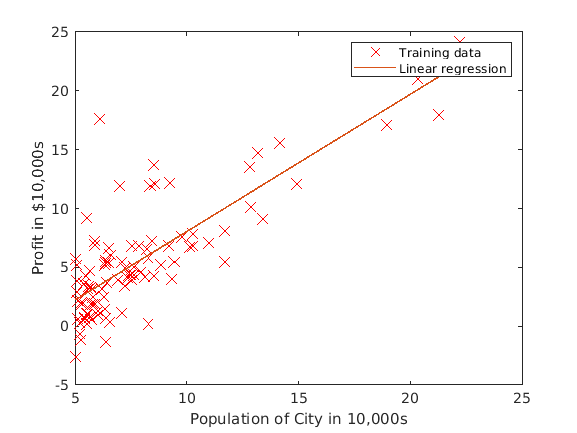


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure


% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

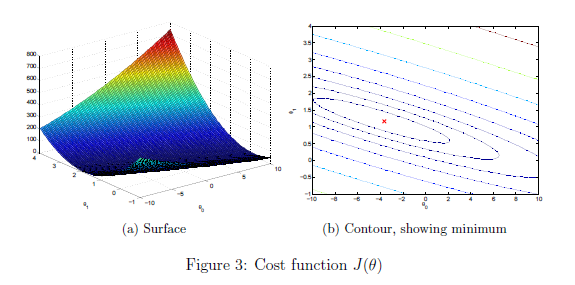

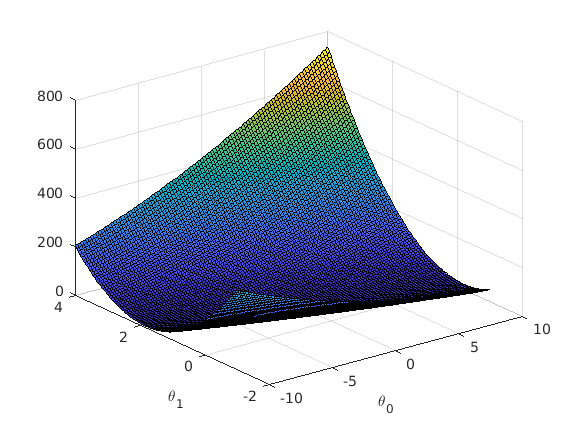

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

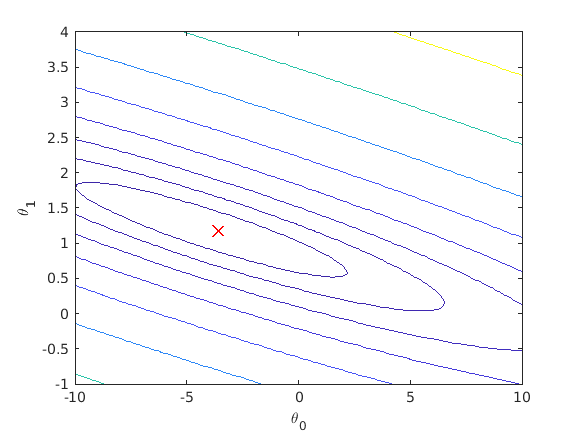


% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

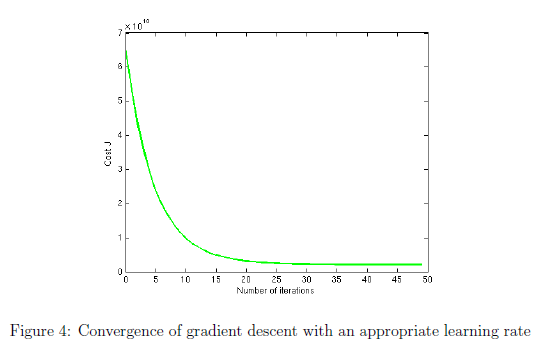

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

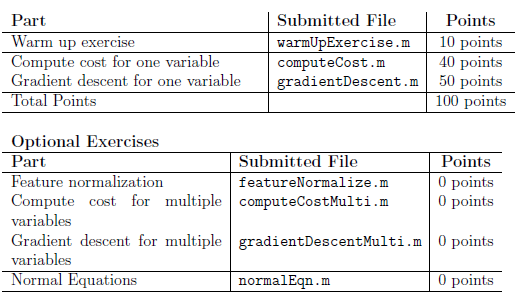

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.